# ECSE 343: Numerical Methods for Engineers- Assignement 2

Due Date: 9th March 2021

Student Name: Hongtao Xu 

Student ID:    

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with the **PDF** copy of this file.

## Question 1: 

a) Prove that $\kappa \;\left(A^{T\;} A\right)={\kappa \left(A\right)}^2 \;$.

Ax = 0 

$A^{T\;}$Ax = 0, so X belongs to N($A^{T\;}$A)

 hence, N(A) belongs to N($A^{T\;}$A); also x belongs to N($A^{T\;}$A)

 so $A^{T\;}$Ax = 0 

 $x^{T\;A^{T\;} }$Ax = 0  -> ${\left(\textrm{Ax}\right)}^{T\;}$Ax =0

 Ax = 0, so x belongs to N(A)

 because N($A^{T\;}$A) belongs to N(A)

 so N($A^{T\;}$A) = N(A) and thier dimensions are the sane 

 finally  $\kappa \;\left(A^{T\;} A\right)={\kappa \left(A\right)}^2 \;$

b) Given two orthonormal matrices $U$and $Q$, show that product of these matrices, $\textrm{UQ}$, is also orthonormal.

U$U^{T\;}$= $U^{T\;}$U = I 

Q$Q^{T\;}$= $Q^{T\;}$Q = I 

so ${\left(\textrm{UQ}\right)}^{T\;}$(UQ) = $Q^{T\;}$$U^{T\;}$UQ = I 

in this way, it is orthonormal 

c) If A is an invertible matrix and Q is an orthonormal matrix, show that $\kappa \left(\textrm{QA}\right)=\kappa \left(A\right)\ldotp$

Hint: $\kappa \;\left(A\right)=\frac{\sigma_1 }{\sigma_{n\;} }\;$ (the ratio of the largest and smallest eigen values).

A is a intvertiable matrix and ! is an orthonormal matrix, in this way, det(A) n != 0 also det(A) is the product of eigenvalues 

we know that eigenvalues of A are non-zero 

$QQ^{T\;}$= $Q^{T\;}$Q = I 

det ($QQ^{T\;}$)=det($\left.Q^{T\;} \right)=1\;$

(detQ)^2 = 1 so that det(Q) = +1/-1

det(QA) = det(Q)(detA) = (+/- 1)*(product of eigenvalues of A)

K(QA) = $\frac{\sigma_{1^{\prime } } }{\sigma_{n^{\prime } \;} }$=$\frac{\sigma_1 }{\sigma_{n\;} }$=K(A)

## Question 2: 

(a) **Cholesky factorization **is a popular matrix factorization algorithm analogous to LU decompostion for positive definite matrices. In this case a matrix $\mathit{\mathbf{M}}\in \Re^{N\times N}$ is factored as


$$\mathit{\mathbf{M}}=\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^T$$
                 

Where $\mathit{\mathbf{L}}\in \Re^{N\times N}$ is a lower triangular matrix with real and positive diagonal enteries. 

Note that there are a number of tests/definitions for positive definite matrices. A matrix, $\mathit{\mathbf{M}}$is positive definite if and only if it satisfies the following two conditions,

     1. The matrix $\mathit{\mathbf{M}}$must be sysmterical, i.e. $\mathit{\mathbf{M}}={\mathit{\mathbf{M}}}^{\mathit{\mathbf{T}}}$

     2. ${\mathit{\mathbf{x}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{M}}\;\mathit{\mathbf{x}}>0$ for  all  $\mathit{\mathbf{x}}\in \Re^{N\times 1}$ ; $\left\|\mathit{\mathbf{x}}\right\|\not= 0$.

An alternative definition/test is that a matrix $\mathit{\mathbf{M}}\in \Re^{N\times N}$is positive definite if and only if it can be written as


$$\mathit{\mathbf{M}}=\mathit{\mathbf{A}}{\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}}$$
                 

It can be shown (similarly to how we derived the Doolittle algorithm) that the entries of matrix $\mathit{\mathbf{L}}$ are given by the following expression 


$$\textbf{L}_{i,j} = 
\begin{cases}
    \sqrt{ \textbf{M}_{j,j} - \sum_{k=1}^{j-1} \textbf{L}_{j,k}^2 }    ,& \text{if  } i =j\\
    \frac{1}{\textbf{L}_{j,j}} \left(\textbf{M}_{i,j} - \sum_{k=1}^{j-1} \textbf{L}_{i,k} \textbf{L}_{j,k} \right),              & \text{if  } i>j\\
0, & \text{otherwise}
\end{cases}$$


The cost of Cholesky factorization algorithm is rougly half than the LU decompostion. Your task is to implement the Cholesky decomposition alogorithm in the cell below. Note that for Cholesky decomposition pivoting is not required

Use the cell below to test the Cholesky decompostion code. To test this, compute the Frobenius norm of  $\left.{\left(\mathit{\mathbf{L}}\right.}^{\;} {\mathit{\mathbf{L}}}^T -M\right)\ldotp$

A = randi(100,5);
M =A'*A;
L = CholeskyDecomposition(M);

Error =  norm(L*L'-M);


 b) Cholesky decompostion can be used to solve the normal eqautions,  ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$ as the matrix $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ is positive definite. Using Cholesky facotrization scheme $\left({\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\right)$ can be factored as ${\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{A}}\;={\mathit{\mathbf{L}}}^{\;} {\mathit{\mathbf{L}}}^T$. Using this the normal equations become,


$$\mathit{\mathbf{L}}\;{\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$$


The above equation consists of the triangular systems, the solution **x **can be obtained by  first solving $\mathit{\mathbf{L}}\;\mathit{\mathbf{y}}={\mathit{\mathbf{A}}}^{\mathit{\mathbf{T}}\;} \mathit{\mathbf{b}}$ using the forward substitution, then by solving the  ${\mathit{\mathbf{L}}}^{\mathit{\mathbf{T}}} \;\mathit{\mathbf{x}}=\mathit{\mathbf{y}}$ using backward subsitution. Implement the Cholesky solver for least squares in the function below. 

You can use your Forward/Backward Substitution from Assignment 1 for bonus marks. Include your code for forward/backward substitution in the Appendix.

% in the end 

d) To test the Cholesky Least Squares solver we numerical algorithm we will use a square matrix. Run the cell below to compare  the solution.

A = [12    10     6     5    46;
     79    14    24    17    55;
     39    95    36    65    30;
     25    96    83    74    75;
     41    58     2    65    19];
 
B = [45; 35; 58; 12; 10];

x = LeastSquareSolver_Cholesky(A,B);

x =     0.4453
    0.3109
    1.2031
    0.6448
    0.2666


% verify your solution

R = chol(A'*A,'lower'); 
Error2 = norm(R*R'-M);
X = R'\(R\(A'*B));


**Question 3: **

Polynomial fitting is one of the many applications of Least-Squares Approximation. Given the experimental data, shown in Table below, 

    
$$\matrix{   Input,, x  | &  x_0  &x_1  & x_2& x_3 &\dots  & x_{m-1}& x_m \cr
Output, y| &  y_0 & y_1& y_2 & y_3 & \dots & y_{m-1}&y_m
}$$


we can fit a $n^{\textrm{th}}$degree polynomial, $p\left(x\right)=a_0 +a_1 x+a_{2\;} x^{2\;} +a_3 x^3 +\cdots +a_{n\;} x^n$. To find the coefficicients,  $\mathit{\mathbf{a}}=\left\lbrack a_{0\;} ,\;\;a_1 ,\;\;a_2 ,\cdots a_n \right\rbrack$, we can solve the linear system shown below. 


$$\underset{\mathit{\mathbf{M}}}{\underbrace{\left\lbrack \begin{array}{ccccc}
1 & x_0  & x_0^2  & \cdots  & x_0^n \\
1 & x_1  & x_1^2  & \cdots  & x_1^n \\
1 & x_{2\;}  & x_{2\;}^2  & \cdots \; & x_{2\;}^n \\
\vdots \; & \vdots  & \vdots  & \ddots \; & \vdots \;\\
1 & x_{m-1}  & x_{m-1}^2  & \cdots  & x_{m-1}^n \\
1 & x_m  & x_m^2  & \cdots \; & x_m^n 
\end{array}\right\rbrack } }$$

$$\underset{\mathit{\mathbf{A}}}{\underbrace{\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
a_2 \\
\vdots \\
a_n 
\end{array}\right\rbrack } } =\underset{\mathit{\mathbf{y}}}{\underbrace{\left\lbrack \begin{array}{c}
y_0 \\
y_1 \\
y_2 \\
\vdots \\
y_{m-1} \\
y_m 
\end{array}\right\rbrack } }$$


Where $\mathit{\mathbf{M}}$ is a Vandermonde matrix (known to be ill-conditioned). The system $\mathit{\mathbf{M}}\;\mathit{\mathbf{a}}=\mathit{\mathbf{y}}$ can then be solved to compute the coefficients in vector $\mathit{\mathbf{a}}\ldotp$

a) Your first task is to write a function that takes the input data vector $\mathit{\mathbf{x}}$ and degree of the polynomial, then returns the Vadermonde matrix $\mathit{\mathbf{M}}\ldotp$ Complete the function in the cell below.

b) The linear system can be solved using different approaches. In the code below, use the Cholesky decompositon and QR decomposition function to find the polynomial coefficients for the 1st degree polynomial. Explain the results obtained in figure 1.

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

% set the degree
deg = 1  

deg = 1

% Define powers 
powers = 0:deg;
x = x_given;
y = y_given;

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   % Find the polynomial coefficients using L, and Q & R matrices obtained obove.
   
   % Name the Coefficeints obtained Cholesky  Ac
        % Use the MATLAB's Forward Slash Algorithm to obtain Ac 
        % by solving the normal equations (like we did in Tutorial)
            % Normal Eqautions: (Mp'*Mp)*Ac = Mp'*y
            % write your code here
            Ac = (Mp'*Mp)\(Mp' *y);
   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
            Ar = (Q*R)\y;
   
   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   x_new = 0:0.01:7;
   x_new = x_new';
   
   fr = zeros(length(x_new),1);
   fc = zeros(length(x_new),1);
   
   
   
   for I = 1:length(powers)
       fr = fr + Ar(I)*x_new.^powers(I);
       fc = fc + Ac(I)*x_new.^powers(I);
   end
   %plots
   figure(1)
   hold on
   plot(x,y,'ro')
   plot(x_new,fc,'m--','Linewidth',2)
   plot(x_new,fr,'r-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Cholesky','MATLAB QR')
   grid on



c) Now use the cell below to use the Cholesky decompositon and QR decomposition function to find the polynomial coefficients for the 14th degree polynomial. **Explain the results obtained in figure 2.**

% use the code from Part b as a starting point

% set the degree
deg = 14;  
% Define powers 
powers = 0:deg;
x = x_given;
y = y_given;

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [Q,R] = qr(Mp);
   
   % Find the polynomial coefficients using L, and Q & R matrices obtained obove.
   
   % Name the Coefficeints obtained Cholesky  Ac
        % Use the MATLAB's Forward Slash Algorithm to obtain Ac 
        % by solving the normal equations (like we did in Tutorial)
            % Normal Eqautions: (Mp'*Mp)*Ac = Mp'*y
            % write your code here
            Ac = (Mp'*Mp)\(Mp' *y);

   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
            Ar = (Q*R)\y;

   
   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   x_new = 0:0.01:7;
   x_new = x_new';
   
   fr = zeros(length(x_new),1);
   fc = zeros(length(x_new),1);
   
  
   for I = 1:length(powers)
       fr = fr + Ar(I)*x_new.^powers(I);   
       fc = fc + Ac(I)*x_new.^powers(I);
   end
   %plots
   figure(1)
   hold on
   plot(x,y,'ro')
   plot(x_new,fc,'m--','Linewidth',2)
   plot(x_new,fr,'r-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Cholesky','MATLAB QR')
   grid on


d) In this part we will use limited amount of data, we will use only** 15 data points**. Use Cholesky decompositon and QR decomposition function to find the polynomial coefficients for the 14th degree polynomial. **Comment on the results obtained in figure 3, which algorithm performs better and why?**

% Load the Input Data from the provided .mat file 

load('Polynomial_Fitting_Data.mat');

% set the degree
deg =  14;
% Define powers 
powers = 0:deg;

x = x_given(1:20:end);
y = y_given(1:20:end);

% get Polynomial Matrix 
Mp14 = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [Q,R] = qr(Mp14);
   
   % Find the polynomial coefficients using L, and Q & R matrices obtained obove.
   
   % Name the Coefficeints obtained Cholesky  Ac
        % Use the MATLAB's Forward Slash Algorithm to obtain Ac 
        % by solving the normal equations (like we did in Tutorial)
            % Normal Eqautions: (Mp'*Mp)*Ac = Mp'*y
            % write your code here
            Ac14 = (Mp14'*Mp14)\(Mp14' *y);

   
   % Name the Coefficeints obtained QR as Ar
            
            % write your code here
             Ar14 = (Q*R)\y;

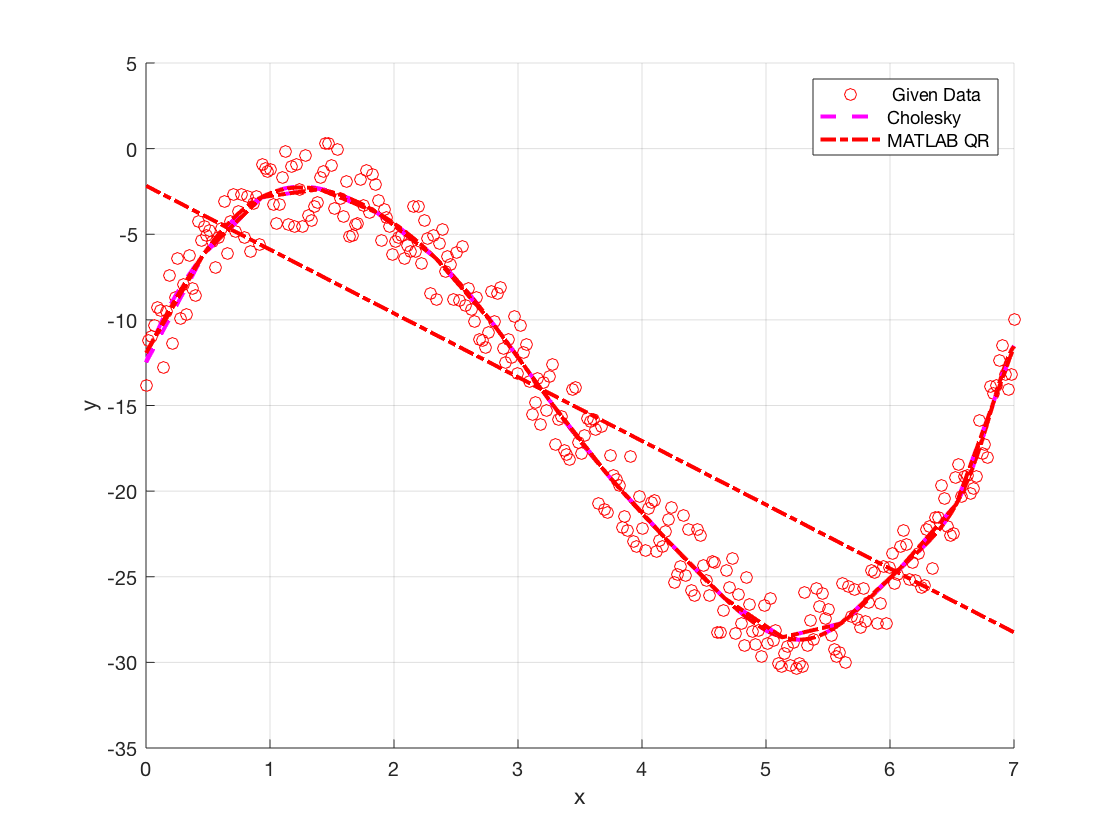

   
   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   x_new = 0:7/15:7;
   x_new = x_new';
   
   fr = zeros(length(x_new),1);
   fc = zeros(length(x_new),1);
   
  
   for I = 1:length(powers)
       fr = fr + Ar(I)*x_new.^powers(I);   
       fc = fc + Ac(I)*x_new.^powers(I);
   end
   %plots
   figure(1)
   hold on
   plot(x,y,'ro')
   plot(x_new,fc,'m--','Linewidth',2)
   plot(x_new,fr,'r-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','Cholesky','MATLAB QR')
   grid on

## Question 4:

 In this question we will develop the different algorithms to implment QR factorization.

a)  Use the cell below to implement a function that computes Gram-Schmidt based QR decompositon of a input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = randi(100,6); % A is a 6x6 matrix of random numbers
   [Q,R] = gschmidt(A);
   
   norm(A-Q*R,'fro');

b)  Use the cell below to implement a function that uses the Modiefied Gram-Schmidt approach to compute the  QR decompositon of  the input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

    A = randi(100,6); % A is a 6x6 matrix of random numbers
   [Q,R] = gschmidt(A);
   
   norm(A-Q*R,'fro');
   

c)  Use the cell below to implement a function that uses the Householder approach to compute the  QR decompositon of  the input matrix A.

  Use the cell blow to test the your method by comparing the computing the ${\left\|A-Q\;R\right\|}_F$. Use the Frobenius  norm in the MATLAB, comment on your result.

   A = randi(100,6); % A is a 6x6 matrix of random numbers
   [Q,R] = householder(A);
   
   norm(A-Q*R,'fro');
   

d) We know that $\mathit{\mathbf{Q}}$ matrix obtained using QR decompostion should have orthonormal columns i.e. ${\mathit{\mathbf{Q}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}=\mathit{\mathbf{I}}$. However, due to numerical errors, In this section we will test the functions written above to compare the error between the above implemeneted approaches. In oder to do this we will use a $n\times n$ HIlbert Matrix, the entries of Hibert Matrix are given by 


$$h_{i,j} =\frac{1}{\;i+j-1}$$


 In the cell below we compute the QR decomposition of Hilbert matrices of size ranging from 2 to 16, then we compute the norm of error $\left({\mathit{\mathbf{Q}}}^{\mathit{\mathbf{T}}} \mathit{\mathbf{Q}}-\mathit{\mathbf{I}}\right)$ to assess the performance of the lorithms written in part (a), ( b), and (c). Comment on the results obtained.

for n=2:16
a= hilb(n); % n is the size of the matrix
[q_gs,r1] = gschmidt(a); %using algorithm classical Gram--Schmidt
[q_mgs,r2] = mgschmidt(a); %using algorithm modified Gram-Schmidt
[q_hh,r3] = householder(a); % using house holder

err_gs(n-1) = norm(q_gs'*q_gs - eye(n),'fro');
err_mgs(n-1) = norm(q_mgs'*q_mgs - eye(n),'fro');
err_hh(n-1) = norm(q_hh'*q_hh - eye(n),'fro');
end 

v =     1.0000   -0.0333
    0.5000    0.0667


v =     1.0000   -0.0510    0.3333
    0.5000    0.0578    0.2500
    0.3333    0.0663    0.2000


v =     1.0000   -0.0510   -0.0524
    0.5000    0.0578    0.0571
    0.3333    0.0663    0.0714


v =     1.0000   -0.0510    0.0005
    0.5000    0.0578   -0.0027
    0.3333    0.0663    0.0027


v =     1.0000   -0.0620    0.3333    0.2500
    0.5000    0.0524    0.2500    0.2000
    0.3333    0.0627    0.2000    0.1667
    0.2500    0.0595    0.1667    0.1429


v =     1.0000   -0.0620   -0.0647    0.2500
    0.5000    0.0524    0.0510    0.2000
    0.3333    0.0627    0.0673    0.1667
    0.2500    0.0595    0.0672    0.1429


v =     1.0000   -0.0620   -0.0647   -0.0600
    0.5000    0.0524    0.0510    0.0450
    0.3333    0.0627    0.0673    0.0633
    0.2500    0.0595    0.0672    0.0654


v =     1.0000   -0.0620    0.0010   -0.0600
    0.5000    0.0524   -0.0045    0.0450
    0.3333    0.0627    0.0009    0.0633
    0.2500    0.0595    0.0041    0.0654


v =     1.0000   -0.0620    0.0010    0.0015
    0.5000    0.0524   -0.0045   -0.0069
    0.3333    0.0627    0.0009    0.0012
    0.2500    0.0595    0.0041    0.0064


v =     1.0000   -0.0620    0.0010   -0.0000
    0.5000    0.0524   -0.0045    0.0001
    0.3333    0.0627    0.0009   -0.0001
    0.2500    0.0595    0.0041    0.0001


v =     1.0000   -0.0694    0.3333    0.2500    0.2000
    0.5000    0.0486    0.2500    0.2000    0.1667
    0.3333    0.0602    0.2000    0.1667    0.1429
    0.2500    0.0577    0.1667    0.1429    0.1250
    0.2000    0.0528    0.1429    0.1250    0.1111


v =     1.0000   -0.0694   -0.0734    0.2500    0.2000
    0.5000    0.0486    0.0467    0.2000    0.1667
    0.3333    0.0602    0.0644    0.1667    0.1429
    0.2500    0.0577    0.0650    0.1429    0.1250
    0.2000    0.0528    0.0615    0.1250    0.1111


v =     1.0000   -0.0694   -0.0734   -0.0686    0.2000
    0.5000    0.0486    0.0467    0.0407    0.1667
    0.3333    0.0602    0.0644    0.0605    0.1429
    0.2500    0.0577    0.0650    0.0632    0.1250
    0.2000    0.0528    0.0615    0.0613    0.1111


v =     1.0000   -0.0694   -0.0734   -0.0686   -0.0627
    0.5000    0.0486    0.0467    0.0407    0.0353
    0.3333    0.0602    0.0644    0.0605    0.0553
    0.2500    0.0577    0.0650    0.0632    0.0593
    0.2000    0.0528    0.0615    0.0613    0.0586


v =     1.0000   -0.0694    0.0014   -0.0686   -0.0627
    0.5000    0.0486   -0.0058    0.0407    0.0353
    0.3333    0.0602   -0.0005    0.0605    0.0553
    0.2500    0.0577    0.0028    0.0632    0.0593
    0.2000    0.0528    0.0046    0.0613    0.0586


v =     1.0000   -0.0694    0.0014    0.0022   -0.0627
    0.5000    0.0486   -0.0058   -0.0089    0.0353
    0.3333    0.0602   -0.0005   -0.0010    0.0553
    0.2500    0.0577    0.0028    0.0044    0.0593
    0.2000    0.0528    0.0046    0.0074    0.0586


v =     1.0000   -0.0694    0.0014    0.0022    0.0026
    0.5000    0.0486   -0.0058   -0.0089   -0.0104
    0.3333    0.0602   -0.0005   -0.0010   -0.0013
    0.2500    0.0577    0.0028    0.0044    0.0051
    0.2000    0.0528    0.0046    0.0074    0.0089


v =     1.0000   -0.0694    0.0014   -0.0000    0.0026
    0.5000    0.0486   -0.0058    0.0001   -0.0104
    0.3333    0.0602   -0.0005   -0.0002   -0.0013
    0.2500    0.0577    0.0028   -0.0001    0.0051
    0.2000    0.0528    0.0046    0.0002    0.0089


v =     1.0000   -0.0694    0.0014   -0.0000   -0.0000
    0.5000    0.0486   -0.0058    0.0001    0.0003
    0.3333    0.0602   -0.0005   -0.0002   -0.0005
    0.2500    0.0577    0.0028   -0.0001   -0.0001
    0.2000    0.0528    0.0046    0.0002    0.0004


v =     1.0000   -0.0694    0.0014   -0.0000    0.0000
    0.5000    0.0486   -0.0058    0.0001   -0.0000
    0.3333    0.0602   -0.0005   -0.0002    0.0000
    0.2500    0.0577    0.0028   -0.0001   -0.0000
    0.2000    0.0528    0.0046    0.0002    0.0000


v =     1.0000   -0.0747    0.3333    0.2500    0.2000    0.1667
    0.5000    0.0460    0.2500    0.2000    0.1667    0.1429
    0.3333    0.0584    0.2000    0.1667    0.1429    0.1250
    0.2500    0.0563    0.1667    0.1429    0.1250    0.1111
    0.2000    0.0517    0.1429    0.1250    0.1111    0.1000
    0.1667    0.0471    0.1250    0.1111    0.1000    0.0909


v =     1.0000   -0.0747   -0.0798    0.2500    0.2000    0.1667
    0.5000    0.0460    0.0435    0.2000    0.1667    0.1429
    0.3333    0.0584    0.0623    0.1667    0.1429    0.1250
    0.2500    0.0563    0.0634    0.1429    0.1250    0.1111
    0.2000    0.0517    0.0602    0.1250    0.1111    0.1000
    0.1667    0.0471    0.0562    0.1111    0.1000    0.0909


v =     1.0000   -0.0747   -0.0798   -0.0751    0.2000    0.1667
    0.5000    0.0460    0.0435    0.0375    0.1667    0.1429
    0.3333    0.0584    0.0623    0.0583    0.1429    0.1250
    0.2500    0.0563    0.0634    0.0616    0.1250    0.1111
    0.2000    0.0517    0.0602    0.0600    0.1111    0.1000
    0.1667    0.0471    0.0562    0.0569    0.1000    0.0909


v =     1.0000   -0.0747   -0.0798   -0.0751   -0.0689    0.1667
    0.5000    0.0460    0.0435    0.0375    0.0322    0.1429
    0.3333    0.0584    0.0623    0.0583    0.0532    0.1250
    0.2500    0.0563    0.0634    0.0616    0.0578    0.1111
    0.2000    0.0517    0.0602    0.0600    0.0573    0.1000
    0.1667    0.0471    0.0562    0.0569    0.0552    0.0909


v =     1.0000   -0.0747   -0.0798   -0.0751   -0.0689   -0.0631
    0.5000    0.0460    0.0435    0.0375    0.0322    0.0280
    0.3333    0.0584    0.0623    0.0583    0.0532    0.0484
    0.2500    0.0563    0.0634    0.0616    0.0578    0.0537
    0.2000    0.0517    0.0602    0.0600    0.0573    0.0540
    0.1667    0.0471    0.0562    0.0569    0.0552    0.0526


v =     1.0000   -0.0747    0.0018   -0.0751   -0.0689   -0.0631
    0.5000    0.0460   -0.0067    0.0375    0.0322    0.0280
    0.3333    0.0584   -0.0015    0.0583    0.0532    0.0484
    0.2500    0.0563    0.0019    0.0616    0.0578    0.0537
    0.2000    0.0517    0.0038    0.0600    0.0573    0.0540
    0.1667    0.0471    0.0048    0.0569    0.0552    0.0526


v =     1.0000   -0.0747    0.0018    0.0029   -0.0689   -0.0631
    0.5000    0.0460   -0.0067   -0.0105    0.0322    0.0280
    0.3333    0.0584   -0.0015   -0.0026    0.0532    0.0484
    0.2500    0.0563    0.0019    0.0029    0.0578    0.0537
    0.2000    0.0517    0.0038    0.0061    0.0573    0.0540
    0.1667    0.0471    0.0048    0.0079    0.0552    0.0526


v =     1.0000   -0.0747    0.0018    0.0029    0.0034   -0.0631
    0.5000    0.0460   -0.0067   -0.0105   -0.0123    0.0280
    0.3333    0.0584   -0.0015   -0.0026   -0.0033    0.0484
    0.2500    0.0563    0.0019    0.0029    0.0033    0.0537
    0.2000    0.0517    0.0038    0.0061    0.0073    0.0540
    0.1667    0.0471    0.0048    0.0079    0.0096    0.0526


v =     1.0000   -0.0747    0.0018    0.0029    0.0034    0.0036
    0.5000    0.0460   -0.0067   -0.0105   -0.0123   -0.0131
    0.3333    0.0584   -0.0015   -0.0026   -0.0033   -0.0038
    0.2500    0.0563    0.0019    0.0029    0.0033    0.0034
    0.2000    0.0517    0.0038    0.0061    0.0073    0.0079
    0.1667    0.0471    0.0048    0.0079    0.0096    0.0106


v =     1.0000   -0.0747    0.0018   -0.0000    0.0034    0.0036
    0.5000    0.0460   -0.0067    0.0002   -0.0123   -0.0131
    0.3333    0.0584   -0.0015   -0.0003   -0.0033   -0.0038
    0.2500    0.0563    0.0019   -0.0002    0.0033    0.0034
    0.2000    0.0517    0.0038    0.0000    0.0073    0.0079
    0.1667    0.0471    0.0048    0.0003    0.0096    0.0106


v =     1.0000   -0.0747    0.0018   -0.0000   -0.0000    0.0036
    0.5000    0.0460   -0.0067    0.0002    0.0004   -0.0131
    0.3333    0.0584   -0.0015   -0.0003   -0.0006   -0.0038
    0.2500    0.0563    0.0019   -0.0002   -0.0004    0.0034
    0.2000    0.0517    0.0038    0.0000    0.0001    0.0079
    0.1667    0.0471    0.0048    0.0003    0.0006    0.0106


v =     1.0000   -0.0747    0.0018   -0.0000   -0.0000   -0.0001
    0.5000    0.0460   -0.0067    0.0002    0.0004    0.0006
    0.3333    0.0584   -0.0015   -0.0003   -0.0006   -0.0008
    0.2500    0.0563    0.0019   -0.0002   -0.0004   -0.0006
    0.2000    0.0517    0.0038    0.0000    0.0001    0.0001
    0.1667    0.0471    0.0048    0.0003    0.0006    0.0008


v =     1.0000   -0.0747    0.0018   -0.0000    0.0000   -0.0001
    0.5000    0.0460   -0.0067    0.0002   -0.0000    0.0006
    0.3333    0.0584   -0.0015   -0.0003    0.0000   -0.0008
    0.2500    0.0563    0.0019   -0.0002   -0.0000   -0.0006
    0.2000    0.0517    0.0038    0.0000   -0.0000    0.0001
    0.1667    0.0471    0.0048    0.0003    0.0000    0.0008


v =     1.0000   -0.0747    0.0018   -0.0000    0.0000    0.0000
    0.5000    0.0460   -0.0067    0.0002   -0.0000   -0.0000
    0.3333    0.0584   -0.0015   -0.0003    0.0000    0.0000
    0.2500    0.0563    0.0019   -0.0002   -0.0000   -0.0000
    0.2000    0.0517    0.0038    0.0000   -0.0000   -0.0000
    0.1667    0.0471    0.0048    0.0003    0.0000    0.0000


v =     1.0000   -0.0747    0.0018   -0.0000    0.0000   -0.0000
    0.5000    0.0460   -0.0067    0.0002   -0.0000    0.0000
    0.3333    0.0584   -0.0015   -0.0003    0.0000   -0.0000
    0.2500    0.0563    0.0019   -0.0002   -0.0000    0.0000
    0.2000    0.0517    0.0038    0.0000   -0.0000   -0.0000
    0.1667    0.0471    0.0048    0.0003    0.0000    0.0000


v =     1.0000   -0.0788    0.3333    0.2500    0.2000    0.1667    0.1429
    0.5000    0.0439    0.2500    0.2000    0.1667    0.1429    0.1250
    0.3333    0.0571    0.2000    0.1667    0.1429    0.1250    0.1111
    0.2500    0.0553    0.1667    0.1429    0.1250    0.1111    0.1000
    0.2000    0.0509    0.1429    0.1250    0.1111    0.1000    0.0909
    0.1667    0.0464    0.1250    0.1111    0.1000    0.0909    0.0833
    0.1429    0.0423    0.1111    0.1000    0.0909    0.0833    0.0769


v =     1.0000   -0.0788   -0.0847    0.2500    0.2000    0.1667    0.1429
    0.5000    0.0439    0.0410    0.2000    0.1667    0.1429    0.1250
    0.3333    0.0571    0.0607    0.1667    0.1429    0.1250    0.1111
    0.2500    0.0553    0.0622    0.1429    0.1250    0.1111    0.1000
    0.2000    0.0509    0.0593    0.1250    0.1111    0.1000    0.0909
    0.1667    0.0464    0.0553    0.1111    0.1000    0.0909    0.0833
    0.1429    0.0423    0.0514    0.1000    0.0909    0.0833    0.0769


v =     1.0000   -0.0788   -0.0847   -0.0801    0.2000    0.1667    0.1429
    0.5000    0.0439    0.0410    0.0349    0.1667    0.1429    0.1250
    0.3333    0.0571    0.0607    0.0566    0.1429    0.1250    0.1111
    0.2500    0.0553    0.0622    0.0603    0.1250    0.1111    0.1000
    0.2000    0.0509    0.0593    0.0590    0.1111    0.1000    0.0909
    0.1667    0.0464    0.0553    0.0561    0.1000    0.0909    0.0833
    0.1429    0.0423    0.0514    0.0528    0.0909    0.0833    0.0769


v =     1.0000   -0.0788   -0.0847   -0.0801   -0.0739    0.1667    0.1429
    0.5000    0.0439    0.0410    0.0349    0.0297    0.1429    0.1250
    0.3333    0.0571    0.0607    0.0566    0.0516    0.1250    0.1111
    0.2500    0.0553    0.0622    0.0603    0.0565    0.1111    0.1000
    0.2000    0.0509    0.0593    0.0590    0.0563    0.1000    0.0909
    0.1667    0.0464    0.0553    0.0561    0.0544    0.0909    0.0833
    0.1429    0.0423    0.0514    0.0528    0.0518    0.0833    0.0769


v =     1.0000   -0.0788   -0.0847   -0.0801   -0.0739   -0.0679    0.1429
    0.5000    0.0439    0.0410    0.0349    0.0297    0.0256    0.1250
    0.3333    0.0571    0.0607    0.0566    0.0516    0.0468    0.1111
    0.2500    0.0553    0.0622    0.0603    0.0565    0.0525    0.1000
    0.2000    0.0509    0.0593    0.0590    0.0563    0.0531    0.0909
    0.1667    0.0464    0.0553    0.0561    0.0544    0.0518    0.0833
    0.1429    0.0423    0.0514    0.0528    0.0518    0.0498    0.0769


v =     1.0000   -0.0788   -0.0847   -0.0801   -0.0739   -0.0679   -0.0625
    0.5000    0.0439    0.0410    0.0349    0.0297    0.0256    0.0223
    0.3333    0.0571    0.0607    0.0566    0.0516    0.0468    0.0427
    0.2500    0.0553    0.0622    0.0603    0.0565    0.0525    0.0487
    0.2000    0.0509    0.0593    0.0590    0.0563    0.0531    0.0498
    0.1667    0.0464    0.0553    0.0561    0.0544    0.0518    0.0491
    0.1429    0.0423    0.0514    0.0528    0.0518    0.0498    0.0476


v =     1.0000   -0.0788    0.0021   -0.0801   -0.0739   -0.0679   -0.0625
    0.5000    0.0439   -0.0074    0.0349    0.0297    0.0256    0.0223
    0.3333    0.0571   -0.0022    0.0566    0.0516    0.0468    0.0427
    0.2500    0.0553    0.0012    0.0603    0.0565    0.0525    0.0487
    0.2000    0.0509    0.0031    0.0590    0.0563    0.0531    0.0498
    0.1667    0.0464    0.0042    0.0561    0.0544    0.0518    0.0491
    0.1429    0.0423    0.0048    0.0528    0.0518    0.0498    0.0476


v =     1.0000   -0.0788    0.0021    0.0034   -0.0739   -0.0679   -0.0625
    0.5000    0.0439   -0.0074   -0.0117    0.0297    0.0256    0.0223
    0.3333    0.0571   -0.0022   -0.0039    0.0516    0.0468    0.0427
    0.2500    0.0553    0.0012    0.0017    0.0565    0.0525    0.0487
    0.2000    0.0509    0.0031    0.0050    0.0563    0.0531    0.0498
    0.1667    0.0464    0.0042    0.0069    0.0544    0.0518    0.0491
    0.1429    0.0423    0.0048    0.0080    0.0518    0.0498    0.0476


v =     1.0000   -0.0788    0.0021    0.0034    0.0041   -0.0679   -0.0625
    0.5000    0.0439   -0.0074   -0.0117   -0.0138    0.0256    0.0223
    0.3333    0.0571   -0.0022   -0.0039   -0.0049    0.0468    0.0427
    0.2500    0.0553    0.0012    0.0017    0.0018    0.0525    0.0487
    0.2000    0.0509    0.0031    0.0050    0.0059    0.0531    0.0498
    0.1667    0.0464    0.0042    0.0069    0.0084    0.0518    0.0491
    0.1429    0.0423    0.0048    0.0080    0.0099    0.0498    0.0476


v =     1.0000   -0.0788    0.0021    0.0034    0.0041    0.0044   -0.0625
    0.5000    0.0439   -0.0074   -0.0117   -0.0138   -0.0147    0.0223
    0.3333    0.0571   -0.0022   -0.0039   -0.0049   -0.0056    0.0427
    0.2500    0.0553    0.0012    0.0017    0.0018    0.0017    0.0487
    0.2000    0.0509    0.0031    0.0050    0.0059    0.0064    0.0498
    0.1667    0.0464    0.0042    0.0069    0.0084    0.0092    0.0491
    0.1429    0.0423    0.0048    0.0080    0.0099    0.0110    0.0476


v =     1.0000   -0.0788    0.0021    0.0034    0.0041    0.0044    0.0045
    0.5000    0.0439   -0.0074   -0.0117   -0.0138   -0.0147   -0.0151
    0.3333    0.0571   -0.0022   -0.0039   -0.0049   -0.0056   -0.0059
    0.2500    0.0553    0.0012    0.0017    0.0018    0.0017    0.0016
    0.2000    0.0509    0.0031    0.0050    0.0059    0.0064    0.0065
    0.1667    0.0464    0.0042    0.0069    0.0084    0.0092    0.0096
    0.1429    0.0423    0.0048    0.0080    0.0099    0.0110    0.0116


v =     1.0000   -0.0788    0.0021   -0.0000    0.0041    0.0044    0.0045
    0.5000    0.0439   -0.0074    0.0003   -0.0138   -0.0147   -0.0151
    0.3333    0.0571   -0.0022   -0.0003   -0.0049   -0.0056   -0.0059
    0.2500    0.0553    0.0012   -0.0003    0.0018    0.0017    0.0016
    0.2000    0.0509    0.0031   -0.0001    0.0059    0.0064    0.0065
    0.1667    0.0464    0.0042    0.0001    0.0084    0.0092    0.0096
    0.1429    0.0423    0.0048    0.0003    0.0099    0.0110    0.0116


v =     1.0000   -0.0788    0.0021   -0.0000   -0.0001    0.0044    0.0045
    0.5000    0.0439   -0.0074    0.0003    0.0006   -0.0147   -0.0151
    0.3333    0.0571   -0.0022   -0.0003   -0.0006   -0.0056   -0.0059
    0.2500    0.0553    0.0012   -0.0003   -0.0006    0.0017    0.0016
    0.2000    0.0509    0.0031   -0.0001   -0.0002    0.0064    0.0065
    0.1667    0.0464    0.0042    0.0001    0.0003    0.0092    0.0096
    0.1429    0.0423    0.0048    0.0003    0.0007    0.0110    0.0116


v =     1.0000   -0.0788    0.0021   -0.0000   -0.0001   -0.0001    0.0045
    0.5000    0.0439   -0.0074    0.0003    0.0006    0.0009   -0.0151
    0.3333    0.0571   -0.0022   -0.0003   -0.0006   -0.0009   -0.0059
    0.2500    0.0553    0.0012   -0.0003   -0.0006   -0.0008    0.0016
    0.2000    0.0509    0.0031   -0.0001   -0.0002   -0.0002    0.0065
    0.1667    0.0464    0.0042    0.0001    0.0003    0.0004    0.0096
    0.1429    0.0423    0.0048    0.0003    0.0007    0.0010    0.0116


v =     1.0000   -0.0788    0.0021   -0.0000   -0.0001   -0.0001   -0.0001
    0.5000    0.0439   -0.0074    0.0003    0.0006    0.0009    0.0011
    0.3333    0.0571   -0.0022   -0.0003   -0.0006   -0.0009   -0.0011
    0.2500    0.0553    0.0012   -0.0003   -0.0006   -0.0008   -0.0010
    0.2000    0.0509    0.0031   -0.0001   -0.0002   -0.0002   -0.0003
    0.1667    0.0464    0.0042    0.0001    0.0003    0.0004    0.0005
    0.1429    0.0423    0.0048    0.0003    0.0007    0.0010    0.0012


v =     1.0000   -0.0788    0.0021   -0.0000    0.0000   -0.0001   -0.0001
    0.5000    0.0439   -0.0074    0.0003   -0.0000    0.0009    0.0011
    0.3333    0.0571   -0.0022   -0.0003    0.0000   -0.0009   -0.0011
    0.2500    0.0553    0.0012   -0.0003   -0.0000   -0.0008   -0.0010
    0.2000    0.0509    0.0031   -0.0001   -0.0000   -0.0002   -0.0003
    0.1667    0.0464    0.0042    0.0001   -0.0000    0.0004    0.0005
    0.1429    0.0423    0.0048    0.0003    0.0000    0.0010    0.0012


v =     1.0000   -0.0788    0.0021   -0.0000    0.0000    0.0000   -0.0001
    0.5000    0.0439   -0.0074    0.0003   -0.0000   -0.0000    0.0011
    0.3333    0.0571   -0.0022   -0.0003    0.0000    0.0000   -0.0011
    0.2500    0.0553    0.0012   -0.0003   -0.0000   -0.0000   -0.0010
    0.2000    0.0509    0.0031   -0.0001   -0.0000   -0.0000   -0.0003
    0.1667    0.0464    0.0042    0.0001   -0.0000   -0.0000    0.0005
    0.1429    0.0423    0.0048    0.0003    0.0000    0.0000    0.0012


v =     1.0000   -0.0788    0.0021   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0439   -0.0074    0.0003   -0.0000   -0.0000   -0.0000
    0.3333    0.0571   -0.0022   -0.0003    0.0000    0.0000    0.0001
    0.2500    0.0553    0.0012   -0.0003   -0.0000   -0.0000   -0.0000
    0.2000    0.0509    0.0031   -0.0001   -0.0000   -0.0000   -0.0001
    0.1667    0.0464    0.0042    0.0001   -0.0000   -0.0000   -0.0000
    0.1429    0.0423    0.0048    0.0003    0.0000    0.0000    0.0001


v =     1.0000   -0.0788    0.0021   -0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0439   -0.0074    0.0003   -0.0000    0.0000   -0.0000
    0.3333    0.0571   -0.0022   -0.0003    0.0000   -0.0000    0.0001
    0.2500    0.0553    0.0012   -0.0003   -0.0000    0.0000   -0.0000
    0.2000    0.0509    0.0031   -0.0001   -0.0000   -0.0000   -0.0001
    0.1667    0.0464    0.0042    0.0001   -0.0000   -0.0000   -0.0000
    0.1429    0.0423    0.0048    0.0003    0.0000    0.0000    0.0001


v =     1.0000   -0.0788    0.0021   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0439   -0.0074    0.0003   -0.0000    0.0000    0.0000
    0.3333    0.0571   -0.0022   -0.0003    0.0000   -0.0000   -0.0000
    0.2500    0.0553    0.0012   -0.0003   -0.0000    0.0000    0.0000
    0.2000    0.0509    0.0031   -0.0001   -0.0000   -0.0000   -0.0000
    0.1667    0.0464    0.0042    0.0001   -0.0000   -0.0000   -0.0000
    0.1429    0.0423    0.0048    0.0003    0.0000    0.0000    0.0000


v =     1.0000   -0.0788    0.0021   -0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0439   -0.0074    0.0003   -0.0000    0.0000   -0.0000
    0.3333    0.0571   -0.0022   -0.0003    0.0000   -0.0000    0.0000
    0.2500    0.0553    0.0012   -0.0003   -0.0000    0.0000   -0.0000
    0.2000    0.0509    0.0031   -0.0001   -0.0000   -0.0000    0.0000
    0.1667    0.0464    0.0042    0.0001   -0.0000   -0.0000   -0.0000
    0.1429    0.0423    0.0048    0.0003    0.0000    0.0000    0.0000


v =     1.0000   -0.0820    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250
    0.5000    0.0424    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111
    0.3333    0.0560    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.2500    0.0545    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2000    0.0503    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.1667    0.0459    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1429    0.0419    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1250    0.0384    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667


v =     1.0000   -0.0820   -0.0886    0.2500    0.2000    0.1667    0.1429    0.1250
    0.5000    0.0424    0.0390    0.2000    0.1667    0.1429    0.1250    0.1111
    0.3333    0.0560    0.0594    0.1667    0.1429    0.1250    0.1111    0.1000
    0.2500    0.0545    0.0612    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2000    0.0503    0.0585    0.1250    0.1111    0.1000    0.0909    0.0833
    0.1667    0.0459    0.0547    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1429    0.0419    0.0508    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1250    0.0384    0.0473    0.0909    0.0833    0.0769    0.0714    0.0667


v =     1.0000   -0.0820   -0.0886   -0.0842    0.2000    0.1667    0.1429    0.1250
    0.5000    0.0424    0.0390    0.0329    0.1667    0.1429    0.1250    0.1111
    0.3333    0.0560    0.0594    0.0553    0.1429    0.1250    0.1111    0.1000
    0.2500    0.0545    0.0612    0.0593    0.1250    0.1111    0.1000    0.0909
    0.2000    0.0503    0.0585    0.0582    0.1111    0.1000    0.0909    0.0833
    0.1667    0.0459    0.0547    0.0554    0.1000    0.0909    0.0833    0.0769
    0.1429    0.0419    0.0508    0.0523    0.0909    0.0833    0.0769    0.0714
    0.1250    0.0384    0.0473    0.0491    0.0833    0.0769    0.0714    0.0667


v =     1.0000   -0.0820   -0.0886   -0.0842   -0.0779    0.1667    0.1429    0.1250
    0.5000    0.0424    0.0390    0.0329    0.0277    0.1429    0.1250    0.1111
    0.3333    0.0560    0.0594    0.0553    0.0502    0.1250    0.1111    0.1000
    0.2500    0.0545    0.0612    0.0593    0.0555    0.1111    0.1000    0.0909
    0.2000    0.0503    0.0585    0.0582    0.0555    0.1000    0.0909    0.0833
    0.1667    0.0459    0.0547    0.0554    0.0537    0.0909    0.0833    0.0769
    0.1429    0.0419    0.0508    0.0523    0.0512    0.0833    0.0769    0.0714
    0.1250    0.0384    0.0473    0.0491    0.0486    0.0769    0.0714    0.0667


v =     1.0000   -0.0820   -0.0886   -0.0842   -0.0779   -0.0718    0.1429    0.1250
    0.5000    0.0424    0.0390    0.0329    0.0277    0.0236    0.1250    0.1111
    0.3333    0.0560    0.0594    0.0553    0.0502    0.0455    0.1111    0.1000
    0.2500    0.0545    0.0612    0.0593    0.0555    0.0515    0.1000    0.0909
    0.2000    0.0503    0.0585    0.0582    0.0555    0.0523    0.0909    0.0833
    0.1667    0.0459    0.0547    0.0554    0.0537    0.0512    0.0833    0.0769
    0.1429    0.0419    0.0508    0.0523    0.0512    0.0493    0.0769    0.0714
    0.1250    0.0384    0.0473    0.0491    0.0486    0.0471    0.0714    0.0667


v =     1.0000   -0.0820   -0.0886   -0.0842   -0.0779   -0.0718   -0.0662    0.1250
    0.5000    0.0424    0.0390    0.0329    0.0277    0.0236    0.0205    0.1111
    0.3333    0.0560    0.0594    0.0553    0.0502    0.0455    0.0414    0.1000
    0.2500    0.0545    0.0612    0.0593    0.0555    0.0515    0.0477    0.0909
    0.2000    0.0503    0.0585    0.0582    0.0555    0.0523    0.0491    0.0833
    0.1667    0.0459    0.0547    0.0554    0.0537    0.0512    0.0485    0.0769
    0.1429    0.0419    0.0508    0.0523    0.0512    0.0493    0.0471    0.0714
    0.1250    0.0384    0.0473    0.0491    0.0486    0.0471    0.0453    0.0667


v =     1.0000   -0.0820   -0.0886   -0.0842   -0.0779   -0.0718   -0.0662   -0.0614
    0.5000    0.0424    0.0390    0.0329    0.0277    0.0236    0.0205    0.0179
    0.3333    0.0560    0.0594    0.0553    0.0502    0.0455    0.0414    0.0379
    0.2500    0.0545    0.0612    0.0593    0.0555    0.0515    0.0477    0.0443
    0.2000    0.0503    0.0585    0.0582    0.0555    0.0523    0.0491    0.0461
    0.1667    0.0459    0.0547    0.0554    0.0537    0.0512    0.0485    0.0459
    0.1429    0.0419    0.0508    0.0523    0.0512    0.0493    0.0471    0.0448
    0.1250    0.0384    0.0473    0.0491    0.0486    0.0471    0.0453    0.0434


v =     1.0000   -0.0820    0.0024   -0.0842   -0.0779   -0.0718   -0.0662   -0.0614
    0.5000    0.0424   -0.0080    0.0329    0.0277    0.0236    0.0205    0.0179
    0.3333    0.0560   -0.0029    0.0553    0.0502    0.0455    0.0414    0.0379
    0.2500    0.0545    0.0006    0.0593    0.0555    0.0515    0.0477    0.0443
    0.2000    0.0503    0.0026    0.0582    0.0555    0.0523    0.0491    0.0461
    0.1667    0.0459    0.0037    0.0554    0.0537    0.0512    0.0485    0.0459
    0.1429    0.0419    0.0043    0.0523    0.0512    0.0493    0.0471    0.0448
    0.1250    0.0384    0.0046    0.0491    0.0486    0.0471    0.0453    0.0434


v =     1.0000   -0.0820    0.0024    0.0039   -0.0779   -0.0718   -0.0662   -0.0614
    0.5000    0.0424   -0.0080   -0.0126    0.0277    0.0236    0.0205    0.0179
    0.3333    0.0560   -0.0029   -0.0049    0.0502    0.0455    0.0414    0.0379
    0.2500    0.0545    0.0006    0.0007    0.0555    0.0515    0.0477    0.0443
    0.2000    0.0503    0.0026    0.0041    0.0555    0.0523    0.0491    0.0461
    0.1667    0.0459    0.0037    0.0061    0.0537    0.0512    0.0485    0.0459
    0.1429    0.0419    0.0043    0.0073    0.0512    0.0493    0.0471    0.0448
    0.1250    0.0384    0.0046    0.0079    0.0486    0.0471    0.0453    0.0434


v =     1.0000   -0.0820    0.0024    0.0039    0.0047   -0.0718   -0.0662   -0.0614
    0.5000    0.0424   -0.0080   -0.0126   -0.0150    0.0236    0.0205    0.0179
    0.3333    0.0560   -0.0029   -0.0049   -0.0063    0.0455    0.0414    0.0379
    0.2500    0.0545    0.0006    0.0007    0.0006    0.0515    0.0477    0.0443
    0.2000    0.0503    0.0026    0.0041    0.0048    0.0523    0.0491    0.0461
    0.1667    0.0459    0.0037    0.0061    0.0074    0.0512    0.0485    0.0459
    0.1429    0.0419    0.0043    0.0073    0.0090    0.0493    0.0471    0.0448
    0.1250    0.0384    0.0046    0.0079    0.0099    0.0471    0.0453    0.0434


v =     1.0000   -0.0820    0.0024    0.0039    0.0047    0.0051   -0.0662   -0.0614
    0.5000    0.0424   -0.0080   -0.0126   -0.0150   -0.0161    0.0205    0.0179
    0.3333    0.0560   -0.0029   -0.0049   -0.0063   -0.0070    0.0414    0.0379
    0.2500    0.0545    0.0006    0.0007    0.0006    0.0004    0.0477    0.0443
    0.2000    0.0503    0.0026    0.0041    0.0048    0.0051    0.0491    0.0461
    0.1667    0.0459    0.0037    0.0061    0.0074    0.0081    0.0485    0.0459
    0.1429    0.0419    0.0043    0.0073    0.0090    0.0100    0.0471    0.0448
    0.1250    0.0384    0.0046    0.0079    0.0099    0.0111    0.0453    0.0434


v =     1.0000   -0.0820    0.0024    0.0039    0.0047    0.0051    0.0053   -0.0614
    0.5000    0.0424   -0.0080   -0.0126   -0.0150   -0.0161   -0.0165    0.0179
    0.3333    0.0560   -0.0029   -0.0049   -0.0063   -0.0070   -0.0075    0.0379
    0.2500    0.0545    0.0006    0.0007    0.0006    0.0004    0.0002    0.0443
    0.2000    0.0503    0.0026    0.0041    0.0048    0.0051    0.0052    0.0461
    0.1667    0.0459    0.0037    0.0061    0.0074    0.0081    0.0085    0.0459
    0.1429    0.0419    0.0043    0.0073    0.0090    0.0100    0.0105    0.0448
    0.1250    0.0384    0.0046    0.0079    0.0099    0.0111    0.0118    0.0434


v =     1.0000   -0.0820    0.0024    0.0039    0.0047    0.0051    0.0053    0.0053
    0.5000    0.0424   -0.0080   -0.0126   -0.0150   -0.0161   -0.0165   -0.0165
    0.3333    0.0560   -0.0029   -0.0049   -0.0063   -0.0070   -0.0075   -0.0077
    0.2500    0.0545    0.0006    0.0007    0.0006    0.0004    0.0002   -0.0000
    0.2000    0.0503    0.0026    0.0041    0.0048    0.0051    0.0052    0.0052
    0.1667    0.0459    0.0037    0.0061    0.0074    0.0081    0.0085    0.0086
    0.1429    0.0419    0.0043    0.0073    0.0090    0.0100    0.0105    0.0107
    0.1250    0.0384    0.0046    0.0079    0.0099    0.0111    0.0118    0.0122


v =     1.0000   -0.0820    0.0024   -0.0000    0.0047    0.0051    0.0053    0.0053
    0.5000    0.0424   -0.0080    0.0004   -0.0150   -0.0161   -0.0165   -0.0165
    0.3333    0.0560   -0.0029   -0.0003   -0.0063   -0.0070   -0.0075   -0.0077
    0.2500    0.0545    0.0006   -0.0003    0.0006    0.0004    0.0002   -0.0000
    0.2000    0.0503    0.0026   -0.0002    0.0048    0.0051    0.0052    0.0052
    0.1667    0.0459    0.0037    0.0000    0.0074    0.0081    0.0085    0.0086
    0.1429    0.0419    0.0043    0.0002    0.0090    0.0100    0.0105    0.0107
    0.1250    0.0384    0.0046    0.0004    0.0099    0.0111    0.0118    0.0122


v =     1.0000   -0.0820    0.0024   -0.0000   -0.0001    0.0051    0.0053    0.0053
    0.5000    0.0424   -0.0080    0.0004    0.0008   -0.0161   -0.0165   -0.0165
    0.3333    0.0560   -0.0029   -0.0003   -0.0006   -0.0070   -0.0075   -0.0077
    0.2500    0.0545    0.0006   -0.0003   -0.0007    0.0004    0.0002   -0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0003    0.0051    0.0052    0.0052
    0.1667    0.0459    0.0037    0.0000    0.0001    0.0081    0.0085    0.0086
    0.1429    0.0419    0.0043    0.0002    0.0005    0.0100    0.0105    0.0107
    0.1250    0.0384    0.0046    0.0004    0.0008    0.0111    0.0118    0.0122


v =     1.0000   -0.0820    0.0024   -0.0000   -0.0001   -0.0001    0.0053    0.0053
    0.5000    0.0424   -0.0080    0.0004    0.0008    0.0011   -0.0165   -0.0165
    0.3333    0.0560   -0.0029   -0.0003   -0.0006   -0.0009   -0.0075   -0.0077
    0.2500    0.0545    0.0006   -0.0003   -0.0007   -0.0010    0.0002   -0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0003   -0.0005    0.0052    0.0052
    0.1667    0.0459    0.0037    0.0000    0.0001    0.0001    0.0085    0.0086
    0.1429    0.0419    0.0043    0.0002    0.0005    0.0007    0.0105    0.0107
    0.1250    0.0384    0.0046    0.0004    0.0008    0.0011    0.0118    0.0122


v =     1.0000   -0.0820    0.0024   -0.0000   -0.0001   -0.0001   -0.0002    0.0053
    0.5000    0.0424   -0.0080    0.0004    0.0008    0.0011    0.0013   -0.0165
    0.3333    0.0560   -0.0029   -0.0003   -0.0006   -0.0009   -0.0011   -0.0077
    0.2500    0.0545    0.0006   -0.0003   -0.0007   -0.0010   -0.0013   -0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0003   -0.0005   -0.0007    0.0052
    0.1667    0.0459    0.0037    0.0000    0.0001    0.0001    0.0001    0.0086
    0.1429    0.0419    0.0043    0.0002    0.0005    0.0007    0.0008    0.0107
    0.1250    0.0384    0.0046    0.0004    0.0008    0.0011    0.0014    0.0122


v =     1.0000   -0.0820    0.0024   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
    0.5000    0.0424   -0.0080    0.0004    0.0008    0.0011    0.0013    0.0015
    0.3333    0.0560   -0.0029   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012
    0.2500    0.0545    0.0006   -0.0003   -0.0007   -0.0010   -0.0013   -0.0015
    0.2000    0.0503    0.0026   -0.0002   -0.0003   -0.0005   -0.0007   -0.0008
    0.1667    0.0459    0.0037    0.0000    0.0001    0.0001    0.0001    0.0001
    0.1429    0.0419    0.0043    0.0002    0.0005    0.0007    0.0008    0.0009
    0.1250    0.0384    0.0046    0.0004    0.0008    0.0011    0.0014    0.0017


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000   -0.0001   -0.0002   -0.0002
    0.5000    0.0424   -0.0080    0.0004   -0.0000    0.0011    0.0013    0.0015
    0.3333    0.0560   -0.0029   -0.0003    0.0000   -0.0009   -0.0011   -0.0012
    0.2500    0.0545    0.0006   -0.0003   -0.0000   -0.0010   -0.0013   -0.0015
    0.2000    0.0503    0.0026   -0.0002   -0.0000   -0.0005   -0.0007   -0.0008
    0.1667    0.0459    0.0037    0.0000   -0.0000    0.0001    0.0001    0.0001
    0.1429    0.0419    0.0043    0.0002    0.0000    0.0007    0.0008    0.0009
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0011    0.0014    0.0017


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000    0.0000   -0.0002   -0.0002
    0.5000    0.0424   -0.0080    0.0004   -0.0000   -0.0000    0.0013    0.0015
    0.3333    0.0560   -0.0029   -0.0003    0.0000    0.0001   -0.0011   -0.0012
    0.2500    0.0545    0.0006   -0.0003   -0.0000   -0.0000   -0.0013   -0.0015
    0.2000    0.0503    0.0026   -0.0002   -0.0000   -0.0000   -0.0007   -0.0008
    0.1667    0.0459    0.0037    0.0000   -0.0000   -0.0000    0.0001    0.0001
    0.1429    0.0419    0.0043    0.0002    0.0000    0.0000    0.0008    0.0009
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0000    0.0014    0.0017


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000    0.0000    0.0000   -0.0002
    0.5000    0.0424   -0.0080    0.0004   -0.0000   -0.0000   -0.0000    0.0015
    0.3333    0.0560   -0.0029   -0.0003    0.0000    0.0001    0.0001   -0.0012
    0.2500    0.0545    0.0006   -0.0003   -0.0000   -0.0000   -0.0000   -0.0015
    0.2000    0.0503    0.0026   -0.0002   -0.0000   -0.0000   -0.0001   -0.0008
    0.1667    0.0459    0.0037    0.0000   -0.0000   -0.0000   -0.0001    0.0001
    0.1429    0.0419    0.0043    0.0002    0.0000    0.0000    0.0000    0.0009
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0000    0.0001    0.0017


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0424   -0.0080    0.0004   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0560   -0.0029   -0.0003    0.0000    0.0001    0.0001    0.0001
    0.2500    0.0545    0.0006   -0.0003   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0000   -0.0000   -0.0001   -0.0001
    0.1667    0.0459    0.0037    0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.1429    0.0419    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0000    0.0001    0.0001


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0424   -0.0080    0.0004   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0560   -0.0029   -0.0003    0.0000   -0.0000    0.0001    0.0001
    0.2500    0.0545    0.0006   -0.0003   -0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0000    0.0000   -0.0001   -0.0001
    0.1667    0.0459    0.0037    0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.1429    0.0419    0.0043    0.0002    0.0000   -0.0000    0.0000    0.0000
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0000    0.0001    0.0001


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0424   -0.0080    0.0004   -0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0560   -0.0029   -0.0003    0.0000   -0.0000   -0.0000    0.0001
    0.2500    0.0545    0.0006   -0.0003   -0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0000    0.0000    0.0000   -0.0001
    0.1667    0.0459    0.0037    0.0000   -0.0000   -0.0000   -0.0000   -0.0001
    0.1429    0.0419    0.0043    0.0002    0.0000   -0.0000   -0.0000    0.0000
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0000    0.0000    0.0001


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0424   -0.0080    0.0004   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0560   -0.0029   -0.0003    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0545    0.0006   -0.0003   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0459    0.0037    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0419    0.0043    0.0002    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.5000    0.0424   -0.0080    0.0004   -0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0560   -0.0029   -0.0003    0.0000   -0.0000    0.0000   -0.0000
    0.2500    0.0545    0.0006   -0.0003   -0.0000    0.0000   -0.0000    0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0459    0.0037    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.1429    0.0419    0.0043    0.0002    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0424   -0.0080    0.0004   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0560   -0.0029   -0.0003    0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0545    0.0006   -0.0003   -0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0459    0.0037    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0419    0.0043    0.0002    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0820    0.0024   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.5000    0.0424   -0.0080    0.0004   -0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0560   -0.0029   -0.0003    0.0000   -0.0000    0.0000   -0.0000
    0.2500    0.0545    0.0006   -0.0003   -0.0000    0.0000   -0.0000    0.0000
    0.2000    0.0503    0.0026   -0.0002   -0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0459    0.0037    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0419    0.0043    0.0002    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0384    0.0046    0.0004    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0845    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111
    0.5000    0.0411    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.3333    0.0552    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2500    0.0539    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.2000    0.0498    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1667    0.0454    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1429    0.0415    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1250    0.0380    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1111    0.0351    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588


v =     1.0000   -0.0845   -0.0918    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111
    0.5000    0.0411    0.0375    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.3333    0.0552    0.0583    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2500    0.0539    0.0604    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.2000    0.0498    0.0578    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1667    0.0454    0.0542    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1429    0.0415    0.0504    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1250    0.0380    0.0469    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1111    0.0351    0.0437    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588


v =     1.0000   -0.0845   -0.0918   -0.0875    0.2000    0.1667    0.1429    0.1250    0.1111
    0.5000    0.0411    0.0375    0.0312    0.1667    0.1429    0.1250    0.1111    0.1000
    0.3333    0.0552    0.0583    0.0542    0.1429    0.1250    0.1111    0.1000    0.0909
    0.2500    0.0539    0.0604    0.0585    0.1250    0.1111    0.1000    0.0909    0.0833
    0.2000    0.0498    0.0578    0.0575    0.1111    0.1000    0.0909    0.0833    0.0769
    0.1667    0.0454    0.0542    0.0549    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1429    0.0415    0.0504    0.0518    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1250    0.0380    0.0469    0.0487    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1111    0.0351    0.0437    0.0458    0.0769    0.0714    0.0667    0.0625    0.0588


v =     1.0000   -0.0845   -0.0918   -0.0875   -0.0812    0.1667    0.1429    0.1250    0.1111
    0.5000    0.0411    0.0375    0.0312    0.0260    0.1429    0.1250    0.1111    0.1000
    0.3333    0.0552    0.0583    0.0542    0.0491    0.1250    0.1111    0.1000    0.0909
    0.2500    0.0539    0.0604    0.0585    0.0547    0.1111    0.1000    0.0909    0.0833
    0.2000    0.0498    0.0578    0.0575    0.0549    0.1000    0.0909    0.0833    0.0769
    0.1667    0.0454    0.0542    0.0549    0.0531    0.0909    0.0833    0.0769    0.0714
    0.1429    0.0415    0.0504    0.0518    0.0507    0.0833    0.0769    0.0714    0.0667
    0.1250    0.0380    0.0469    0.0487    0.0482    0.0769    0.0714    0.0667    0.0625
    0.1111    0.0351    0.0437    0.0458    0.0457    0.0714    0.0667    0.0625    0.0588


v =     1.0000   -0.0845   -0.0918   -0.0875   -0.0812   -0.0750    0.1429    0.1250    0.1111
    0.5000    0.0411    0.0375    0.0312    0.0260    0.0220    0.1250    0.1111    0.1000
    0.3333    0.0552    0.0583    0.0542    0.0491    0.0444    0.1111    0.1000    0.0909
    0.2500    0.0539    0.0604    0.0585    0.0547    0.0507    0.1000    0.0909    0.0833
    0.2000    0.0498    0.0578    0.0575    0.0549    0.0517    0.0909    0.0833    0.0769
    0.1667    0.0454    0.0542    0.0549    0.0531    0.0506    0.0833    0.0769    0.0714
    0.1429    0.0415    0.0504    0.0518    0.0507    0.0488    0.0769    0.0714    0.0667
    0.1250    0.0380    0.0469    0.0487    0.0482    0.0467    0.0714    0.0667    0.0625
    0.1111    0.0351    0.0437    0.0458    0.0457    0.0446    0.0667    0.0625    0.0588


v =     1.0000   -0.0845   -0.0918   -0.0875   -0.0812   -0.0750   -0.0694    0.1250    0.1111
    0.5000    0.0411    0.0375    0.0312    0.0260    0.0220    0.0189    0.1111    0.1000
    0.3333    0.0552    0.0583    0.0542    0.0491    0.0444    0.0404    0.1000    0.0909
    0.2500    0.0539    0.0604    0.0585    0.0547    0.0507    0.0469    0.0909    0.0833
    0.2000    0.0498    0.0578    0.0575    0.0549    0.0517    0.0485    0.0833    0.0769
    0.1667    0.0454    0.0542    0.0549    0.0531    0.0506    0.0480    0.0769    0.0714
    0.1429    0.0415    0.0504    0.0518    0.0507    0.0488    0.0466    0.0714    0.0667
    0.1250    0.0380    0.0469    0.0487    0.0482    0.0467    0.0449    0.0667    0.0625
    0.1111    0.0351    0.0437    0.0458    0.0457    0.0446    0.0431    0.0625    0.0588


v =     1.0000   -0.0845   -0.0918   -0.0875   -0.0812   -0.0750   -0.0694   -0.0644    0.1111
    0.5000    0.0411    0.0375    0.0312    0.0260    0.0220    0.0189    0.0164    0.1000
    0.3333    0.0552    0.0583    0.0542    0.0491    0.0444    0.0404    0.0369    0.0909
    0.2500    0.0539    0.0604    0.0585    0.0547    0.0507    0.0469    0.0436    0.0833
    0.2000    0.0498    0.0578    0.0575    0.0549    0.0517    0.0485    0.0455    0.0769
    0.1667    0.0454    0.0542    0.0549    0.0531    0.0506    0.0480    0.0454    0.0714
    0.1429    0.0415    0.0504    0.0518    0.0507    0.0488    0.0466    0.0444    0.0667
    0.1250    0.0380    0.0469    0.0487    0.0482    0.0467    0.0449    0.0430    0.0625
    0.1111    0.0351    0.0437    0.0458    0.0457    0.0446    0.0431    0.0415    0.0588


v =     1.0000   -0.0845   -0.0918   -0.0875   -0.0812   -0.0750   -0.0694   -0.0644   -0.0600
    0.5000    0.0411    0.0375    0.0312    0.0260    0.0220    0.0189    0.0164    0.0145
    0.3333    0.0552    0.0583    0.0542    0.0491    0.0444    0.0404    0.0369    0.0339
    0.2500    0.0539    0.0604    0.0585    0.0547    0.0507    0.0469    0.0436    0.0406
    0.2000    0.0498    0.0578    0.0575    0.0549    0.0517    0.0485    0.0455    0.0427
    0.1667    0.0454    0.0542    0.0549    0.0531    0.0506    0.0480    0.0454    0.0429
    0.1429    0.0415    0.0504    0.0518    0.0507    0.0488    0.0466    0.0444    0.0422
    0.1250    0.0380    0.0469    0.0487    0.0482    0.0467    0.0449    0.0430    0.0411
    0.1111    0.0351    0.0437    0.0458    0.0457    0.0446    0.0431    0.0415    0.0398


v =     1.0000   -0.0845    0.0027   -0.0875   -0.0812   -0.0750   -0.0694   -0.0644   -0.0600
    0.5000    0.0411   -0.0085    0.0312    0.0260    0.0220    0.0189    0.0164    0.0145
    0.3333    0.0552   -0.0034    0.0542    0.0491    0.0444    0.0404    0.0369    0.0339
    0.2500    0.0539    0.0002    0.0585    0.0547    0.0507    0.0469    0.0436    0.0406
    0.2000    0.0498    0.0022    0.0575    0.0549    0.0517    0.0485    0.0455    0.0427
    0.1667    0.0454    0.0034    0.0549    0.0531    0.0506    0.0480    0.0454    0.0429
    0.1429    0.0415    0.0040    0.0518    0.0507    0.0488    0.0466    0.0444    0.0422
    0.1250    0.0380    0.0043    0.0487    0.0482    0.0467    0.0449    0.0430    0.0411
    0.1111    0.0351    0.0045    0.0458    0.0457    0.0446    0.0431    0.0415    0.0398


v =     1.0000   -0.0845    0.0027    0.0044   -0.0812   -0.0750   -0.0694   -0.0644   -0.0600
    0.5000    0.0411   -0.0085   -0.0134    0.0260    0.0220    0.0189    0.0164    0.0145
    0.3333    0.0552   -0.0034   -0.0058    0.0491    0.0444    0.0404    0.0369    0.0339
    0.2500    0.0539    0.0002   -0.0001    0.0547    0.0507    0.0469    0.0436    0.0406
    0.2000    0.0498    0.0022    0.0034    0.0549    0.0517    0.0485    0.0455    0.0427
    0.1667    0.0454    0.0034    0.0055    0.0531    0.0506    0.0480    0.0454    0.0429
    0.1429    0.0415    0.0040    0.0067    0.0507    0.0488    0.0466    0.0444    0.0422
    0.1250    0.0380    0.0043    0.0074    0.0482    0.0467    0.0449    0.0430    0.0411
    0.1111    0.0351    0.0045    0.0077    0.0457    0.0446    0.0431    0.0415    0.0398


v =     1.0000   -0.0845    0.0027    0.0044    0.0053   -0.0750   -0.0694   -0.0644   -0.0600
    0.5000    0.0411   -0.0085   -0.0134   -0.0160    0.0220    0.0189    0.0164    0.0145
    0.3333    0.0552   -0.0034   -0.0058   -0.0074    0.0444    0.0404    0.0369    0.0339
    0.2500    0.0539    0.0002   -0.0001   -0.0005    0.0507    0.0469    0.0436    0.0406
    0.2000    0.0498    0.0022    0.0034    0.0039    0.0517    0.0485    0.0455    0.0427
    0.1667    0.0454    0.0034    0.0055    0.0066    0.0506    0.0480    0.0454    0.0429
    0.1429    0.0415    0.0040    0.0067    0.0083    0.0488    0.0466    0.0444    0.0422
    0.1250    0.0380    0.0043    0.0074    0.0092    0.0467    0.0449    0.0430    0.0411
    0.1111    0.0351    0.0045    0.0077    0.0098    0.0446    0.0431    0.0415    0.0398


v =     1.0000   -0.0845    0.0027    0.0044    0.0053    0.0057   -0.0694   -0.0644   -0.0600
    0.5000    0.0411   -0.0085   -0.0134   -0.0160   -0.0172    0.0189    0.0164    0.0145
    0.3333    0.0552   -0.0034   -0.0058   -0.0074   -0.0083    0.0404    0.0369    0.0339
    0.2500    0.0539    0.0002   -0.0001   -0.0005   -0.0008    0.0469    0.0436    0.0406
    0.2000    0.0498    0.0022    0.0034    0.0039    0.0041    0.0485    0.0455    0.0427
    0.1667    0.0454    0.0034    0.0055    0.0066    0.0072    0.0480    0.0454    0.0429
    0.1429    0.0415    0.0040    0.0067    0.0083    0.0091    0.0466    0.0444    0.0422
    0.1250    0.0380    0.0043    0.0074    0.0092    0.0104    0.0449    0.0430    0.0411
    0.1111    0.0351    0.0045    0.0077    0.0098    0.0111    0.0431    0.0415    0.0398


v =     1.0000   -0.0845    0.0027    0.0044    0.0053    0.0057    0.0059   -0.0644   -0.0600
    0.5000    0.0411   -0.0085   -0.0134   -0.0160   -0.0172   -0.0177    0.0164    0.0145
    0.3333    0.0552   -0.0034   -0.0058   -0.0074   -0.0083   -0.0088    0.0369    0.0339
    0.2500    0.0539    0.0002   -0.0001   -0.0005   -0.0008   -0.0011    0.0436    0.0406
    0.2000    0.0498    0.0022    0.0034    0.0039    0.0041    0.0041    0.0455    0.0427
    0.1667    0.0454    0.0034    0.0055    0.0066    0.0072    0.0075    0.0454    0.0429
    0.1429    0.0415    0.0040    0.0067    0.0083    0.0091    0.0096    0.0444    0.0422
    0.1250    0.0380    0.0043    0.0074    0.0092    0.0104    0.0110    0.0430    0.0411
    0.1111    0.0351    0.0045    0.0077    0.0098    0.0111    0.0118    0.0415    0.0398


v =     1.0000   -0.0845    0.0027    0.0044    0.0053    0.0057    0.0059    0.0060   -0.0600
    0.5000    0.0411   -0.0085   -0.0134   -0.0160   -0.0172   -0.0177   -0.0178    0.0145
    0.3333    0.0552   -0.0034   -0.0058   -0.0074   -0.0083   -0.0088   -0.0091    0.0339
    0.2500    0.0539    0.0002   -0.0001   -0.0005   -0.0008   -0.0011   -0.0013    0.0406
    0.2000    0.0498    0.0022    0.0034    0.0039    0.0041    0.0041    0.0040    0.0427
    0.1667    0.0454    0.0034    0.0055    0.0066    0.0072    0.0075    0.0075    0.0429
    0.1429    0.0415    0.0040    0.0067    0.0083    0.0091    0.0096    0.0098    0.0422
    0.1250    0.0380    0.0043    0.0074    0.0092    0.0104    0.0110    0.0113    0.0411
    0.1111    0.0351    0.0045    0.0077    0.0098    0.0111    0.0118    0.0123    0.0398


v =     1.0000   -0.0845    0.0027    0.0044    0.0053    0.0057    0.0059    0.0060    0.0060
    0.5000    0.0411   -0.0085   -0.0134   -0.0160   -0.0172   -0.0177   -0.0178   -0.0176
    0.3333    0.0552   -0.0034   -0.0058   -0.0074   -0.0083   -0.0088   -0.0091   -0.0092
    0.2500    0.0539    0.0002   -0.0001   -0.0005   -0.0008   -0.0011   -0.0013   -0.0015
    0.2000    0.0498    0.0022    0.0034    0.0039    0.0041    0.0041    0.0040    0.0039
    0.1667    0.0454    0.0034    0.0055    0.0066    0.0072    0.0075    0.0075    0.0075
    0.1429    0.0415    0.0040    0.0067    0.0083    0.0091    0.0096    0.0098    0.0098
    0.1250    0.0380    0.0043    0.0074    0.0092    0.0104    0.0110    0.0113    0.0114
    0.1111    0.0351    0.0045    0.0077    0.0098    0.0111    0.0118    0.0123    0.0125


v =     1.0000   -0.0845    0.0027   -0.0001    0.0053    0.0057    0.0059    0.0060    0.0060
    0.5000    0.0411   -0.0085    0.0004   -0.0160   -0.0172   -0.0177   -0.0178   -0.0176
    0.3333    0.0552   -0.0034   -0.0003   -0.0074   -0.0083   -0.0088   -0.0091   -0.0092
    0.2500    0.0539    0.0002   -0.0004   -0.0005   -0.0008   -0.0011   -0.0013   -0.0015
    0.2000    0.0498    0.0022   -0.0002    0.0039    0.0041    0.0041    0.0040    0.0039
    0.1667    0.0454    0.0034   -0.0000    0.0066    0.0072    0.0075    0.0075    0.0075
    0.1429    0.0415    0.0040    0.0001    0.0083    0.0091    0.0096    0.0098    0.0098
    0.1250    0.0380    0.0043    0.0003    0.0092    0.0104    0.0110    0.0113    0.0114
    0.1111    0.0351    0.0045    0.0004    0.0098    0.0111    0.0118    0.0123    0.0125


v =     1.0000   -0.0845    0.0027   -0.0001   -0.0001    0.0057    0.0059    0.0060    0.0060
    0.5000    0.0411   -0.0085    0.0004    0.0009   -0.0172   -0.0177   -0.0178   -0.0176
    0.3333    0.0552   -0.0034   -0.0003   -0.0007   -0.0083   -0.0088   -0.0091   -0.0092
    0.2500    0.0539    0.0002   -0.0004   -0.0008   -0.0008   -0.0011   -0.0013   -0.0015
    0.2000    0.0498    0.0022   -0.0002   -0.0005    0.0041    0.0041    0.0040    0.0039
    0.1667    0.0454    0.0034   -0.0000   -0.0001    0.0072    0.0075    0.0075    0.0075
    0.1429    0.0415    0.0040    0.0001    0.0003    0.0091    0.0096    0.0098    0.0098
    0.1250    0.0380    0.0043    0.0003    0.0006    0.0104    0.0110    0.0113    0.0114
    0.1111    0.0351    0.0045    0.0004    0.0008    0.0111    0.0118    0.0123    0.0125


v =     1.0000   -0.0845    0.0027   -0.0001   -0.0001   -0.0002    0.0059    0.0060    0.0060
    0.5000    0.0411   -0.0085    0.0004    0.0009    0.0013   -0.0177   -0.0178   -0.0176
    0.3333    0.0552   -0.0034   -0.0003   -0.0007   -0.0009   -0.0088   -0.0091   -0.0092
    0.2500    0.0539    0.0002   -0.0004   -0.0008   -0.0012   -0.0011   -0.0013   -0.0015
    0.2000    0.0498    0.0022   -0.0002   -0.0005   -0.0007    0.0041    0.0040    0.0039
    0.1667    0.0454    0.0034   -0.0000   -0.0001   -0.0002    0.0075    0.0075    0.0075
    0.1429    0.0415    0.0040    0.0001    0.0003    0.0004    0.0096    0.0098    0.0098
    0.1250    0.0380    0.0043    0.0003    0.0006    0.0009    0.0110    0.0113    0.0114
    0.1111    0.0351    0.0045    0.0004    0.0008    0.0012    0.0118    0.0123    0.0125


v =     1.0000   -0.0845    0.0027   -0.0001   -0.0001   -0.0002   -0.0002    0.0060    0.0060
    0.5000    0.0411   -0.0085    0.0004    0.0009    0.0013    0.0016   -0.0178   -0.0176
    0.3333    0.0552   -0.0034   -0.0003   -0.0007   -0.0009   -0.0011   -0.0091   -0.0092
    0.2500    0.0539    0.0002   -0.0004   -0.0008   -0.0012   -0.0015   -0.0013   -0.0015
    0.2000    0.0498    0.0022   -0.0002   -0.0005   -0.0007   -0.0010    0.0040    0.0039
    0.1667    0.0454    0.0034   -0.0000   -0.0001   -0.0002   -0.0002    0.0075    0.0075
    0.1429    0.0415    0.0040    0.0001    0.0003    0.0004    0.0005    0.0098    0.0098
    0.1250    0.0380    0.0043    0.0003    0.0006    0.0009    0.0011    0.0113    0.0114
    0.1111    0.0351    0.0045    0.0004    0.0008    0.0012    0.0016    0.0123    0.0125


v =     1.0000   -0.0845    0.0027   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002    0.0060
    0.5000    0.0411   -0.0085    0.0004    0.0009    0.0013    0.0016    0.0019   -0.0176
    0.3333    0.0552   -0.0034   -0.0003   -0.0007   -0.0009   -0.0011   -0.0013   -0.0092
    0.2500    0.0539    0.0002   -0.0004   -0.0008   -0.0012   -0.0015   -0.0017   -0.0015
    0.2000    0.0498    0.0022   -0.0002   -0.0005   -0.0007   -0.0010   -0.0011    0.0039
    0.1667    0.0454    0.0034   -0.0000   -0.0001   -0.0002   -0.0002   -0.0003    0.0075
    0.1429    0.0415    0.0040    0.0001    0.0003    0.0004    0.0005    0.0005    0.0098
    0.1250    0.0380    0.0043    0.0003    0.0006    0.0009    0.0011    0.0012    0.0114
    0.1111    0.0351    0.0045    0.0004    0.0008    0.0012    0.0016    0.0018    0.0125


v =     1.0000   -0.0845    0.0027   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003
    0.5000    0.0411   -0.0085    0.0004    0.0009    0.0013    0.0016    0.0019    0.0020
    0.3333    0.0552   -0.0034   -0.0003   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014
    0.2500    0.0539    0.0002   -0.0004   -0.0008   -0.0012   -0.0015   -0.0017   -0.0019
    0.2000    0.0498    0.0022   -0.0002   -0.0005   -0.0007   -0.0010   -0.0011   -0.0013
    0.1667    0.0454    0.0034   -0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003
    0.1429    0.0415    0.0040    0.0001    0.0003    0.0004    0.0005    0.0005    0.0006
    0.1250    0.0380    0.0043    0.0003    0.0006    0.0009    0.0011    0.0012    0.0014
    0.1111    0.0351    0.0045    0.0004    0.0008    0.0012    0.0016    0.0018    0.0020


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0002   -0.0002   -0.0002   -0.0003
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0013    0.0016    0.0019    0.0020
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0009   -0.0011   -0.0013   -0.0014
    0.2500    0.0539    0.0002   -0.0004   -0.0000   -0.0012   -0.0015   -0.0017   -0.0019
    0.2000    0.0498    0.0022   -0.0002   -0.0000   -0.0007   -0.0010   -0.0011   -0.0013
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0002   -0.0002   -0.0003   -0.0003
    0.1429    0.0415    0.0040    0.0001   -0.0000    0.0004    0.0005    0.0005    0.0006
    0.1250    0.0380    0.0043    0.0003    0.0000    0.0009    0.0011    0.0012    0.0014
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0012    0.0016    0.0018    0.0020


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000    0.0000   -0.0002   -0.0002   -0.0003
    0.5000    0.0411   -0.0085    0.0004   -0.0000   -0.0000    0.0016    0.0019    0.0020
    0.3333    0.0552   -0.0034   -0.0003    0.0000    0.0001   -0.0011   -0.0013   -0.0014
    0.2500    0.0539    0.0002   -0.0004   -0.0000   -0.0000   -0.0015   -0.0017   -0.0019
    0.2000    0.0498    0.0022   -0.0002   -0.0000   -0.0000   -0.0010   -0.0011   -0.0013
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000   -0.0002   -0.0003   -0.0003
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000    0.0005    0.0005    0.0006
    0.1250    0.0380    0.0043    0.0003    0.0000    0.0000    0.0011    0.0012    0.0014
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0001    0.0016    0.0018    0.0020


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000    0.0000    0.0000   -0.0002   -0.0003
    0.5000    0.0411   -0.0085    0.0004   -0.0000   -0.0000   -0.0000    0.0019    0.0020
    0.3333    0.0552   -0.0034   -0.0003    0.0000    0.0001    0.0001   -0.0013   -0.0014
    0.2500    0.0539    0.0002   -0.0004   -0.0000   -0.0000    0.0000   -0.0017   -0.0019
    0.2000    0.0498    0.0022   -0.0002   -0.0000   -0.0000   -0.0001   -0.0011   -0.0013
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000   -0.0001   -0.0003   -0.0003
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000    0.0005    0.0006
    0.1250    0.0380    0.0043    0.0003    0.0000    0.0000    0.0000    0.0012    0.0014
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0001    0.0001    0.0018    0.0020


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0003
    0.5000    0.0411   -0.0085    0.0004   -0.0000   -0.0000   -0.0000   -0.0001    0.0020
    0.3333    0.0552   -0.0034   -0.0003    0.0000    0.0001    0.0001    0.0002   -0.0014
    0.2500    0.0539    0.0002   -0.0004   -0.0000   -0.0000    0.0000    0.0000   -0.0019
    0.2000    0.0498    0.0022   -0.0002   -0.0000   -0.0000   -0.0001   -0.0001   -0.0013
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0003
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000   -0.0001    0.0006
    0.1250    0.0380    0.0043    0.0003    0.0000    0.0000    0.0000    0.0000    0.0014
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0001    0.0001    0.0001    0.0020


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.3333    0.0552   -0.0034   -0.0003    0.0000    0.0001    0.0001    0.0002    0.0002
    0.2500    0.0539    0.0002   -0.0004   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.1250    0.0380    0.0043    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0001    0.0001    0.0001    0.0002


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000   -0.0000   -0.0001   -0.0001
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000    0.0001    0.0002    0.0002
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000   -0.0001   -0.0001   -0.0001
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0001    0.0001    0.0002


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000    0.0000   -0.0001   -0.0001
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000   -0.0000    0.0002    0.0002
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000    0.0000   -0.0001   -0.0001
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0000    0.0001    0.0002


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000    0.0000    0.0000   -0.0001
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000   -0.0000   -0.0000    0.0002
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000    0.0000    0.0000   -0.0001
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0000    0.0000    0.0002


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0845    0.0027   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0411   -0.0085    0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.3333    0.0552   -0.0034   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2500    0.0539    0.0002   -0.0004   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.2000    0.0498    0.0022   -0.0002   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.1667    0.0454    0.0034   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0415    0.0040    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1250    0.0380    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0351    0.0045    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000


v =     1.0000   -0.0866    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.5000    0.0400    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.3333    0.0545    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.2500    0.0534    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2000    0.0493    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1667    0.0451    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1429    0.0412    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1250    0.0378    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1111    0.0348    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1000    0.0322    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0

v =     1.0000   -0.0866   -0.0944    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.5000    0.0400    0.0361    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.3333    0.0545    0.0574    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.2500    0.0534    0.0597    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2000    0.0493    0.0573    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1667    0.0451    0.0537    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1429    0.0412    0.0500    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1250    0.0378    0.0465    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1111    0.0348    0.0434    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1000    0.0322    0.0406    0.0769    0.0714    0.0667    0.0625    0.0588    0.0

v =     1.0000   -0.0866   -0.0944   -0.0903    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000
    0.5000    0.0400    0.0361    0.0298    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.3333    0.0545    0.0574    0.0532    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.2500    0.0534    0.0597    0.0578    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2000    0.0493    0.0573    0.0569    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1667    0.0451    0.0537    0.0544    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1429    0.0412    0.0500    0.0514    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1250    0.0378    0.0465    0.0484    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1111    0.0348    0.0434    0.0455    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1000    0.0322    0.0406    0.0429    0.0714    0.0667    0.0625    0.0588    0.0

v =     1.0000   -0.0866   -0.0944   -0.0903   -0.0840    0.1667    0.1429    0.1250    0.1111    0.1000
    0.5000    0.0400    0.0361    0.0298    0.0247    0.1429    0.1250    0.1111    0.1000    0.0909
    0.3333    0.0545    0.0574    0.0532    0.0482    0.1250    0.1111    0.1000    0.0909    0.0833
    0.2500    0.0534    0.0597    0.0578    0.0540    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2000    0.0493    0.0573    0.0569    0.0543    0.1000    0.0909    0.0833    0.0769    0.0714
    0.1667    0.0451    0.0537    0.0544    0.0527    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1429    0.0412    0.0500    0.0514    0.0503    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1250    0.0378    0.0465    0.0484    0.0478    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1111    0.0348    0.0434    0.0455    0.0454    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1000    0.0322    0.0406    0.0429    0.0430    0.0667    0.0625    0.0588    0.0

v =     1.0000   -0.0866   -0.0944   -0.0903   -0.0840   -0.0778    0.1429    0.1250    0.1111    0.1000
    0.5000    0.0400    0.0361    0.0298    0.0247    0.0206    0.1250    0.1111    0.1000    0.0909
    0.3333    0.0545    0.0574    0.0532    0.0482    0.0435    0.1111    0.1000    0.0909    0.0833
    0.2500    0.0534    0.0597    0.0578    0.0540    0.0500    0.1000    0.0909    0.0833    0.0769
    0.2000    0.0493    0.0573    0.0569    0.0543    0.0511    0.0909    0.0833    0.0769    0.0714
    0.1667    0.0451    0.0537    0.0544    0.0527    0.0502    0.0833    0.0769    0.0714    0.0667
    0.1429    0.0412    0.0500    0.0514    0.0503    0.0484    0.0769    0.0714    0.0667    0.0625
    0.1250    0.0378    0.0465    0.0484    0.0478    0.0464    0.0714    0.0667    0.0625    0.0588
    0.1111    0.0348    0.0434    0.0455    0.0454    0.0443    0.0667    0.0625    0.0588    0.0556
    0.1000    0.0322    0.0406    0.0429    0.0430    0.0422    0.0625    0.0588    0.0

v =     1.0000   -0.0866   -0.0944   -0.0903   -0.0840   -0.0778   -0.0720    0.1250    0.1111    0.1000
    0.5000    0.0400    0.0361    0.0298    0.0247    0.0206    0.0176    0.1111    0.1000    0.0909
    0.3333    0.0545    0.0574    0.0532    0.0482    0.0435    0.0395    0.1000    0.0909    0.0833
    0.2500    0.0534    0.0597    0.0578    0.0540    0.0500    0.0463    0.0909    0.0833    0.0769
    0.2000    0.0493    0.0573    0.0569    0.0543    0.0511    0.0479    0.0833    0.0769    0.0714
    0.1667    0.0451    0.0537    0.0544    0.0527    0.0502    0.0475    0.0769    0.0714    0.0667
    0.1429    0.0412    0.0500    0.0514    0.0503    0.0484    0.0462    0.0714    0.0667    0.0625
    0.1250    0.0378    0.0465    0.0484    0.0478    0.0464    0.0446    0.0667    0.0625    0.0588
    0.1111    0.0348    0.0434    0.0455    0.0454    0.0443    0.0428    0.0625    0.0588    0.0556
    0.1000    0.0322    0.0406    0.0429    0.0430    0.0422    0.0410    0.0588    0.0

v =     1.0000   -0.0866   -0.0944   -0.0903   -0.0840   -0.0778   -0.0720   -0.0669    0.1111    0.1000
    0.5000    0.0400    0.0361    0.0298    0.0247    0.0206    0.0176    0.0151    0.1000    0.0909
    0.3333    0.0545    0.0574    0.0532    0.0482    0.0435    0.0395    0.0360    0.0909    0.0833
    0.2500    0.0534    0.0597    0.0578    0.0540    0.0500    0.0463    0.0429    0.0833    0.0769
    0.2000    0.0493    0.0573    0.0569    0.0543    0.0511    0.0479    0.0449    0.0769    0.0714
    0.1667    0.0451    0.0537    0.0544    0.0527    0.0502    0.0475    0.0449    0.0714    0.0667
    0.1429    0.0412    0.0500    0.0514    0.0503    0.0484    0.0462    0.0440    0.0667    0.0625
    0.1250    0.0378    0.0465    0.0484    0.0478    0.0464    0.0446    0.0427    0.0625    0.0588
    0.1111    0.0348    0.0434    0.0455    0.0454    0.0443    0.0428    0.0412    0.0588    0.0556
    0.1000    0.0322    0.0406    0.0429    0.0430    0.0422    0.0410    0.0396    0.0

v =     1.0000   -0.0866   -0.0944   -0.0903   -0.0840   -0.0778   -0.0720   -0.0669   -0.0624    0.1000
    0.5000    0.0400    0.0361    0.0298    0.0247    0.0206    0.0176    0.0151    0.0132    0.0909
    0.3333    0.0545    0.0574    0.0532    0.0482    0.0435    0.0395    0.0360    0.0331    0.0833
    0.2500    0.0534    0.0597    0.0578    0.0540    0.0500    0.0463    0.0429    0.0399    0.0769
    0.2000    0.0493    0.0573    0.0569    0.0543    0.0511    0.0479    0.0449    0.0422    0.0714
    0.1667    0.0451    0.0537    0.0544    0.0527    0.0502    0.0475    0.0449    0.0425    0.0667
    0.1429    0.0412    0.0500    0.0514    0.0503    0.0484    0.0462    0.0440    0.0419    0.0625
    0.1250    0.0378    0.0465    0.0484    0.0478    0.0464    0.0446    0.0427    0.0408    0.0588
    0.1111    0.0348    0.0434    0.0455    0.0454    0.0443    0.0428    0.0412    0.0395    0.0556
    0.1000    0.0322    0.0406    0.0429    0.0430    0.0422    0.0410    0.0396    0.0

v =     1.0000   -0.0866   -0.0944   -0.0903   -0.0840   -0.0778   -0.0720   -0.0669   -0.0624   -0.0585
    0.5000    0.0400    0.0361    0.0298    0.0247    0.0206    0.0176    0.0151    0.0132    0.0117
    0.3333    0.0545    0.0574    0.0532    0.0482    0.0435    0.0395    0.0360    0.0331    0.0305
    0.2500    0.0534    0.0597    0.0578    0.0540    0.0500    0.0463    0.0429    0.0399    0.0373
    0.2000    0.0493    0.0573    0.0569    0.0543    0.0511    0.0479    0.0449    0.0422    0.0397
    0.1667    0.0451    0.0537    0.0544    0.0527    0.0502    0.0475    0.0449    0.0425    0.0403
    0.1429    0.0412    0.0500    0.0514    0.0503    0.0484    0.0462    0.0440    0.0419    0.0399
    0.1250    0.0378    0.0465    0.0484    0.0478    0.0464    0.0446    0.0427    0.0408    0.0390
    0.1111    0.0348    0.0434    0.0455    0.0454    0.0443    0.0428    0.0412    0.0395    0.0379
    0.1000    0.0322    0.0406    0.0429    0.0430    0.0422    0.0410    0.0396    0.0

v =     1.0000   -0.0866    0.0029   -0.0903   -0.0840   -0.0778   -0.0720   -0.0669   -0.0624   -0.0585
    0.5000    0.0400   -0.0088    0.0298    0.0247    0.0206    0.0176    0.0151    0.0132    0.0117
    0.3333    0.0545   -0.0038    0.0532    0.0482    0.0435    0.0395    0.0360    0.0331    0.0305
    0.2500    0.0534   -0.0002    0.0578    0.0540    0.0500    0.0463    0.0429    0.0399    0.0373
    0.2000    0.0493    0.0019    0.0569    0.0543    0.0511    0.0479    0.0449    0.0422    0.0397
    0.1667    0.0451    0.0030    0.0544    0.0527    0.0502    0.0475    0.0449    0.0425    0.0403
    0.1429    0.0412    0.0037    0.0514    0.0503    0.0484    0.0462    0.0440    0.0419    0.0399
    0.1250    0.0378    0.0041    0.0484    0.0478    0.0464    0.0446    0.0427    0.0408    0.0390
    0.1111    0.0348    0.0043    0.0455    0.0454    0.0443    0.0428    0.0412    0.0395    0.0379
    0.1000    0.0322    0.0043    0.0429    0.0430    0.0422    0.0410    0.0396    0.0

v =     1.0000   -0.0866    0.0029    0.0047   -0.0840   -0.0778   -0.0720   -0.0669   -0.0624   -0.0585
    0.5000    0.0400   -0.0088   -0.0141    0.0247    0.0206    0.0176    0.0151    0.0132    0.0117
    0.3333    0.0545   -0.0038   -0.0065    0.0482    0.0435    0.0395    0.0360    0.0331    0.0305
    0.2500    0.0534   -0.0002   -0.0008    0.0540    0.0500    0.0463    0.0429    0.0399    0.0373
    0.2000    0.0493    0.0019    0.0028    0.0543    0.0511    0.0479    0.0449    0.0422    0.0397
    0.1667    0.0451    0.0030    0.0049    0.0527    0.0502    0.0475    0.0449    0.0425    0.0403
    0.1429    0.0412    0.0037    0.0062    0.0503    0.0484    0.0462    0.0440    0.0419    0.0399
    0.1250    0.0378    0.0041    0.0069    0.0478    0.0464    0.0446    0.0427    0.0408    0.0390
    0.1111    0.0348    0.0043    0.0073    0.0454    0.0443    0.0428    0.0412    0.0395    0.0379
    0.1000    0.0322    0.0043    0.0075    0.0430    0.0422    0.0410    0.0396    0.0

v =     1.0000   -0.0866    0.0029    0.0047    0.0057   -0.0778   -0.0720   -0.0669   -0.0624   -0.0585
    0.5000    0.0400   -0.0088   -0.0141   -0.0169    0.0206    0.0176    0.0151    0.0132    0.0117
    0.3333    0.0545   -0.0038   -0.0065   -0.0083    0.0435    0.0395    0.0360    0.0331    0.0305
    0.2500    0.0534   -0.0002   -0.0008   -0.0013    0.0500    0.0463    0.0429    0.0399    0.0373
    0.2000    0.0493    0.0019    0.0028    0.0031    0.0511    0.0479    0.0449    0.0422    0.0397
    0.1667    0.0451    0.0030    0.0049    0.0059    0.0502    0.0475    0.0449    0.0425    0.0403
    0.1429    0.0412    0.0037    0.0062    0.0076    0.0484    0.0462    0.0440    0.0419    0.0399
    0.1250    0.0378    0.0041    0.0069    0.0087    0.0464    0.0446    0.0427    0.0408    0.0390
    0.1111    0.0348    0.0043    0.0073    0.0093    0.0443    0.0428    0.0412    0.0395    0.0379
    0.1000    0.0322    0.0043    0.0075    0.0096    0.0422    0.0410    0.0396    0.0

v =     1.0000   -0.0866    0.0029    0.0047    0.0057    0.0063   -0.0720   -0.0669   -0.0624   -0.0585
    0.5000    0.0400   -0.0088   -0.0141   -0.0169   -0.0182    0.0176    0.0151    0.0132    0.0117
    0.3333    0.0545   -0.0038   -0.0065   -0.0083   -0.0093    0.0395    0.0360    0.0331    0.0305
    0.2500    0.0534   -0.0002   -0.0008   -0.0013   -0.0018    0.0463    0.0429    0.0399    0.0373
    0.2000    0.0493    0.0019    0.0028    0.0031    0.0032    0.0479    0.0449    0.0422    0.0397
    0.1667    0.0451    0.0030    0.0049    0.0059    0.0064    0.0475    0.0449    0.0425    0.0403
    0.1429    0.0412    0.0037    0.0062    0.0076    0.0084    0.0462    0.0440    0.0419    0.0399
    0.1250    0.0378    0.0041    0.0069    0.0087    0.0097    0.0446    0.0427    0.0408    0.0390
    0.1111    0.0348    0.0043    0.0073    0.0093    0.0105    0.0428    0.0412    0.0395    0.0379
    0.1000    0.0322    0.0043    0.0075    0.0096    0.0109    0.0410    0.0396    0.0

v =     1.0000   -0.0866    0.0029    0.0047    0.0057    0.0063    0.0065   -0.0669   -0.0624   -0.0585
    0.5000    0.0400   -0.0088   -0.0141   -0.0169   -0.0182   -0.0188    0.0151    0.0132    0.0117
    0.3333    0.0545   -0.0038   -0.0065   -0.0083   -0.0093   -0.0099    0.0360    0.0331    0.0305
    0.2500    0.0534   -0.0002   -0.0008   -0.0013   -0.0018   -0.0021    0.0429    0.0399    0.0373
    0.2000    0.0493    0.0019    0.0028    0.0031    0.0032    0.0032    0.0449    0.0422    0.0397
    0.1667    0.0451    0.0030    0.0049    0.0059    0.0064    0.0066    0.0449    0.0425    0.0403
    0.1429    0.0412    0.0037    0.0062    0.0076    0.0084    0.0088    0.0440    0.0419    0.0399
    0.1250    0.0378    0.0041    0.0069    0.0087    0.0097    0.0103    0.0427    0.0408    0.0390
    0.1111    0.0348    0.0043    0.0073    0.0093    0.0105    0.0112    0.0412    0.0395    0.0379
    0.1000    0.0322    0.0043    0.0075    0.0096    0.0109    0.0117    0.0396    0.0

v =     1.0000   -0.0866    0.0029    0.0047    0.0057    0.0063    0.0065    0.0066   -0.0624   -0.0585
    0.5000    0.0400   -0.0088   -0.0141   -0.0169   -0.0182   -0.0188   -0.0189    0.0132    0.0117
    0.3333    0.0545   -0.0038   -0.0065   -0.0083   -0.0093   -0.0099   -0.0103    0.0331    0.0305
    0.2500    0.0534   -0.0002   -0.0008   -0.0013   -0.0018   -0.0021   -0.0024    0.0399    0.0373
    0.2000    0.0493    0.0019    0.0028    0.0031    0.0032    0.0032    0.0030    0.0422    0.0397
    0.1667    0.0451    0.0030    0.0049    0.0059    0.0064    0.0066    0.0066    0.0425    0.0403
    0.1429    0.0412    0.0037    0.0062    0.0076    0.0084    0.0088    0.0090    0.0419    0.0399
    0.1250    0.0378    0.0041    0.0069    0.0087    0.0097    0.0103    0.0106    0.0408    0.0390
    0.1111    0.0348    0.0043    0.0073    0.0093    0.0105    0.0112    0.0116    0.0395    0.0379
    0.1000    0.0322    0.0043    0.0075    0.0096    0.0109    0.0117    0.0122    0.0

v =     1.0000   -0.0866    0.0029    0.0047    0.0057    0.0063    0.0065    0.0066    0.0066   -0.0585
    0.5000    0.0400   -0.0088   -0.0141   -0.0169   -0.0182   -0.0188   -0.0189   -0.0187    0.0117
    0.3333    0.0545   -0.0038   -0.0065   -0.0083   -0.0093   -0.0099   -0.0103   -0.0104    0.0305
    0.2500    0.0534   -0.0002   -0.0008   -0.0013   -0.0018   -0.0021   -0.0024   -0.0026    0.0373
    0.2000    0.0493    0.0019    0.0028    0.0031    0.0032    0.0032    0.0030    0.0029    0.0397
    0.1667    0.0451    0.0030    0.0049    0.0059    0.0064    0.0066    0.0066    0.0065    0.0403
    0.1429    0.0412    0.0037    0.0062    0.0076    0.0084    0.0088    0.0090    0.0090    0.0399
    0.1250    0.0378    0.0041    0.0069    0.0087    0.0097    0.0103    0.0106    0.0107    0.0390
    0.1111    0.0348    0.0043    0.0073    0.0093    0.0105    0.0112    0.0116    0.0118    0.0379
    0.1000    0.0322    0.0043    0.0075    0.0096    0.0109    0.0117    0.0122    0.0

v =     1.0000   -0.0866    0.0029    0.0047    0.0057    0.0063    0.0065    0.0066    0.0066    0.0065
    0.5000    0.0400   -0.0088   -0.0141   -0.0169   -0.0182   -0.0188   -0.0189   -0.0187   -0.0184
    0.3333    0.0545   -0.0038   -0.0065   -0.0083   -0.0093   -0.0099   -0.0103   -0.0104   -0.0104
    0.2500    0.0534   -0.0002   -0.0008   -0.0013   -0.0018   -0.0021   -0.0024   -0.0026   -0.0027
    0.2000    0.0493    0.0019    0.0028    0.0031    0.0032    0.0032    0.0030    0.0029    0.0027
    0.1667    0.0451    0.0030    0.0049    0.0059    0.0064    0.0066    0.0066    0.0065    0.0064
    0.1429    0.0412    0.0037    0.0062    0.0076    0.0084    0.0088    0.0090    0.0090    0.0089
    0.1250    0.0378    0.0041    0.0069    0.0087    0.0097    0.0103    0.0106    0.0107    0.0107
    0.1111    0.0348    0.0043    0.0073    0.0093    0.0105    0.0112    0.0116    0.0118    0.0118
    0.1000    0.0322    0.0043    0.0075    0.0096    0.0109    0.0117    0.0122    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0057    0.0063    0.0065    0.0066    0.0066    0.0065
    0.5000    0.0400   -0.0088    0.0005   -0.0169   -0.0182   -0.0188   -0.0189   -0.0187   -0.0184
    0.3333    0.0545   -0.0038   -0.0003   -0.0083   -0.0093   -0.0099   -0.0103   -0.0104   -0.0104
    0.2500    0.0534   -0.0002   -0.0004   -0.0013   -0.0018   -0.0021   -0.0024   -0.0026   -0.0027
    0.2000    0.0493    0.0019   -0.0003    0.0031    0.0032    0.0032    0.0030    0.0029    0.0027
    0.1667    0.0451    0.0030   -0.0001    0.0059    0.0064    0.0066    0.0066    0.0065    0.0064
    0.1429    0.0412    0.0037    0.0001    0.0076    0.0084    0.0088    0.0090    0.0090    0.0089
    0.1250    0.0378    0.0041    0.0002    0.0087    0.0097    0.0103    0.0106    0.0107    0.0107
    0.1111    0.0348    0.0043    0.0003    0.0093    0.0105    0.0112    0.0116    0.0118    0.0118
    0.1000    0.0322    0.0043    0.0004    0.0096    0.0109    0.0117    0.0122    0.0

v =     1.0000   -0.0866    0.0029   -0.0001   -0.0001    0.0063    0.0065    0.0066    0.0066    0.0065
    0.5000    0.0400   -0.0088    0.0005    0.0010   -0.0182   -0.0188   -0.0189   -0.0187   -0.0184
    0.3333    0.0545   -0.0038   -0.0003   -0.0007   -0.0093   -0.0099   -0.0103   -0.0104   -0.0104
    0.2500    0.0534   -0.0002   -0.0004   -0.0009   -0.0018   -0.0021   -0.0024   -0.0026   -0.0027
    0.2000    0.0493    0.0019   -0.0003   -0.0006    0.0032    0.0032    0.0030    0.0029    0.0027
    0.1667    0.0451    0.0030   -0.0001   -0.0002    0.0064    0.0066    0.0066    0.0065    0.0064
    0.1429    0.0412    0.0037    0.0001    0.0001    0.0084    0.0088    0.0090    0.0090    0.0089
    0.1250    0.0378    0.0041    0.0002    0.0004    0.0097    0.0103    0.0106    0.0107    0.0107
    0.1111    0.0348    0.0043    0.0003    0.0007    0.0105    0.0112    0.0116    0.0118    0.0118
    0.1000    0.0322    0.0043    0.0004    0.0009    0.0109    0.0117    0.0122    0.0

v =     1.0000   -0.0866    0.0029   -0.0001   -0.0001   -0.0002    0.0065    0.0066    0.0066    0.0065
    0.5000    0.0400   -0.0088    0.0005    0.0010    0.0015   -0.0188   -0.0189   -0.0187   -0.0184
    0.3333    0.0545   -0.0038   -0.0003   -0.0007   -0.0009   -0.0099   -0.0103   -0.0104   -0.0104
    0.2500    0.0534   -0.0002   -0.0004   -0.0009   -0.0013   -0.0021   -0.0024   -0.0026   -0.0027
    0.2000    0.0493    0.0019   -0.0003   -0.0006   -0.0009    0.0032    0.0030    0.0029    0.0027
    0.1667    0.0451    0.0030   -0.0001   -0.0002   -0.0004    0.0066    0.0066    0.0065    0.0064
    0.1429    0.0412    0.0037    0.0001    0.0001    0.0002    0.0088    0.0090    0.0090    0.0089
    0.1250    0.0378    0.0041    0.0002    0.0004    0.0006    0.0103    0.0106    0.0107    0.0107
    0.1111    0.0348    0.0043    0.0003    0.0007    0.0010    0.0112    0.0116    0.0118    0.0118
    0.1000    0.0322    0.0043    0.0004    0.0009    0.0013    0.0117    0.0122    0.0

v =     1.0000   -0.0866    0.0029   -0.0001   -0.0001   -0.0002   -0.0003    0.0066    0.0066    0.0065
    0.5000    0.0400   -0.0088    0.0005    0.0010    0.0015    0.0019   -0.0189   -0.0187   -0.0184
    0.3333    0.0545   -0.0038   -0.0003   -0.0007   -0.0009   -0.0011   -0.0103   -0.0104   -0.0104
    0.2500    0.0534   -0.0002   -0.0004   -0.0009   -0.0013   -0.0016   -0.0024   -0.0026   -0.0027
    0.2000    0.0493    0.0019   -0.0003   -0.0006   -0.0009   -0.0012    0.0030    0.0029    0.0027
    0.1667    0.0451    0.0030   -0.0001   -0.0002   -0.0004   -0.0005    0.0066    0.0065    0.0064
    0.1429    0.0412    0.0037    0.0001    0.0001    0.0002    0.0002    0.0090    0.0090    0.0089
    0.1250    0.0378    0.0041    0.0002    0.0004    0.0006    0.0008    0.0106    0.0107    0.0107
    0.1111    0.0348    0.0043    0.0003    0.0007    0.0010    0.0013    0.0116    0.0118    0.0118
    0.1000    0.0322    0.0043    0.0004    0.0009    0.0013    0.0017    0.0122    0.0

v =     1.0000   -0.0866    0.0029   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003    0.0066    0.0065
    0.5000    0.0400   -0.0088    0.0005    0.0010    0.0015    0.0019    0.0021   -0.0187   -0.0184
    0.3333    0.0545   -0.0038   -0.0003   -0.0007   -0.0009   -0.0011   -0.0013   -0.0104   -0.0104
    0.2500    0.0534   -0.0002   -0.0004   -0.0009   -0.0013   -0.0016   -0.0019   -0.0026   -0.0027
    0.2000    0.0493    0.0019   -0.0003   -0.0006   -0.0009   -0.0012   -0.0014    0.0029    0.0027
    0.1667    0.0451    0.0030   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006    0.0065    0.0064
    0.1429    0.0412    0.0037    0.0001    0.0001    0.0002    0.0002    0.0002    0.0090    0.0089
    0.1250    0.0378    0.0041    0.0002    0.0004    0.0006    0.0008    0.0009    0.0107    0.0107
    0.1111    0.0348    0.0043    0.0003    0.0007    0.0010    0.0013    0.0015    0.0118    0.0118
    0.1000    0.0322    0.0043    0.0004    0.0009    0.0013    0.0017    0.0020    0.0

v =     1.0000   -0.0866    0.0029   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0003    0.0065
    0.5000    0.0400   -0.0088    0.0005    0.0010    0.0015    0.0019    0.0021    0.0024   -0.0184
    0.3333    0.0545   -0.0038   -0.0003   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0104
    0.2500    0.0534   -0.0002   -0.0004   -0.0009   -0.0013   -0.0016   -0.0019   -0.0021   -0.0027
    0.2000    0.0493    0.0019   -0.0003   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016    0.0027
    0.1667    0.0451    0.0030   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007    0.0064
    0.1429    0.0412    0.0037    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0089
    0.1250    0.0378    0.0041    0.0002    0.0004    0.0006    0.0008    0.0009    0.0010    0.0107
    0.1111    0.0348    0.0043    0.0003    0.0007    0.0010    0.0013    0.0015    0.0016    0.0118
    0.1000    0.0322    0.0043    0.0004    0.0009    0.0013    0.0017    0.0020    0.0

v =     1.0000   -0.0866    0.0029   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003
    0.5000    0.0400   -0.0088    0.0005    0.0010    0.0015    0.0019    0.0021    0.0024    0.0025
    0.3333    0.0545   -0.0038   -0.0003   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0014
    0.2500    0.0534   -0.0002   -0.0004   -0.0009   -0.0013   -0.0016   -0.0019   -0.0021   -0.0022
    0.2000    0.0493    0.0019   -0.0003   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016   -0.0017
    0.1667    0.0451    0.0030   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008
    0.1429    0.0412    0.0037    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002
    0.1250    0.0378    0.0041    0.0002    0.0004    0.0006    0.0008    0.0009    0.0010    0.0010
    0.1111    0.0348    0.0043    0.0003    0.0007    0.0010    0.0013    0.0015    0.0016    0.0018
    0.1000    0.0322    0.0043    0.0004    0.0009    0.0013    0.0017    0.0020    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0002   -0.0003   -0.0003   -0.0003   -0.0003
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0015    0.0019    0.0021    0.0024    0.0025
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0009   -0.0011   -0.0013   -0.0014   -0.0014
    0.2500    0.0534   -0.0002   -0.0004    0.0000   -0.0013   -0.0016   -0.0019   -0.0021   -0.0022
    0.2000    0.0493    0.0019   -0.0003   -0.0000   -0.0009   -0.0012   -0.0014   -0.0016   -0.0017
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008
    0.1429    0.0412    0.0037    0.0001   -0.0000    0.0002    0.0002    0.0002    0.0002    0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000    0.0006    0.0008    0.0009    0.0010    0.0010
    0.1111    0.0348    0.0043    0.0003    0.0000    0.0010    0.0013    0.0015    0.0016    0.0018
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0013    0.0017    0.0020    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000    0.0000   -0.0003   -0.0003   -0.0003   -0.0003
    0.5000    0.0400   -0.0088    0.0005   -0.0000   -0.0000    0.0019    0.0021    0.0024    0.0025
    0.3333    0.0545   -0.0038   -0.0003    0.0000    0.0001   -0.0011   -0.0013   -0.0014   -0.0014
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0016   -0.0019   -0.0021   -0.0022
    0.2000    0.0493    0.0019   -0.0003   -0.0000   -0.0000   -0.0012   -0.0014   -0.0016   -0.0017
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0001   -0.0005   -0.0006   -0.0007   -0.0008
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000    0.0002    0.0002    0.0002    0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000    0.0008    0.0009    0.0010    0.0010
    0.1111    0.0348    0.0043    0.0003    0.0000    0.0000    0.0013    0.0015    0.0016    0.0018
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0001    0.0017    0.0020    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0003
    0.5000    0.0400   -0.0088    0.0005   -0.0000   -0.0000   -0.0001    0.0021    0.0024    0.0025
    0.3333    0.0545   -0.0038   -0.0003    0.0000    0.0001    0.0001   -0.0013   -0.0014   -0.0014
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000    0.0000   -0.0019   -0.0021   -0.0022
    0.2000    0.0493    0.0019   -0.0003   -0.0000   -0.0000   -0.0001   -0.0014   -0.0016   -0.0017
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0001   -0.0001   -0.0006   -0.0007   -0.0008
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0001    0.0002    0.0002    0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000    0.0009    0.0010    0.0010
    0.1111    0.0348    0.0043    0.0003    0.0000    0.0000    0.0001    0.0015    0.0016    0.0018
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0001    0.0001    0.0020    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003
    0.5000    0.0400   -0.0088    0.0005   -0.0000   -0.0000   -0.0001   -0.0001    0.0024    0.0025
    0.3333    0.0545   -0.0038   -0.0003    0.0000    0.0001    0.0001    0.0002   -0.0014   -0.0014
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000    0.0000    0.0000   -0.0021   -0.0022
    0.2000    0.0493    0.0019   -0.0003   -0.0000   -0.0000   -0.0001   -0.0001   -0.0016   -0.0017
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0001   -0.0001   -0.0001   -0.0007   -0.0008
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001    0.0002    0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000    0.0010    0.0010
    0.1111    0.0348    0.0043    0.0003    0.0000    0.0000    0.0001    0.0001    0.0016    0.0018
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0001    0.0001    0.0002    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003
    0.5000    0.0400   -0.0088    0.0005   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001    0.0025
    0.3333    0.0545   -0.0038   -0.0003    0.0000    0.0001    0.0001    0.0002    0.0003   -0.0014
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0022
    0.2000    0.0493    0.0019   -0.0003   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0017
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0008
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001    0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0010
    0.1111    0.0348    0.0043    0.0003    0.0000    0.0000    0.0001    0.0001    0.0001    0.0018
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0001    0.0001    0.0002    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001
    0.3333    0.0545   -0.0038   -0.0003    0.0000    0.0001    0.0001    0.0002    0.0003    0.0003
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0001    0.0001    0.0002    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0001    0.0002    0.0003    0.0003
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0002
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000    0.0001    0.0001    0.0001    0.0001
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0001    0.0002    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000   -0.0000    0.0002    0.0003    0.0003
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0002
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0002   -0.0002
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0001
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0002    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000   -0.0000   -0.0000    0.0003    0.0003
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0002
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0002
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0003
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0866    0.0029   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.5000    0.0400   -0.0088    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0545   -0.0038   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.2500    0.0534   -0.0002   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2000    0.0493    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.1667    0.0451    0.0030   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.1429    0.0412    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1250    0.0378    0.0041    0.0002   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1111    0.0348    0.0043    0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1000    0.0322    0.0043    0.0004    0.0000    0.0000    0.0000    0.0000    0.0

v =     1.0000   -0.0883    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.5000    0.0392    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.3333    0.0539    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2500    0.0529    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2000    0.0490    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1667    0.0448    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1429    0.0410    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1250    0.0376    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1111    0.0346    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.05

v =     1.0000   -0.0883   -0.0966    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.5000    0.0392    0.0350    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.3333    0.0539    0.0567    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2500    0.0529    0.0592    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2000    0.0490    0.0569    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1667    0.0448    0.0533    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1429    0.0410    0.0497    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1250    0.0376    0.0463    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1111    0.0346    0.0431    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.05

v =     1.0000   -0.0883   -0.0966   -0.0927    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.5000    0.0392    0.0350    0.0287    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.3333    0.0539    0.0567    0.0524    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2500    0.0529    0.0592    0.0572    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2000    0.0490    0.0569    0.0565    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1667    0.0448    0.0533    0.0540    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1429    0.0410    0.0497    0.0510    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1250    0.0376    0.0463    0.0481    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1111    0.0346    0.0431    0.0453    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.05

v =     1.0000   -0.0883   -0.0966   -0.0927   -0.0864    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909
    0.5000    0.0392    0.0350    0.0287    0.0235    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.3333    0.0539    0.0567    0.0524    0.0474    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2500    0.0529    0.0592    0.0572    0.0534    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2000    0.0490    0.0569    0.0565    0.0538    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1667    0.0448    0.0533    0.0540    0.0523    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1429    0.0410    0.0497    0.0510    0.0500    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1250    0.0376    0.0463    0.0481    0.0475    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1111    0.0346    0.0431    0.0453    0.0451    0.0714    0.0667    0.0625    0.0588    0.0556    0.05

v =     1.0000   -0.0883   -0.0966   -0.0927   -0.0864   -0.0801    0.1429    0.1250    0.1111    0.1000    0.0909
    0.5000    0.0392    0.0350    0.0287    0.0235    0.0195    0.1250    0.1111    0.1000    0.0909    0.0833
    0.3333    0.0539    0.0567    0.0524    0.0474    0.0427    0.1111    0.1000    0.0909    0.0833    0.0769
    0.2500    0.0529    0.0592    0.0572    0.0534    0.0494    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2000    0.0490    0.0569    0.0565    0.0538    0.0506    0.0909    0.0833    0.0769    0.0714    0.0667
    0.1667    0.0448    0.0533    0.0540    0.0523    0.0498    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1429    0.0410    0.0497    0.0510    0.0500    0.0481    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1250    0.0376    0.0463    0.0481    0.0475    0.0461    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1111    0.0346    0.0431    0.0453    0.0451    0.0440    0.0667    0.0625    0.0588    0.0556    0.05

v =     1.0000   -0.0883   -0.0966   -0.0927   -0.0864   -0.0801   -0.0743    0.1250    0.1111    0.1000    0.0909
    0.5000    0.0392    0.0350    0.0287    0.0235    0.0195    0.0164    0.1111    0.1000    0.0909    0.0833
    0.3333    0.0539    0.0567    0.0524    0.0474    0.0427    0.0387    0.1000    0.0909    0.0833    0.0769
    0.2500    0.0529    0.0592    0.0572    0.0534    0.0494    0.0457    0.0909    0.0833    0.0769    0.0714
    0.2000    0.0490    0.0569    0.0565    0.0538    0.0506    0.0475    0.0833    0.0769    0.0714    0.0667
    0.1667    0.0448    0.0533    0.0540    0.0523    0.0498    0.0471    0.0769    0.0714    0.0667    0.0625
    0.1429    0.0410    0.0497    0.0510    0.0500    0.0481    0.0459    0.0714    0.0667    0.0625    0.0588
    0.1250    0.0376    0.0463    0.0481    0.0475    0.0461    0.0443    0.0667    0.0625    0.0588    0.0556
    0.1111    0.0346    0.0431    0.0453    0.0451    0.0440    0.0425    0.0625    0.0588    0.0556    0.05

v =     1.0000   -0.0883   -0.0966   -0.0927   -0.0864   -0.0801   -0.0743   -0.0692    0.1111    0.1000    0.0909
    0.5000    0.0392    0.0350    0.0287    0.0235    0.0195    0.0164    0.0140    0.1000    0.0909    0.0833
    0.3333    0.0539    0.0567    0.0524    0.0474    0.0427    0.0387    0.0353    0.0909    0.0833    0.0769
    0.2500    0.0529    0.0592    0.0572    0.0534    0.0494    0.0457    0.0424    0.0833    0.0769    0.0714
    0.2000    0.0490    0.0569    0.0565    0.0538    0.0506    0.0475    0.0445    0.0769    0.0714    0.0667
    0.1667    0.0448    0.0533    0.0540    0.0523    0.0498    0.0471    0.0446    0.0714    0.0667    0.0625
    0.1429    0.0410    0.0497    0.0510    0.0500    0.0481    0.0459    0.0437    0.0667    0.0625    0.0588
    0.1250    0.0376    0.0463    0.0481    0.0475    0.0461    0.0443    0.0424    0.0625    0.0588    0.0556
    0.1111    0.0346    0.0431    0.0453    0.0451    0.0440    0.0425    0.0409    0.0588    0.0556    0.05

v =     1.0000   -0.0883   -0.0966   -0.0927   -0.0864   -0.0801   -0.0743   -0.0692   -0.0646    0.1000    0.0909
    0.5000    0.0392    0.0350    0.0287    0.0235    0.0195    0.0164    0.0140    0.0121    0.0909    0.0833
    0.3333    0.0539    0.0567    0.0524    0.0474    0.0427    0.0387    0.0353    0.0323    0.0833    0.0769
    0.2500    0.0529    0.0592    0.0572    0.0534    0.0494    0.0457    0.0424    0.0394    0.0769    0.0714
    0.2000    0.0490    0.0569    0.0565    0.0538    0.0506    0.0475    0.0445    0.0418    0.0714    0.0667
    0.1667    0.0448    0.0533    0.0540    0.0523    0.0498    0.0471    0.0446    0.0421    0.0667    0.0625
    0.1429    0.0410    0.0497    0.0510    0.0500    0.0481    0.0459    0.0437    0.0416    0.0625    0.0588
    0.1250    0.0376    0.0463    0.0481    0.0475    0.0461    0.0443    0.0424    0.0405    0.0588    0.0556
    0.1111    0.0346    0.0431    0.0453    0.0451    0.0440    0.0425    0.0409    0.0393    0.0556    0.05

v =     1.0000   -0.0883   -0.0966   -0.0927   -0.0864   -0.0801   -0.0743   -0.0692   -0.0646   -0.0605    0.0909
    0.5000    0.0392    0.0350    0.0287    0.0235    0.0195    0.0164    0.0140    0.0121    0.0106    0.0833
    0.3333    0.0539    0.0567    0.0524    0.0474    0.0427    0.0387    0.0353    0.0323    0.0298    0.0769
    0.2500    0.0529    0.0592    0.0572    0.0534    0.0494    0.0457    0.0424    0.0394    0.0368    0.0714
    0.2000    0.0490    0.0569    0.0565    0.0538    0.0506    0.0475    0.0445    0.0418    0.0393    0.0667
    0.1667    0.0448    0.0533    0.0540    0.0523    0.0498    0.0471    0.0446    0.0421    0.0399    0.0625
    0.1429    0.0410    0.0497    0.0510    0.0500    0.0481    0.0459    0.0437    0.0416    0.0396    0.0588
    0.1250    0.0376    0.0463    0.0481    0.0475    0.0461    0.0443    0.0424    0.0405    0.0388    0.0556
    0.1111    0.0346    0.0431    0.0453    0.0451    0.0440    0.0425    0.0409    0.0393    0.0377    0.05

v =     1.0000   -0.0883   -0.0966   -0.0927   -0.0864   -0.0801   -0.0743   -0.0692   -0.0646   -0.0605   -0.0569
    0.5000    0.0392    0.0350    0.0287    0.0235    0.0195    0.0164    0.0140    0.0121    0.0106    0.0094
    0.3333    0.0539    0.0567    0.0524    0.0474    0.0427    0.0387    0.0353    0.0323    0.0298    0.0276
    0.2500    0.0529    0.0592    0.0572    0.0534    0.0494    0.0457    0.0424    0.0394    0.0368    0.0345
    0.2000    0.0490    0.0569    0.0565    0.0538    0.0506    0.0475    0.0445    0.0418    0.0393    0.0371
    0.1667    0.0448    0.0533    0.0540    0.0523    0.0498    0.0471    0.0446    0.0421    0.0399    0.0379
    0.1429    0.0410    0.0497    0.0510    0.0500    0.0481    0.0459    0.0437    0.0416    0.0396    0.0377
    0.1250    0.0376    0.0463    0.0481    0.0475    0.0461    0.0443    0.0424    0.0405    0.0388    0.0371
    0.1111    0.0346    0.0431    0.0453    0.0451    0.0440    0.0425    0.0409    0.0393    0.0377    0.03

v =     1.0000   -0.0883    0.0031   -0.0927   -0.0864   -0.0801   -0.0743   -0.0692   -0.0646   -0.0605   -0.0569
    0.5000    0.0392   -0.0092    0.0287    0.0235    0.0195    0.0164    0.0140    0.0121    0.0106    0.0094
    0.3333    0.0539   -0.0041    0.0524    0.0474    0.0427    0.0387    0.0353    0.0323    0.0298    0.0276
    0.2500    0.0529   -0.0005    0.0572    0.0534    0.0494    0.0457    0.0424    0.0394    0.0368    0.0345
    0.2000    0.0490    0.0016    0.0565    0.0538    0.0506    0.0475    0.0445    0.0418    0.0393    0.0371
    0.1667    0.0448    0.0028    0.0540    0.0523    0.0498    0.0471    0.0446    0.0421    0.0399    0.0379
    0.1429    0.0410    0.0035    0.0510    0.0500    0.0481    0.0459    0.0437    0.0416    0.0396    0.0377
    0.1250    0.0376    0.0039    0.0481    0.0475    0.0461    0.0443    0.0424    0.0405    0.0388    0.0371
    0.1111    0.0346    0.0041    0.0453    0.0451    0.0440    0.0425    0.0409    0.0393    0.0377    0.03

v =     1.0000   -0.0883    0.0031    0.0051   -0.0864   -0.0801   -0.0743   -0.0692   -0.0646   -0.0605   -0.0569
    0.5000    0.0392   -0.0092   -0.0146    0.0235    0.0195    0.0164    0.0140    0.0121    0.0106    0.0094
    0.3333    0.0539   -0.0041   -0.0072    0.0474    0.0427    0.0387    0.0353    0.0323    0.0298    0.0276
    0.2500    0.0529   -0.0005   -0.0013    0.0534    0.0494    0.0457    0.0424    0.0394    0.0368    0.0345
    0.2000    0.0490    0.0016    0.0023    0.0538    0.0506    0.0475    0.0445    0.0418    0.0393    0.0371
    0.1667    0.0448    0.0028    0.0044    0.0523    0.0498    0.0471    0.0446    0.0421    0.0399    0.0379
    0.1429    0.0410    0.0035    0.0057    0.0500    0.0481    0.0459    0.0437    0.0416    0.0396    0.0377
    0.1250    0.0376    0.0039    0.0065    0.0475    0.0461    0.0443    0.0424    0.0405    0.0388    0.0371
    0.1111    0.0346    0.0041    0.0070    0.0451    0.0440    0.0425    0.0409    0.0393    0.0377    0.03

v =     1.0000   -0.0883    0.0031    0.0051    0.0062   -0.0801   -0.0743   -0.0692   -0.0646   -0.0605   -0.0569
    0.5000    0.0392   -0.0092   -0.0146   -0.0176    0.0195    0.0164    0.0140    0.0121    0.0106    0.0094
    0.3333    0.0539   -0.0041   -0.0072   -0.0091    0.0427    0.0387    0.0353    0.0323    0.0298    0.0276
    0.2500    0.0529   -0.0005   -0.0013   -0.0021    0.0494    0.0457    0.0424    0.0394    0.0368    0.0345
    0.2000    0.0490    0.0016    0.0023    0.0025    0.0506    0.0475    0.0445    0.0418    0.0393    0.0371
    0.1667    0.0448    0.0028    0.0044    0.0053    0.0498    0.0471    0.0446    0.0421    0.0399    0.0379
    0.1429    0.0410    0.0035    0.0057    0.0071    0.0481    0.0459    0.0437    0.0416    0.0396    0.0377
    0.1250    0.0376    0.0039    0.0065    0.0082    0.0461    0.0443    0.0424    0.0405    0.0388    0.0371
    0.1111    0.0346    0.0041    0.0070    0.0088    0.0440    0.0425    0.0409    0.0393    0.0377    0.03

v =     1.0000   -0.0883    0.0031    0.0051    0.0062    0.0068   -0.0743   -0.0692   -0.0646   -0.0605   -0.0569
    0.5000    0.0392   -0.0092   -0.0146   -0.0176   -0.0191    0.0164    0.0140    0.0121    0.0106    0.0094
    0.3333    0.0539   -0.0041   -0.0072   -0.0091   -0.0103    0.0387    0.0353    0.0323    0.0298    0.0276
    0.2500    0.0529   -0.0005   -0.0013   -0.0021   -0.0026    0.0457    0.0424    0.0394    0.0368    0.0345
    0.2000    0.0490    0.0016    0.0023    0.0025    0.0025    0.0475    0.0445    0.0418    0.0393    0.0371
    0.1667    0.0448    0.0028    0.0044    0.0053    0.0057    0.0471    0.0446    0.0421    0.0399    0.0379
    0.1429    0.0410    0.0035    0.0057    0.0071    0.0078    0.0459    0.0437    0.0416    0.0396    0.0377
    0.1250    0.0376    0.0039    0.0065    0.0082    0.0091    0.0443    0.0424    0.0405    0.0388    0.0371
    0.1111    0.0346    0.0041    0.0070    0.0088    0.0099    0.0425    0.0409    0.0393    0.0377    0.03

v =     1.0000   -0.0883    0.0031    0.0051    0.0062    0.0068    0.0071   -0.0692   -0.0646   -0.0605   -0.0569
    0.5000    0.0392   -0.0092   -0.0146   -0.0176   -0.0191   -0.0197    0.0140    0.0121    0.0106    0.0094
    0.3333    0.0539   -0.0041   -0.0072   -0.0091   -0.0103   -0.0109    0.0353    0.0323    0.0298    0.0276
    0.2500    0.0529   -0.0005   -0.0013   -0.0021   -0.0026   -0.0031    0.0424    0.0394    0.0368    0.0345
    0.2000    0.0490    0.0016    0.0023    0.0025    0.0025    0.0023    0.0445    0.0418    0.0393    0.0371
    0.1667    0.0448    0.0028    0.0044    0.0053    0.0057    0.0059    0.0446    0.0421    0.0399    0.0379
    0.1429    0.0410    0.0035    0.0057    0.0071    0.0078    0.0082    0.0437    0.0416    0.0396    0.0377
    0.1250    0.0376    0.0039    0.0065    0.0082    0.0091    0.0097    0.0424    0.0405    0.0388    0.0371
    0.1111    0.0346    0.0041    0.0070    0.0088    0.0099    0.0106    0.0409    0.0393    0.0377    0.03

v =     1.0000   -0.0883    0.0031    0.0051    0.0062    0.0068    0.0071    0.0072   -0.0646   -0.0605   -0.0569
    0.5000    0.0392   -0.0092   -0.0146   -0.0176   -0.0191   -0.0197   -0.0198    0.0121    0.0106    0.0094
    0.3333    0.0539   -0.0041   -0.0072   -0.0091   -0.0103   -0.0109   -0.0113    0.0323    0.0298    0.0276
    0.2500    0.0529   -0.0005   -0.0013   -0.0021   -0.0026   -0.0031   -0.0034    0.0394    0.0368    0.0345
    0.2000    0.0490    0.0016    0.0023    0.0025    0.0025    0.0023    0.0022    0.0418    0.0393    0.0371
    0.1667    0.0448    0.0028    0.0044    0.0053    0.0057    0.0059    0.0058    0.0421    0.0399    0.0379
    0.1429    0.0410    0.0035    0.0057    0.0071    0.0078    0.0082    0.0083    0.0416    0.0396    0.0377
    0.1250    0.0376    0.0039    0.0065    0.0082    0.0091    0.0097    0.0099    0.0405    0.0388    0.0371
    0.1111    0.0346    0.0041    0.0070    0.0088    0.0099    0.0106    0.0110    0.0393    0.0377    0.03

v =     1.0000   -0.0883    0.0031    0.0051    0.0062    0.0068    0.0071    0.0072    0.0072   -0.0605   -0.0569
    0.5000    0.0392   -0.0092   -0.0146   -0.0176   -0.0191   -0.0197   -0.0198   -0.0197    0.0106    0.0094
    0.3333    0.0539   -0.0041   -0.0072   -0.0091   -0.0103   -0.0109   -0.0113   -0.0114    0.0298    0.0276
    0.2500    0.0529   -0.0005   -0.0013   -0.0021   -0.0026   -0.0031   -0.0034   -0.0036    0.0368    0.0345
    0.2000    0.0490    0.0016    0.0023    0.0025    0.0025    0.0023    0.0022    0.0020    0.0393    0.0371
    0.1667    0.0448    0.0028    0.0044    0.0053    0.0057    0.0059    0.0058    0.0057    0.0399    0.0379
    0.1429    0.0410    0.0035    0.0057    0.0071    0.0078    0.0082    0.0083    0.0083    0.0396    0.0377
    0.1250    0.0376    0.0039    0.0065    0.0082    0.0091    0.0097    0.0099    0.0100    0.0388    0.0371
    0.1111    0.0346    0.0041    0.0070    0.0088    0.0099    0.0106    0.0110    0.0112    0.0377    0.03

v =     1.0000   -0.0883    0.0031    0.0051    0.0062    0.0068    0.0071    0.0072    0.0072    0.0071   -0.0569
    0.5000    0.0392   -0.0092   -0.0146   -0.0176   -0.0191   -0.0197   -0.0198   -0.0197   -0.0193    0.0094
    0.3333    0.0539   -0.0041   -0.0072   -0.0091   -0.0103   -0.0109   -0.0113   -0.0114   -0.0114    0.0276
    0.2500    0.0529   -0.0005   -0.0013   -0.0021   -0.0026   -0.0031   -0.0034   -0.0036   -0.0037    0.0345
    0.2000    0.0490    0.0016    0.0023    0.0025    0.0025    0.0023    0.0022    0.0020    0.0018    0.0371
    0.1667    0.0448    0.0028    0.0044    0.0053    0.0057    0.0059    0.0058    0.0057    0.0056    0.0379
    0.1429    0.0410    0.0035    0.0057    0.0071    0.0078    0.0082    0.0083    0.0083    0.0082    0.0377
    0.1250    0.0376    0.0039    0.0065    0.0082    0.0091    0.0097    0.0099    0.0100    0.0100    0.0371
    0.1111    0.0346    0.0041    0.0070    0.0088    0.0099    0.0106    0.0110    0.0112    0.0112    0.03

v =     1.0000   -0.0883    0.0031    0.0051    0.0062    0.0068    0.0071    0.0072    0.0072    0.0071    0.0070
    0.5000    0.0392   -0.0092   -0.0146   -0.0176   -0.0191   -0.0197   -0.0198   -0.0197   -0.0193   -0.0189
    0.3333    0.0539   -0.0041   -0.0072   -0.0091   -0.0103   -0.0109   -0.0113   -0.0114   -0.0114   -0.0114
    0.2500    0.0529   -0.0005   -0.0013   -0.0021   -0.0026   -0.0031   -0.0034   -0.0036   -0.0037   -0.0038
    0.2000    0.0490    0.0016    0.0023    0.0025    0.0025    0.0023    0.0022    0.0020    0.0018    0.0016
    0.1667    0.0448    0.0028    0.0044    0.0053    0.0057    0.0059    0.0058    0.0057    0.0056    0.0054
    0.1429    0.0410    0.0035    0.0057    0.0071    0.0078    0.0082    0.0083    0.0083    0.0082    0.0081
    0.1250    0.0376    0.0039    0.0065    0.0082    0.0091    0.0097    0.0099    0.0100    0.0100    0.0099
    0.1111    0.0346    0.0041    0.0070    0.0088    0.0099    0.0106    0.0110    0.0112    0.0112    0.01

v =     1.0000   -0.0883    0.0031   -0.0001    0.0062    0.0068    0.0071    0.0072    0.0072    0.0071    0.0070
    0.5000    0.0392   -0.0092    0.0005   -0.0176   -0.0191   -0.0197   -0.0198   -0.0197   -0.0193   -0.0189
    0.3333    0.0539   -0.0041   -0.0003   -0.0091   -0.0103   -0.0109   -0.0113   -0.0114   -0.0114   -0.0114
    0.2500    0.0529   -0.0005   -0.0004   -0.0021   -0.0026   -0.0031   -0.0034   -0.0036   -0.0037   -0.0038
    0.2000    0.0490    0.0016   -0.0003    0.0025    0.0025    0.0023    0.0022    0.0020    0.0018    0.0016
    0.1667    0.0448    0.0028   -0.0002    0.0053    0.0057    0.0059    0.0058    0.0057    0.0056    0.0054
    0.1429    0.0410    0.0035    0.0000    0.0071    0.0078    0.0082    0.0083    0.0083    0.0082    0.0081
    0.1250    0.0376    0.0039    0.0001    0.0082    0.0091    0.0097    0.0099    0.0100    0.0100    0.0099
    0.1111    0.0346    0.0041    0.0002    0.0088    0.0099    0.0106    0.0110    0.0112    0.0112    0.01

v =     1.0000   -0.0883    0.0031   -0.0001   -0.0002    0.0068    0.0071    0.0072    0.0072    0.0071    0.0070
    0.5000    0.0392   -0.0092    0.0005    0.0011   -0.0191   -0.0197   -0.0198   -0.0197   -0.0193   -0.0189
    0.3333    0.0539   -0.0041   -0.0003   -0.0007   -0.0103   -0.0109   -0.0113   -0.0114   -0.0114   -0.0114
    0.2500    0.0529   -0.0005   -0.0004   -0.0010   -0.0026   -0.0031   -0.0034   -0.0036   -0.0037   -0.0038
    0.2000    0.0490    0.0016   -0.0003   -0.0007    0.0025    0.0023    0.0022    0.0020    0.0018    0.0016
    0.1667    0.0448    0.0028   -0.0002   -0.0004    0.0057    0.0059    0.0058    0.0057    0.0056    0.0054
    0.1429    0.0410    0.0035    0.0000   -0.0000    0.0078    0.0082    0.0083    0.0083    0.0082    0.0081
    0.1250    0.0376    0.0039    0.0001    0.0003    0.0091    0.0097    0.0099    0.0100    0.0100    0.0099
    0.1111    0.0346    0.0041    0.0002    0.0005    0.0099    0.0106    0.0110    0.0112    0.0112    0.01

v =     1.0000   -0.0883    0.0031   -0.0001   -0.0002   -0.0002    0.0071    0.0072    0.0072    0.0071    0.0070
    0.5000    0.0392   -0.0092    0.0005    0.0011    0.0017   -0.0197   -0.0198   -0.0197   -0.0193   -0.0189
    0.3333    0.0539   -0.0041   -0.0003   -0.0007   -0.0009   -0.0109   -0.0113   -0.0114   -0.0114   -0.0114
    0.2500    0.0529   -0.0005   -0.0004   -0.0010   -0.0014   -0.0031   -0.0034   -0.0036   -0.0037   -0.0038
    0.2000    0.0490    0.0016   -0.0003   -0.0007   -0.0011    0.0023    0.0022    0.0020    0.0018    0.0016
    0.1667    0.0448    0.0028   -0.0002   -0.0004   -0.0006    0.0059    0.0058    0.0057    0.0056    0.0054
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0082    0.0083    0.0083    0.0082    0.0081
    0.1250    0.0376    0.0039    0.0001    0.0003    0.0004    0.0097    0.0099    0.0100    0.0100    0.0099
    0.1111    0.0346    0.0041    0.0002    0.0005    0.0008    0.0106    0.0110    0.0112    0.0112    0.01

v =     1.0000   -0.0883    0.0031   -0.0001   -0.0002   -0.0002   -0.0003    0.0072    0.0072    0.0071    0.0070
    0.5000    0.0392   -0.0092    0.0005    0.0011    0.0017    0.0021   -0.0198   -0.0197   -0.0193   -0.0189
    0.3333    0.0539   -0.0041   -0.0003   -0.0007   -0.0009   -0.0011   -0.0113   -0.0114   -0.0114   -0.0114
    0.2500    0.0529   -0.0005   -0.0004   -0.0010   -0.0014   -0.0018   -0.0034   -0.0036   -0.0037   -0.0038
    0.2000    0.0490    0.0016   -0.0003   -0.0007   -0.0011   -0.0014    0.0022    0.0020    0.0018    0.0016
    0.1667    0.0448    0.0028   -0.0002   -0.0004   -0.0006   -0.0007    0.0058    0.0057    0.0056    0.0054
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0001    0.0083    0.0083    0.0082    0.0081
    0.1250    0.0376    0.0039    0.0001    0.0003    0.0004    0.0005    0.0099    0.0100    0.0100    0.0099
    0.1111    0.0346    0.0041    0.0002    0.0005    0.0008    0.0010    0.0110    0.0112    0.0112    0.01

v =     1.0000   -0.0883    0.0031   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003    0.0072    0.0071    0.0070
    0.5000    0.0392   -0.0092    0.0005    0.0011    0.0017    0.0021    0.0024   -0.0197   -0.0193   -0.0189
    0.3333    0.0539   -0.0041   -0.0003   -0.0007   -0.0009   -0.0011   -0.0013   -0.0114   -0.0114   -0.0114
    0.2500    0.0529   -0.0005   -0.0004   -0.0010   -0.0014   -0.0018   -0.0020   -0.0036   -0.0037   -0.0038
    0.2000    0.0490    0.0016   -0.0003   -0.0007   -0.0011   -0.0014   -0.0016    0.0020    0.0018    0.0016
    0.1667    0.0448    0.0028   -0.0002   -0.0004   -0.0006   -0.0007   -0.0009    0.0057    0.0056    0.0054
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0001   -0.0001    0.0083    0.0082    0.0081
    0.1250    0.0376    0.0039    0.0001    0.0003    0.0004    0.0005    0.0006    0.0100    0.0100    0.0099
    0.1111    0.0346    0.0041    0.0002    0.0005    0.0008    0.0010    0.0012    0.0112    0.0112    0.01

v =     1.0000   -0.0883    0.0031   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004    0.0071    0.0070
    0.5000    0.0392   -0.0092    0.0005    0.0011    0.0017    0.0021    0.0024    0.0027   -0.0193   -0.0189
    0.3333    0.0539   -0.0041   -0.0003   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0114   -0.0114
    0.2500    0.0529   -0.0005   -0.0004   -0.0010   -0.0014   -0.0018   -0.0020   -0.0023   -0.0037   -0.0038
    0.2000    0.0490    0.0016   -0.0003   -0.0007   -0.0011   -0.0014   -0.0016   -0.0018    0.0018    0.0016
    0.1667    0.0448    0.0028   -0.0002   -0.0004   -0.0006   -0.0007   -0.0009   -0.0010    0.0056    0.0054
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002    0.0082    0.0081
    0.1250    0.0376    0.0039    0.0001    0.0003    0.0004    0.0005    0.0006    0.0006    0.0100    0.0099
    0.1111    0.0346    0.0041    0.0002    0.0005    0.0008    0.0010    0.0012    0.0013    0.0112    0.01

v =     1.0000   -0.0883    0.0031   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004    0.0070
    0.5000    0.0392   -0.0092    0.0005    0.0011    0.0017    0.0021    0.0024    0.0027    0.0028   -0.0189
    0.3333    0.0539   -0.0041   -0.0003   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0014   -0.0114
    0.2500    0.0529   -0.0005   -0.0004   -0.0010   -0.0014   -0.0018   -0.0020   -0.0023   -0.0024   -0.0038
    0.2000    0.0490    0.0016   -0.0003   -0.0007   -0.0011   -0.0014   -0.0016   -0.0018   -0.0020    0.0016
    0.1667    0.0448    0.0028   -0.0002   -0.0004   -0.0006   -0.0007   -0.0009   -0.0010   -0.0011    0.0054
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002    0.0081
    0.1250    0.0376    0.0039    0.0001    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0099
    0.1111    0.0346    0.0041    0.0002    0.0005    0.0008    0.0010    0.0012    0.0013    0.0014    0.01

v =     1.0000   -0.0883    0.0031   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004
    0.5000    0.0392   -0.0092    0.0005    0.0011    0.0017    0.0021    0.0024    0.0027    0.0028    0.0030
    0.3333    0.0539   -0.0041   -0.0003   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0014   -0.0015
    0.2500    0.0529   -0.0005   -0.0004   -0.0010   -0.0014   -0.0018   -0.0020   -0.0023   -0.0024   -0.0025
    0.2000    0.0490    0.0016   -0.0003   -0.0007   -0.0011   -0.0014   -0.0016   -0.0018   -0.0020   -0.0021
    0.1667    0.0448    0.0028   -0.0002   -0.0004   -0.0006   -0.0007   -0.0009   -0.0010   -0.0011   -0.0012
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007
    0.1111    0.0346    0.0041    0.0002    0.0005    0.0008    0.0010    0.0012    0.0013    0.0014    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0017    0.0021    0.0024    0.0027    0.0028    0.0030
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0009   -0.0011   -0.0013   -0.0014   -0.0014   -0.0015
    0.2500    0.0529   -0.0005   -0.0004    0.0000   -0.0014   -0.0018   -0.0020   -0.0023   -0.0024   -0.0025
    0.2000    0.0490    0.0016   -0.0003   -0.0000   -0.0011   -0.0014   -0.0016   -0.0018   -0.0020   -0.0021
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0006   -0.0007   -0.0009   -0.0010   -0.0011   -0.0012
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007
    0.1111    0.0346    0.0041    0.0002    0.0000    0.0008    0.0010    0.0012    0.0013    0.0014    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000    0.0000   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004
    0.5000    0.0392   -0.0092    0.0005   -0.0000   -0.0000    0.0021    0.0024    0.0027    0.0028    0.0030
    0.3333    0.0539   -0.0041   -0.0003    0.0000    0.0001   -0.0011   -0.0013   -0.0014   -0.0014   -0.0015
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0018   -0.0020   -0.0023   -0.0024   -0.0025
    0.2000    0.0490    0.0016   -0.0003   -0.0000   -0.0000   -0.0014   -0.0016   -0.0018   -0.0020   -0.0021
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0001   -0.0007   -0.0009   -0.0010   -0.0011   -0.0012
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000    0.0005    0.0006    0.0006    0.0007    0.0007
    0.1111    0.0346    0.0041    0.0002    0.0000    0.0000    0.0010    0.0012    0.0013    0.0014    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000    0.0000    0.0000   -0.0003   -0.0004   -0.0004   -0.0004
    0.5000    0.0392   -0.0092    0.0005   -0.0000   -0.0000   -0.0001    0.0024    0.0027    0.0028    0.0030
    0.3333    0.0539   -0.0041   -0.0003    0.0000    0.0001    0.0002   -0.0013   -0.0014   -0.0014   -0.0015
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000   -0.0020   -0.0023   -0.0024   -0.0025
    0.2000    0.0490    0.0016   -0.0003   -0.0000   -0.0000   -0.0001   -0.0016   -0.0018   -0.0020   -0.0021
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0009   -0.0010   -0.0011   -0.0012
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0006    0.0006    0.0007    0.0007
    0.1111    0.0346    0.0041    0.0002    0.0000    0.0000    0.0000    0.0012    0.0013    0.0014    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004   -0.0004
    0.5000    0.0392   -0.0092    0.0005   -0.0000   -0.0000   -0.0001   -0.0001    0.0027    0.0028    0.0030
    0.3333    0.0539   -0.0041   -0.0003    0.0000    0.0001    0.0002    0.0002   -0.0014   -0.0014   -0.0015
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0001   -0.0023   -0.0024   -0.0025
    0.2000    0.0490    0.0016   -0.0003   -0.0000   -0.0000   -0.0001   -0.0001   -0.0018   -0.0020   -0.0021
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0010   -0.0011   -0.0012
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0001    0.0006    0.0007    0.0007
    0.1111    0.0346    0.0041    0.0002    0.0000    0.0000    0.0000    0.0000    0.0013    0.0014    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004
    0.5000    0.0392   -0.0092    0.0005   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001    0.0028    0.0030
    0.3333    0.0539   -0.0041   -0.0003    0.0000    0.0001    0.0002    0.0002    0.0003   -0.0014   -0.0015
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0024   -0.0025
    0.2000    0.0490    0.0016   -0.0003   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0020   -0.0021
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0011   -0.0012
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001    0.0007    0.0007
    0.1111    0.0346    0.0041    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0014    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004
    0.5000    0.0392   -0.0092    0.0005   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002    0.0030
    0.3333    0.0539   -0.0041   -0.0003    0.0000    0.0001    0.0002    0.0002    0.0003    0.0004   -0.0015
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001   -0.0025
    0.2000    0.0490    0.0016   -0.0003   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0021
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0012
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001    0.0007
    0.1111    0.0346    0.0041    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002
    0.3333    0.0539   -0.0041   -0.0003    0.0000    0.0001    0.0002    0.0002    0.0003    0.0004    0.0004
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
    0.2000    0.0490    0.0016   -0.0003   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001
    0.1111    0.0346    0.0041    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0002    0.0002    0.0003    0.0004    0.0004
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0002   -0.0002
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000   -0.0000    0.0002    0.0003    0.0004    0.0004
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0002   -0.0002
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0002   -0.0002   -0.0002   -0.0003
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0002   -0.0002
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000   -0.0000   -0.0000    0.0003    0.0004    0.0004
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0002   -0.0002
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0002   -0.0003
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0002
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0004    0.0004
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0002
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0003
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0004
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.00

v =     1.0000   -0.0883    0.0031   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0392   -0.0092    0.0005   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.3333    0.0539   -0.0041   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2500    0.0529   -0.0005   -0.0004    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.2000    0.0490    0.0016   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.1667    0.0448    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.1429    0.0410    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1250    0.0376    0.0039    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1111    0.0346    0.0041    0.0002    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.00

v =     1.0000   -0.0898    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.5000    0.0384    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.3333    0.0534    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2500    0.0525    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2000    0.0487    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1667    0.0446    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1429    0.0407    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1250    0.0374    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1111    0.0345    0.09

v =     1.0000   -0.0898   -0.0985    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.5000    0.0384    0.0341    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.3333    0.0534    0.0561    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2500    0.0525    0.0587    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2000    0.0487    0.0565    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1667    0.0446    0.0530    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1429    0.0407    0.0494    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1250    0.0374    0.0460    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1111    0.0345    0.04

v =     1.0000   -0.0898   -0.0985   -0.0947    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.5000    0.0384    0.0341    0.0277    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.3333    0.0534    0.0561    0.0518    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2500    0.0525    0.0587    0.0567    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2000    0.0487    0.0565    0.0561    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1667    0.0446    0.0530    0.0537    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1429    0.0407    0.0494    0.0508    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1250    0.0374    0.0460    0.0478    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1111    0.0345    0.04

v =     1.0000   -0.0898   -0.0985   -0.0947   -0.0885    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.5000    0.0384    0.0341    0.0277    0.0224    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.3333    0.0534    0.0561    0.0518    0.0467    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2500    0.0525    0.0587    0.0567    0.0529    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2000    0.0487    0.0565    0.0561    0.0534    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1667    0.0446    0.0530    0.0537    0.0519    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1429    0.0407    0.0494    0.0508    0.0497    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1250    0.0374    0.0460    0.0478    0.0473    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1111    0.0345    0.04

v =     1.0000   -0.0898   -0.0985   -0.0947   -0.0885   -0.0822    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833
    0.5000    0.0384    0.0341    0.0277    0.0224    0.0184    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.3333    0.0534    0.0561    0.0518    0.0467    0.0421    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2500    0.0525    0.0587    0.0567    0.0529    0.0489    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2000    0.0487    0.0565    0.0561    0.0534    0.0502    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1667    0.0446    0.0530    0.0537    0.0519    0.0494    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1429    0.0407    0.0494    0.0508    0.0497    0.0478    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1250    0.0374    0.0460    0.0478    0.0473    0.0458    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1111    0.0345    0.04

v =     1.0000   -0.0898   -0.0985   -0.0947   -0.0885   -0.0822   -0.0763    0.1250    0.1111    0.1000    0.0909    0.0833
    0.5000    0.0384    0.0341    0.0277    0.0224    0.0184    0.0154    0.1111    0.1000    0.0909    0.0833    0.0769
    0.3333    0.0534    0.0561    0.0518    0.0467    0.0421    0.0380    0.1000    0.0909    0.0833    0.0769    0.0714
    0.2500    0.0525    0.0587    0.0567    0.0529    0.0489    0.0452    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2000    0.0487    0.0565    0.0561    0.0534    0.0502    0.0471    0.0833    0.0769    0.0714    0.0667    0.0625
    0.1667    0.0446    0.0530    0.0537    0.0519    0.0494    0.0468    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1429    0.0407    0.0494    0.0508    0.0497    0.0478    0.0456    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1250    0.0374    0.0460    0.0478    0.0473    0.0458    0.0440    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1111    0.0345    0.04

v =     1.0000   -0.0898   -0.0985   -0.0947   -0.0885   -0.0822   -0.0763   -0.0711    0.1111    0.1000    0.0909    0.0833
    0.5000    0.0384    0.0341    0.0277    0.0224    0.0184    0.0154    0.0131    0.1000    0.0909    0.0833    0.0769
    0.3333    0.0534    0.0561    0.0518    0.0467    0.0421    0.0380    0.0346    0.0909    0.0833    0.0769    0.0714
    0.2500    0.0525    0.0587    0.0567    0.0529    0.0489    0.0452    0.0419    0.0833    0.0769    0.0714    0.0667
    0.2000    0.0487    0.0565    0.0561    0.0534    0.0502    0.0471    0.0441    0.0769    0.0714    0.0667    0.0625
    0.1667    0.0446    0.0530    0.0537    0.0519    0.0494    0.0468    0.0442    0.0714    0.0667    0.0625    0.0588
    0.1429    0.0407    0.0494    0.0508    0.0497    0.0478    0.0456    0.0434    0.0667    0.0625    0.0588    0.0556
    0.1250    0.0374    0.0460    0.0478    0.0473    0.0458    0.0440    0.0422    0.0625    0.0588    0.0556    0.0526
    0.1111    0.0345    0.04

v =     1.0000   -0.0898   -0.0985   -0.0947   -0.0885   -0.0822   -0.0763   -0.0711   -0.0665    0.1000    0.0909    0.0833
    0.5000    0.0384    0.0341    0.0277    0.0224    0.0184    0.0154    0.0131    0.0112    0.0909    0.0833    0.0769
    0.3333    0.0534    0.0561    0.0518    0.0467    0.0421    0.0380    0.0346    0.0317    0.0833    0.0769    0.0714
    0.2500    0.0525    0.0587    0.0567    0.0529    0.0489    0.0452    0.0419    0.0389    0.0769    0.0714    0.0667
    0.2000    0.0487    0.0565    0.0561    0.0534    0.0502    0.0471    0.0441    0.0414    0.0714    0.0667    0.0625
    0.1667    0.0446    0.0530    0.0537    0.0519    0.0494    0.0468    0.0442    0.0418    0.0667    0.0625    0.0588
    0.1429    0.0407    0.0494    0.0508    0.0497    0.0478    0.0456    0.0434    0.0413    0.0625    0.0588    0.0556
    0.1250    0.0374    0.0460    0.0478    0.0473    0.0458    0.0440    0.0422    0.0403    0.0588    0.0556    0.0526
    0.1111    0.0345    0.04

v =     1.0000   -0.0898   -0.0985   -0.0947   -0.0885   -0.0822   -0.0763   -0.0711   -0.0665   -0.0624    0.0909    0.0833
    0.5000    0.0384    0.0341    0.0277    0.0224    0.0184    0.0154    0.0131    0.0112    0.0097    0.0833    0.0769
    0.3333    0.0534    0.0561    0.0518    0.0467    0.0421    0.0380    0.0346    0.0317    0.0292    0.0769    0.0714
    0.2500    0.0525    0.0587    0.0567    0.0529    0.0489    0.0452    0.0419    0.0389    0.0363    0.0714    0.0667
    0.2000    0.0487    0.0565    0.0561    0.0534    0.0502    0.0471    0.0441    0.0414    0.0390    0.0667    0.0625
    0.1667    0.0446    0.0530    0.0537    0.0519    0.0494    0.0468    0.0442    0.0418    0.0396    0.0625    0.0588
    0.1429    0.0407    0.0494    0.0508    0.0497    0.0478    0.0456    0.0434    0.0413    0.0393    0.0588    0.0556
    0.1250    0.0374    0.0460    0.0478    0.0473    0.0458    0.0440    0.0422    0.0403    0.0385    0.0556    0.0526
    0.1111    0.0345    0.04

v =     1.0000   -0.0898   -0.0985   -0.0947   -0.0885   -0.0822   -0.0763   -0.0711   -0.0665   -0.0624   -0.0587    0.0833
    0.5000    0.0384    0.0341    0.0277    0.0224    0.0184    0.0154    0.0131    0.0112    0.0097    0.0085    0.0769
    0.3333    0.0534    0.0561    0.0518    0.0467    0.0421    0.0380    0.0346    0.0317    0.0292    0.0271    0.0714
    0.2500    0.0525    0.0587    0.0567    0.0529    0.0489    0.0452    0.0419    0.0389    0.0363    0.0340    0.0667
    0.2000    0.0487    0.0565    0.0561    0.0534    0.0502    0.0471    0.0441    0.0414    0.0390    0.0367    0.0625
    0.1667    0.0446    0.0530    0.0537    0.0519    0.0494    0.0468    0.0442    0.0418    0.0396    0.0376    0.0588
    0.1429    0.0407    0.0494    0.0508    0.0497    0.0478    0.0456    0.0434    0.0413    0.0393    0.0375    0.0556
    0.1250    0.0374    0.0460    0.0478    0.0473    0.0458    0.0440    0.0422    0.0403    0.0385    0.0369    0.0526
    0.1111    0.0345    0.04

v =     1.0000   -0.0898   -0.0985   -0.0947   -0.0885   -0.0822   -0.0763   -0.0711   -0.0665   -0.0624   -0.0587   -0.0554
    0.5000    0.0384    0.0341    0.0277    0.0224    0.0184    0.0154    0.0131    0.0112    0.0097    0.0085    0.0075
    0.3333    0.0534    0.0561    0.0518    0.0467    0.0421    0.0380    0.0346    0.0317    0.0292    0.0271    0.0252
    0.2500    0.0525    0.0587    0.0567    0.0529    0.0489    0.0452    0.0419    0.0389    0.0363    0.0340    0.0320
    0.2000    0.0487    0.0565    0.0561    0.0534    0.0502    0.0471    0.0441    0.0414    0.0390    0.0367    0.0347
    0.1667    0.0446    0.0530    0.0537    0.0519    0.0494    0.0468    0.0442    0.0418    0.0396    0.0376    0.0357
    0.1429    0.0407    0.0494    0.0508    0.0497    0.0478    0.0456    0.0434    0.0413    0.0393    0.0375    0.0357
    0.1250    0.0374    0.0460    0.0478    0.0473    0.0458    0.0440    0.0422    0.0403    0.0385    0.0369    0.0353
    0.1111    0.0345    0.04

v =     1.0000   -0.0898    0.0033   -0.0947   -0.0885   -0.0822   -0.0763   -0.0711   -0.0665   -0.0624   -0.0587   -0.0554
    0.5000    0.0384   -0.0094    0.0277    0.0224    0.0184    0.0154    0.0131    0.0112    0.0097    0.0085    0.0075
    0.3333    0.0534   -0.0044    0.0518    0.0467    0.0421    0.0380    0.0346    0.0317    0.0292    0.0271    0.0252
    0.2500    0.0525   -0.0008    0.0567    0.0529    0.0489    0.0452    0.0419    0.0389    0.0363    0.0340    0.0320
    0.2000    0.0487    0.0013    0.0561    0.0534    0.0502    0.0471    0.0441    0.0414    0.0390    0.0367    0.0347
    0.1667    0.0446    0.0025    0.0537    0.0519    0.0494    0.0468    0.0442    0.0418    0.0396    0.0376    0.0357
    0.1429    0.0407    0.0033    0.0508    0.0497    0.0478    0.0456    0.0434    0.0413    0.0393    0.0375    0.0357
    0.1250    0.0374    0.0037    0.0478    0.0473    0.0458    0.0440    0.0422    0.0403    0.0385    0.0369    0.0353
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033    0.0054   -0.0885   -0.0822   -0.0763   -0.0711   -0.0665   -0.0624   -0.0587   -0.0554
    0.5000    0.0384   -0.0094   -0.0151    0.0224    0.0184    0.0154    0.0131    0.0112    0.0097    0.0085    0.0075
    0.3333    0.0534   -0.0044   -0.0077    0.0467    0.0421    0.0380    0.0346    0.0317    0.0292    0.0271    0.0252
    0.2500    0.0525   -0.0008   -0.0018    0.0529    0.0489    0.0452    0.0419    0.0389    0.0363    0.0340    0.0320
    0.2000    0.0487    0.0013    0.0018    0.0534    0.0502    0.0471    0.0441    0.0414    0.0390    0.0367    0.0347
    0.1667    0.0446    0.0025    0.0040    0.0519    0.0494    0.0468    0.0442    0.0418    0.0396    0.0376    0.0357
    0.1429    0.0407    0.0033    0.0054    0.0497    0.0478    0.0456    0.0434    0.0413    0.0393    0.0375    0.0357
    0.1250    0.0374    0.0037    0.0062    0.0473    0.0458    0.0440    0.0422    0.0403    0.0385    0.0369    0.0353
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033    0.0054    0.0066   -0.0822   -0.0763   -0.0711   -0.0665   -0.0624   -0.0587   -0.0554
    0.5000    0.0384   -0.0094   -0.0151   -0.0182    0.0184    0.0154    0.0131    0.0112    0.0097    0.0085    0.0075
    0.3333    0.0534   -0.0044   -0.0077   -0.0098    0.0421    0.0380    0.0346    0.0317    0.0292    0.0271    0.0252
    0.2500    0.0525   -0.0008   -0.0018   -0.0027    0.0489    0.0452    0.0419    0.0389    0.0363    0.0340    0.0320
    0.2000    0.0487    0.0013    0.0018    0.0019    0.0502    0.0471    0.0441    0.0414    0.0390    0.0367    0.0347
    0.1667    0.0446    0.0025    0.0040    0.0048    0.0494    0.0468    0.0442    0.0418    0.0396    0.0376    0.0357
    0.1429    0.0407    0.0033    0.0054    0.0066    0.0478    0.0456    0.0434    0.0413    0.0393    0.0375    0.0357
    0.1250    0.0374    0.0037    0.0062    0.0077    0.0458    0.0440    0.0422    0.0403    0.0385    0.0369    0.0353
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033    0.0054    0.0066    0.0072   -0.0763   -0.0711   -0.0665   -0.0624   -0.0587   -0.0554
    0.5000    0.0384   -0.0094   -0.0151   -0.0182   -0.0198    0.0154    0.0131    0.0112    0.0097    0.0085    0.0075
    0.3333    0.0534   -0.0044   -0.0077   -0.0098   -0.0111    0.0380    0.0346    0.0317    0.0292    0.0271    0.0252
    0.2500    0.0525   -0.0008   -0.0018   -0.0027   -0.0034    0.0452    0.0419    0.0389    0.0363    0.0340    0.0320
    0.2000    0.0487    0.0013    0.0018    0.0019    0.0018    0.0471    0.0441    0.0414    0.0390    0.0367    0.0347
    0.1667    0.0446    0.0025    0.0040    0.0048    0.0051    0.0468    0.0442    0.0418    0.0396    0.0376    0.0357
    0.1429    0.0407    0.0033    0.0054    0.0066    0.0073    0.0456    0.0434    0.0413    0.0393    0.0375    0.0357
    0.1250    0.0374    0.0037    0.0062    0.0077    0.0086    0.0440    0.0422    0.0403    0.0385    0.0369    0.0353
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033    0.0054    0.0066    0.0072    0.0076   -0.0711   -0.0665   -0.0624   -0.0587   -0.0554
    0.5000    0.0384   -0.0094   -0.0151   -0.0182   -0.0198   -0.0205    0.0131    0.0112    0.0097    0.0085    0.0075
    0.3333    0.0534   -0.0044   -0.0077   -0.0098   -0.0111   -0.0118    0.0346    0.0317    0.0292    0.0271    0.0252
    0.2500    0.0525   -0.0008   -0.0018   -0.0027   -0.0034   -0.0039    0.0419    0.0389    0.0363    0.0340    0.0320
    0.2000    0.0487    0.0013    0.0018    0.0019    0.0018    0.0016    0.0441    0.0414    0.0390    0.0367    0.0347
    0.1667    0.0446    0.0025    0.0040    0.0048    0.0051    0.0052    0.0442    0.0418    0.0396    0.0376    0.0357
    0.1429    0.0407    0.0033    0.0054    0.0066    0.0073    0.0076    0.0434    0.0413    0.0393    0.0375    0.0357
    0.1250    0.0374    0.0037    0.0062    0.0077    0.0086    0.0091    0.0422    0.0403    0.0385    0.0369    0.0353
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033    0.0054    0.0066    0.0072    0.0076    0.0077   -0.0665   -0.0624   -0.0587   -0.0554
    0.5000    0.0384   -0.0094   -0.0151   -0.0182   -0.0198   -0.0205   -0.0206    0.0112    0.0097    0.0085    0.0075
    0.3333    0.0534   -0.0044   -0.0077   -0.0098   -0.0111   -0.0118   -0.0122    0.0317    0.0292    0.0271    0.0252
    0.2500    0.0525   -0.0008   -0.0018   -0.0027   -0.0034   -0.0039   -0.0042    0.0389    0.0363    0.0340    0.0320
    0.2000    0.0487    0.0013    0.0018    0.0019    0.0018    0.0016    0.0014    0.0414    0.0390    0.0367    0.0347
    0.1667    0.0446    0.0025    0.0040    0.0048    0.0051    0.0052    0.0052    0.0418    0.0396    0.0376    0.0357
    0.1429    0.0407    0.0033    0.0054    0.0066    0.0073    0.0076    0.0077    0.0413    0.0393    0.0375    0.0357
    0.1250    0.0374    0.0037    0.0062    0.0077    0.0086    0.0091    0.0094    0.0403    0.0385    0.0369    0.0353
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033    0.0054    0.0066    0.0072    0.0076    0.0077    0.0077   -0.0624   -0.0587   -0.0554
    0.5000    0.0384   -0.0094   -0.0151   -0.0182   -0.0198   -0.0205   -0.0206   -0.0205    0.0097    0.0085    0.0075
    0.3333    0.0534   -0.0044   -0.0077   -0.0098   -0.0111   -0.0118   -0.0122   -0.0124    0.0292    0.0271    0.0252
    0.2500    0.0525   -0.0008   -0.0018   -0.0027   -0.0034   -0.0039   -0.0042   -0.0044    0.0363    0.0340    0.0320
    0.2000    0.0487    0.0013    0.0018    0.0019    0.0018    0.0016    0.0014    0.0012    0.0390    0.0367    0.0347
    0.1667    0.0446    0.0025    0.0040    0.0048    0.0051    0.0052    0.0052    0.0050    0.0396    0.0376    0.0357
    0.1429    0.0407    0.0033    0.0054    0.0066    0.0073    0.0076    0.0077    0.0077    0.0393    0.0375    0.0357
    0.1250    0.0374    0.0037    0.0062    0.0077    0.0086    0.0091    0.0094    0.0094    0.0385    0.0369    0.0353
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033    0.0054    0.0066    0.0072    0.0076    0.0077    0.0077    0.0076   -0.0587   -0.0554
    0.5000    0.0384   -0.0094   -0.0151   -0.0182   -0.0198   -0.0205   -0.0206   -0.0205   -0.0202    0.0085    0.0075
    0.3333    0.0534   -0.0044   -0.0077   -0.0098   -0.0111   -0.0118   -0.0122   -0.0124   -0.0124    0.0271    0.0252
    0.2500    0.0525   -0.0008   -0.0018   -0.0027   -0.0034   -0.0039   -0.0042   -0.0044   -0.0046    0.0340    0.0320
    0.2000    0.0487    0.0013    0.0018    0.0019    0.0018    0.0016    0.0014    0.0012    0.0010    0.0367    0.0347
    0.1667    0.0446    0.0025    0.0040    0.0048    0.0051    0.0052    0.0052    0.0050    0.0049    0.0376    0.0357
    0.1429    0.0407    0.0033    0.0054    0.0066    0.0073    0.0076    0.0077    0.0077    0.0076    0.0375    0.0357
    0.1250    0.0374    0.0037    0.0062    0.0077    0.0086    0.0091    0.0094    0.0094    0.0094    0.0369    0.0353
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033    0.0054    0.0066    0.0072    0.0076    0.0077    0.0077    0.0076    0.0075   -0.0554
    0.5000    0.0384   -0.0094   -0.0151   -0.0182   -0.0198   -0.0205   -0.0206   -0.0205   -0.0202   -0.0198    0.0075
    0.3333    0.0534   -0.0044   -0.0077   -0.0098   -0.0111   -0.0118   -0.0122   -0.0124   -0.0124   -0.0123    0.0252
    0.2500    0.0525   -0.0008   -0.0018   -0.0027   -0.0034   -0.0039   -0.0042   -0.0044   -0.0046   -0.0047    0.0320
    0.2000    0.0487    0.0013    0.0018    0.0019    0.0018    0.0016    0.0014    0.0012    0.0010    0.0008    0.0347
    0.1667    0.0446    0.0025    0.0040    0.0048    0.0051    0.0052    0.0052    0.0050    0.0049    0.0047    0.0357
    0.1429    0.0407    0.0033    0.0054    0.0066    0.0073    0.0076    0.0077    0.0077    0.0076    0.0074    0.0357
    0.1250    0.0374    0.0037    0.0062    0.0077    0.0086    0.0091    0.0094    0.0094    0.0094    0.0093    0.0353
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033    0.0054    0.0066    0.0072    0.0076    0.0077    0.0077    0.0076    0.0075    0.0074
    0.5000    0.0384   -0.0094   -0.0151   -0.0182   -0.0198   -0.0205   -0.0206   -0.0205   -0.0202   -0.0198   -0.0193
    0.3333    0.0534   -0.0044   -0.0077   -0.0098   -0.0111   -0.0118   -0.0122   -0.0124   -0.0124   -0.0123   -0.0122
    0.2500    0.0525   -0.0008   -0.0018   -0.0027   -0.0034   -0.0039   -0.0042   -0.0044   -0.0046   -0.0047   -0.0048
    0.2000    0.0487    0.0013    0.0018    0.0019    0.0018    0.0016    0.0014    0.0012    0.0010    0.0008    0.0007
    0.1667    0.0446    0.0025    0.0040    0.0048    0.0051    0.0052    0.0052    0.0050    0.0049    0.0047    0.0045
    0.1429    0.0407    0.0033    0.0054    0.0066    0.0073    0.0076    0.0077    0.0077    0.0076    0.0074    0.0072
    0.1250    0.0374    0.0037    0.0062    0.0077    0.0086    0.0091    0.0094    0.0094    0.0094    0.0093    0.0091
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0066    0.0072    0.0076    0.0077    0.0077    0.0076    0.0075    0.0074
    0.5000    0.0384   -0.0094    0.0006   -0.0182   -0.0198   -0.0205   -0.0206   -0.0205   -0.0202   -0.0198   -0.0193
    0.3333    0.0534   -0.0044   -0.0003   -0.0098   -0.0111   -0.0118   -0.0122   -0.0124   -0.0124   -0.0123   -0.0122
    0.2500    0.0525   -0.0008   -0.0005   -0.0027   -0.0034   -0.0039   -0.0042   -0.0044   -0.0046   -0.0047   -0.0048
    0.2000    0.0487    0.0013   -0.0004    0.0019    0.0018    0.0016    0.0014    0.0012    0.0010    0.0008    0.0007
    0.1667    0.0446    0.0025   -0.0002    0.0048    0.0051    0.0052    0.0052    0.0050    0.0049    0.0047    0.0045
    0.1429    0.0407    0.0033   -0.0000    0.0066    0.0073    0.0076    0.0077    0.0077    0.0076    0.0074    0.0072
    0.1250    0.0374    0.0037    0.0001    0.0077    0.0086    0.0091    0.0094    0.0094    0.0094    0.0093    0.0091
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001   -0.0002    0.0072    0.0076    0.0077    0.0077    0.0076    0.0075    0.0074
    0.5000    0.0384   -0.0094    0.0006    0.0012   -0.0198   -0.0205   -0.0206   -0.0205   -0.0202   -0.0198   -0.0193
    0.3333    0.0534   -0.0044   -0.0003   -0.0006   -0.0111   -0.0118   -0.0122   -0.0124   -0.0124   -0.0123   -0.0122
    0.2500    0.0525   -0.0008   -0.0005   -0.0010   -0.0034   -0.0039   -0.0042   -0.0044   -0.0046   -0.0047   -0.0048
    0.2000    0.0487    0.0013   -0.0004   -0.0008    0.0018    0.0016    0.0014    0.0012    0.0010    0.0008    0.0007
    0.1667    0.0446    0.0025   -0.0002   -0.0005    0.0051    0.0052    0.0052    0.0050    0.0049    0.0047    0.0045
    0.1429    0.0407    0.0033   -0.0000   -0.0001    0.0073    0.0076    0.0077    0.0077    0.0076    0.0074    0.0072
    0.1250    0.0374    0.0037    0.0001    0.0002    0.0086    0.0091    0.0094    0.0094    0.0094    0.0093    0.0091
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001   -0.0002   -0.0003    0.0076    0.0077    0.0077    0.0076    0.0075    0.0074
    0.5000    0.0384   -0.0094    0.0006    0.0012    0.0018   -0.0205   -0.0206   -0.0205   -0.0202   -0.0198   -0.0193
    0.3333    0.0534   -0.0044   -0.0003   -0.0006   -0.0009   -0.0118   -0.0122   -0.0124   -0.0124   -0.0123   -0.0122
    0.2500    0.0525   -0.0008   -0.0005   -0.0010   -0.0015   -0.0039   -0.0042   -0.0044   -0.0046   -0.0047   -0.0048
    0.2000    0.0487    0.0013   -0.0004   -0.0008   -0.0012    0.0016    0.0014    0.0012    0.0010    0.0008    0.0007
    0.1667    0.0446    0.0025   -0.0002   -0.0005   -0.0007    0.0052    0.0052    0.0050    0.0049    0.0047    0.0045
    0.1429    0.0407    0.0033   -0.0000   -0.0001   -0.0002    0.0076    0.0077    0.0077    0.0076    0.0074    0.0072
    0.1250    0.0374    0.0037    0.0001    0.0002    0.0002    0.0091    0.0094    0.0094    0.0094    0.0093    0.0091
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001   -0.0002   -0.0003   -0.0003    0.0077    0.0077    0.0076    0.0075    0.0074
    0.5000    0.0384   -0.0094    0.0006    0.0012    0.0018    0.0023   -0.0206   -0.0205   -0.0202   -0.0198   -0.0193
    0.3333    0.0534   -0.0044   -0.0003   -0.0006   -0.0009   -0.0011   -0.0122   -0.0124   -0.0124   -0.0123   -0.0122
    0.2500    0.0525   -0.0008   -0.0005   -0.0010   -0.0015   -0.0019   -0.0042   -0.0044   -0.0046   -0.0047   -0.0048
    0.2000    0.0487    0.0013   -0.0004   -0.0008   -0.0012   -0.0016    0.0014    0.0012    0.0010    0.0008    0.0007
    0.1667    0.0446    0.0025   -0.0002   -0.0005   -0.0007   -0.0009    0.0052    0.0050    0.0049    0.0047    0.0045
    0.1429    0.0407    0.0033   -0.0000   -0.0001   -0.0002   -0.0003    0.0077    0.0077    0.0076    0.0074    0.0072
    0.1250    0.0374    0.0037    0.0001    0.0002    0.0002    0.0003    0.0094    0.0094    0.0094    0.0093    0.0091
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004    0.0077    0.0076    0.0075    0.0074
    0.5000    0.0384   -0.0094    0.0006    0.0012    0.0018    0.0023    0.0027   -0.0205   -0.0202   -0.0198   -0.0193
    0.3333    0.0534   -0.0044   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0124   -0.0124   -0.0123   -0.0122
    0.2500    0.0525   -0.0008   -0.0005   -0.0010   -0.0015   -0.0019   -0.0022   -0.0044   -0.0046   -0.0047   -0.0048
    0.2000    0.0487    0.0013   -0.0004   -0.0008   -0.0012   -0.0016   -0.0018    0.0012    0.0010    0.0008    0.0007
    0.1667    0.0446    0.0025   -0.0002   -0.0005   -0.0007   -0.0009   -0.0011    0.0050    0.0049    0.0047    0.0045
    0.1429    0.0407    0.0033   -0.0000   -0.0001   -0.0002   -0.0003   -0.0004    0.0077    0.0076    0.0074    0.0072
    0.1250    0.0374    0.0037    0.0001    0.0002    0.0002    0.0003    0.0003    0.0094    0.0094    0.0093    0.0091
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004    0.0076    0.0075    0.0074
    0.5000    0.0384   -0.0094    0.0006    0.0012    0.0018    0.0023    0.0027    0.0030   -0.0202   -0.0198   -0.0193
    0.3333    0.0534   -0.0044   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0124   -0.0123   -0.0122
    0.2500    0.0525   -0.0008   -0.0005   -0.0010   -0.0015   -0.0019   -0.0022   -0.0024   -0.0046   -0.0047   -0.0048
    0.2000    0.0487    0.0013   -0.0004   -0.0008   -0.0012   -0.0016   -0.0018   -0.0021    0.0010    0.0008    0.0007
    0.1667    0.0446    0.0025   -0.0002   -0.0005   -0.0007   -0.0009   -0.0011   -0.0013    0.0049    0.0047    0.0045
    0.1429    0.0407    0.0033   -0.0000   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004    0.0076    0.0074    0.0072
    0.1250    0.0374    0.0037    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0094    0.0093    0.0091
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005    0.0075    0.0074
    0.5000    0.0384   -0.0094    0.0006    0.0012    0.0018    0.0023    0.0027    0.0030    0.0032   -0.0198   -0.0193
    0.3333    0.0534   -0.0044   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0123   -0.0122
    0.2500    0.0525   -0.0008   -0.0005   -0.0010   -0.0015   -0.0019   -0.0022   -0.0024   -0.0026   -0.0047   -0.0048
    0.2000    0.0487    0.0013   -0.0004   -0.0008   -0.0012   -0.0016   -0.0018   -0.0021   -0.0022    0.0008    0.0007
    0.1667    0.0446    0.0025   -0.0002   -0.0005   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014    0.0047    0.0045
    0.1429    0.0407    0.0033   -0.0000   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004   -0.0005    0.0074    0.0072
    0.1250    0.0374    0.0037    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0093    0.0091
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005    0.0074
    0.5000    0.0384   -0.0094    0.0006    0.0012    0.0018    0.0023    0.0027    0.0030    0.0032    0.0033   -0.0193
    0.3333    0.0534   -0.0044   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0122
    0.2500    0.0525   -0.0008   -0.0005   -0.0010   -0.0015   -0.0019   -0.0022   -0.0024   -0.0026   -0.0027   -0.0048
    0.2000    0.0487    0.0013   -0.0004   -0.0008   -0.0012   -0.0016   -0.0018   -0.0021   -0.0022   -0.0024    0.0007
    0.1667    0.0446    0.0025   -0.0002   -0.0005   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015    0.0045
    0.1429    0.0407    0.0033   -0.0000   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004   -0.0005   -0.0006    0.0072
    0.1250    0.0374    0.0037    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0091
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005
    0.5000    0.0384   -0.0094    0.0006    0.0012    0.0018    0.0023    0.0027    0.0030    0.0032    0.0033    0.0034
    0.3333    0.0534   -0.0044   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0015
    0.2500    0.0525   -0.0008   -0.0005   -0.0010   -0.0015   -0.0019   -0.0022   -0.0024   -0.0026   -0.0027   -0.0028
    0.2000    0.0487    0.0013   -0.0004   -0.0008   -0.0012   -0.0016   -0.0018   -0.0021   -0.0022   -0.0024   -0.0025
    0.1667    0.0446    0.0025   -0.0002   -0.0005   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1429    0.0407    0.0033   -0.0000   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004   -0.0005   -0.0006   -0.0006
    0.1250    0.0374    0.0037    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0018    0.0023    0.0027    0.0030    0.0032    0.0033    0.0034
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0015
    0.2500    0.0525   -0.0008   -0.0005    0.0000   -0.0015   -0.0019   -0.0022   -0.0024   -0.0026   -0.0027   -0.0028
    0.2000    0.0487    0.0013   -0.0004   -0.0000   -0.0012   -0.0016   -0.0018   -0.0021   -0.0022   -0.0024   -0.0025
    0.1667    0.0446    0.0025   -0.0002   -0.0000   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0002   -0.0003   -0.0004   -0.0004   -0.0005   -0.0006   -0.0006
    0.1250    0.0374    0.0037    0.0001   -0.0000    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000    0.0000   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005
    0.5000    0.0384   -0.0094    0.0006   -0.0000   -0.0001    0.0023    0.0027    0.0030    0.0032    0.0033    0.0034
    0.3333    0.0534   -0.0044   -0.0003    0.0000    0.0001   -0.0011   -0.0012   -0.0013   -0.0014   -0.0015   -0.0015
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0019   -0.0022   -0.0024   -0.0026   -0.0027   -0.0028
    0.2000    0.0487    0.0013   -0.0004   -0.0000   -0.0000   -0.0016   -0.0018   -0.0021   -0.0022   -0.0024   -0.0025
    0.1667    0.0446    0.0025   -0.0002   -0.0000   -0.0001   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0001   -0.0003   -0.0004   -0.0004   -0.0005   -0.0006   -0.0006
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000    0.0000    0.0000   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005
    0.5000    0.0384   -0.0094    0.0006   -0.0000   -0.0001   -0.0001    0.0027    0.0030    0.0032    0.0033    0.0034
    0.3333    0.0534   -0.0044   -0.0003    0.0000    0.0001    0.0002   -0.0012   -0.0013   -0.0014   -0.0015   -0.0015
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0001   -0.0022   -0.0024   -0.0026   -0.0027   -0.0028
    0.2000    0.0487    0.0013   -0.0004   -0.0000   -0.0000   -0.0001   -0.0018   -0.0021   -0.0022   -0.0024   -0.0025
    0.1667    0.0446    0.0025   -0.0002   -0.0000   -0.0001   -0.0001   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0001   -0.0001   -0.0004   -0.0004   -0.0005   -0.0006   -0.0006
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0001    0.0003    0.0003    0.0003    0.0003    0.0003
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0005   -0.0005   -0.0005
    0.5000    0.0384   -0.0094    0.0006   -0.0000   -0.0001   -0.0001   -0.0001    0.0030    0.0032    0.0033    0.0034
    0.3333    0.0534   -0.0044   -0.0003    0.0000    0.0001    0.0002    0.0003   -0.0013   -0.0014   -0.0015   -0.0015
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0001    0.0001   -0.0024   -0.0026   -0.0027   -0.0028
    0.2000    0.0487    0.0013   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0021   -0.0022   -0.0024   -0.0025
    0.1667    0.0446    0.0025   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0013   -0.0014   -0.0015   -0.0016
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0006
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001    0.0003    0.0003    0.0003    0.0003
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0005   -0.0005
    0.5000    0.0384   -0.0094    0.0006   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002    0.0032    0.0033    0.0034
    0.3333    0.0534   -0.0044   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0003   -0.0014   -0.0015   -0.0015
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001   -0.0026   -0.0027   -0.0028
    0.2000    0.0487    0.0013   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0022   -0.0024   -0.0025
    0.1667    0.0446    0.0025   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0014   -0.0015   -0.0016
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0005   -0.0006   -0.0006
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001    0.0003    0.0003    0.0003
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0005
    0.5000    0.0384   -0.0094    0.0006   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002    0.0033    0.0034
    0.3333    0.0534   -0.0044   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0003    0.0004   -0.0015   -0.0015
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001   -0.0027   -0.0028
    0.2000    0.0487    0.0013   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0024   -0.0025
    0.1667    0.0446    0.0025   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0015   -0.0016
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0006   -0.0006
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002    0.0003    0.0003
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005
    0.5000    0.0384   -0.0094    0.0006   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002    0.0034
    0.3333    0.0534   -0.0044   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005   -0.0015
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002   -0.0028
    0.2000    0.0487    0.0013   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0025
    0.1667    0.0446    0.0025   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0016
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0006
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002    0.0003
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003
    0.3333    0.0534   -0.0044   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002
    0.2000    0.0487    0.0013   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002
    0.1667    0.0446    0.0025   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0002    0.0003    0.0003    0.0004    0.0005    0.0005
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000    0.0000   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000   -0.0000    0.0003    0.0003    0.0004    0.0005    0.0005
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0002   -0.0003
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000   -0.0000   -0.0000    0.0003    0.0004    0.0005    0.0005
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0002   -0.0002
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0003   -0.0003   -0.0003
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0003   -0.0003   -0.0003
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0002   -0.0002   -0.0002
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0003
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0004    0.0005    0.0005
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0002   -0.0002
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0003
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0003   -0.0003
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0002   -0.0002
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0003
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0005    0.0005
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0002
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0002
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0003
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0002
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0005
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0898    0.0033   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.5000    0.0384   -0.0094    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0534   -0.0044   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0525   -0.0008   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2000    0.0487    0.0013   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0446    0.0025   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.1429    0.0407    0.0033   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.1250    0.0374    0.0037    0.0001   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1111    0.0345    0.00

v =     1.0000   -0.0911    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.5000    0.0378    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.3333    0.0530    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2500    0.0522    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2000    0.0484    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1667    0.0443    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1429    0.0406    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1250    0.0372    0.1000    0.0909    0.0833    0.0769    0.0714    0.066

v =     1.0000   -0.0911   -0.1001    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.5000    0.0378    0.0333    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.3333    0.0530    0.0555    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2500    0.0522    0.0583    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2000    0.0484    0.0562    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1667    0.0443    0.0528    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1429    0.0406    0.0492    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1250    0.0372    0.0458    0.0909    0.0833    0.0769    0.0714    0.066

v =     1.0000   -0.0911   -0.1001   -0.0965    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.5000    0.0378    0.0333    0.0268    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.3333    0.0530    0.0555    0.0512    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2500    0.0522    0.0583    0.0562    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2000    0.0484    0.0562    0.0557    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1667    0.0443    0.0528    0.0534    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1429    0.0406    0.0492    0.0505    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1250    0.0372    0.0458    0.0476    0.0833    0.0769    0.0714    0.066

v =     1.0000   -0.0911   -0.1001   -0.0965   -0.0903    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.5000    0.0378    0.0333    0.0268    0.0215    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.3333    0.0530    0.0555    0.0512    0.0461    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2500    0.0522    0.0583    0.0562    0.0524    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2000    0.0484    0.0562    0.0557    0.0531    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1667    0.0443    0.0528    0.0534    0.0516    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1429    0.0406    0.0492    0.0505    0.0494    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1250    0.0372    0.0458    0.0476    0.0470    0.0769    0.0714    0.066

v =     1.0000   -0.0911   -0.1001   -0.0965   -0.0903   -0.0839    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.5000    0.0378    0.0333    0.0268    0.0215    0.0176    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.3333    0.0530    0.0555    0.0512    0.0461    0.0415    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2500    0.0522    0.0583    0.0562    0.0524    0.0485    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2000    0.0484    0.0562    0.0557    0.0531    0.0499    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1667    0.0443    0.0528    0.0534    0.0516    0.0491    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1429    0.0406    0.0492    0.0505    0.0494    0.0475    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1250    0.0372    0.0458    0.0476    0.0470    0.0456    0.0714    0.066

v =     1.0000   -0.0911   -0.1001   -0.0965   -0.0903   -0.0839   -0.0781    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769
    0.5000    0.0378    0.0333    0.0268    0.0215    0.0176    0.0145    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.3333    0.0530    0.0555    0.0512    0.0461    0.0415    0.0375    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2500    0.0522    0.0583    0.0562    0.0524    0.0485    0.0448    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2000    0.0484    0.0562    0.0557    0.0531    0.0499    0.0467    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1667    0.0443    0.0528    0.0534    0.0516    0.0491    0.0465    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1429    0.0406    0.0492    0.0505    0.0494    0.0475    0.0454    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1250    0.0372    0.0458    0.0476    0.0470    0.0456    0.0438    0.066

v =     1.0000   -0.0911   -0.1001   -0.0965   -0.0903   -0.0839   -0.0781   -0.0728    0.1111    0.1000    0.0909    0.0833    0.0769
    0.5000    0.0378    0.0333    0.0268    0.0215    0.0176    0.0145    0.0122    0.1000    0.0909    0.0833    0.0769    0.0714
    0.3333    0.0530    0.0555    0.0512    0.0461    0.0415    0.0375    0.0341    0.0909    0.0833    0.0769    0.0714    0.0667
    0.2500    0.0522    0.0583    0.0562    0.0524    0.0485    0.0448    0.0415    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2000    0.0484    0.0562    0.0557    0.0531    0.0499    0.0467    0.0438    0.0769    0.0714    0.0667    0.0625    0.0588
    0.1667    0.0443    0.0528    0.0534    0.0516    0.0491    0.0465    0.0440    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1429    0.0406    0.0492    0.0505    0.0494    0.0475    0.0454    0.0432    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1250    0.0372    0.0458    0.0476    0.0470    0.0456    0.0438    0.041

v =     1.0000   -0.0911   -0.1001   -0.0965   -0.0903   -0.0839   -0.0781   -0.0728   -0.0681    0.1000    0.0909    0.0833    0.0769
    0.5000    0.0378    0.0333    0.0268    0.0215    0.0176    0.0145    0.0122    0.0104    0.0909    0.0833    0.0769    0.0714
    0.3333    0.0530    0.0555    0.0512    0.0461    0.0415    0.0375    0.0341    0.0312    0.0833    0.0769    0.0714    0.0667
    0.2500    0.0522    0.0583    0.0562    0.0524    0.0485    0.0448    0.0415    0.0385    0.0769    0.0714    0.0667    0.0625
    0.2000    0.0484    0.0562    0.0557    0.0531    0.0499    0.0467    0.0438    0.0411    0.0714    0.0667    0.0625    0.0588
    0.1667    0.0443    0.0528    0.0534    0.0516    0.0491    0.0465    0.0440    0.0416    0.0667    0.0625    0.0588    0.0556
    0.1429    0.0406    0.0492    0.0505    0.0494    0.0475    0.0454    0.0432    0.0411    0.0625    0.0588    0.0556    0.0526
    0.1250    0.0372    0.0458    0.0476    0.0470    0.0456    0.0438    0.041

v =     1.0000   -0.0911   -0.1001   -0.0965   -0.0903   -0.0839   -0.0781   -0.0728   -0.0681   -0.0640    0.0909    0.0833    0.0769
    0.5000    0.0378    0.0333    0.0268    0.0215    0.0176    0.0145    0.0122    0.0104    0.0089    0.0833    0.0769    0.0714
    0.3333    0.0530    0.0555    0.0512    0.0461    0.0415    0.0375    0.0341    0.0312    0.0287    0.0769    0.0714    0.0667
    0.2500    0.0522    0.0583    0.0562    0.0524    0.0485    0.0448    0.0415    0.0385    0.0359    0.0714    0.0667    0.0625
    0.2000    0.0484    0.0562    0.0557    0.0531    0.0499    0.0467    0.0438    0.0411    0.0386    0.0667    0.0625    0.0588
    0.1667    0.0443    0.0528    0.0534    0.0516    0.0491    0.0465    0.0440    0.0416    0.0393    0.0625    0.0588    0.0556
    0.1429    0.0406    0.0492    0.0505    0.0494    0.0475    0.0454    0.0432    0.0411    0.0391    0.0588    0.0556    0.0526
    0.1250    0.0372    0.0458    0.0476    0.0470    0.0456    0.0438    0.041

v =     1.0000   -0.0911   -0.1001   -0.0965   -0.0903   -0.0839   -0.0781   -0.0728   -0.0681   -0.0640   -0.0603    0.0833    0.0769
    0.5000    0.0378    0.0333    0.0268    0.0215    0.0176    0.0145    0.0122    0.0104    0.0089    0.0077    0.0769    0.0714
    0.3333    0.0530    0.0555    0.0512    0.0461    0.0415    0.0375    0.0341    0.0312    0.0287    0.0265    0.0714    0.0667
    0.2500    0.0522    0.0583    0.0562    0.0524    0.0485    0.0448    0.0415    0.0385    0.0359    0.0336    0.0667    0.0625
    0.2000    0.0484    0.0562    0.0557    0.0531    0.0499    0.0467    0.0438    0.0411    0.0386    0.0364    0.0625    0.0588
    0.1667    0.0443    0.0528    0.0534    0.0516    0.0491    0.0465    0.0440    0.0416    0.0393    0.0373    0.0588    0.0556
    0.1429    0.0406    0.0492    0.0505    0.0494    0.0475    0.0454    0.0432    0.0411    0.0391    0.0372    0.0556    0.0526
    0.1250    0.0372    0.0458    0.0476    0.0470    0.0456    0.0438    0.041

v =     1.0000   -0.0911   -0.1001   -0.0965   -0.0903   -0.0839   -0.0781   -0.0728   -0.0681   -0.0640   -0.0603   -0.0569    0.0769
    0.5000    0.0378    0.0333    0.0268    0.0215    0.0176    0.0145    0.0122    0.0104    0.0089    0.0077    0.0068    0.0714
    0.3333    0.0530    0.0555    0.0512    0.0461    0.0415    0.0375    0.0341    0.0312    0.0287    0.0265    0.0247    0.0667
    0.2500    0.0522    0.0583    0.0562    0.0524    0.0485    0.0448    0.0415    0.0385    0.0359    0.0336    0.0316    0.0625
    0.2000    0.0484    0.0562    0.0557    0.0531    0.0499    0.0467    0.0438    0.0411    0.0386    0.0364    0.0344    0.0588
    0.1667    0.0443    0.0528    0.0534    0.0516    0.0491    0.0465    0.0440    0.0416    0.0393    0.0373    0.0354    0.0556
    0.1429    0.0406    0.0492    0.0505    0.0494    0.0475    0.0454    0.0432    0.0411    0.0391    0.0372    0.0355    0.0526
    0.1250    0.0372    0.0458    0.0476    0.0470    0.0456    0.0438    0.041

v =     1.0000   -0.0911   -0.1001   -0.0965   -0.0903   -0.0839   -0.0781   -0.0728   -0.0681   -0.0640   -0.0603   -0.0569   -0.0540
    0.5000    0.0378    0.0333    0.0268    0.0215    0.0176    0.0145    0.0122    0.0104    0.0089    0.0077    0.0068    0.0060
    0.3333    0.0530    0.0555    0.0512    0.0461    0.0415    0.0375    0.0341    0.0312    0.0287    0.0265    0.0247    0.0230
    0.2500    0.0522    0.0583    0.0562    0.0524    0.0485    0.0448    0.0415    0.0385    0.0359    0.0336    0.0316    0.0298
    0.2000    0.0484    0.0562    0.0557    0.0531    0.0499    0.0467    0.0438    0.0411    0.0386    0.0364    0.0344    0.0326
    0.1667    0.0443    0.0528    0.0534    0.0516    0.0491    0.0465    0.0440    0.0416    0.0393    0.0373    0.0354    0.0337
    0.1429    0.0406    0.0492    0.0505    0.0494    0.0475    0.0454    0.0432    0.0411    0.0391    0.0372    0.0355    0.0339
    0.1250    0.0372    0.0458    0.0476    0.0470    0.0456    0.0438    0.041

v =     1.0000   -0.0911    0.0034   -0.0965   -0.0903   -0.0839   -0.0781   -0.0728   -0.0681   -0.0640   -0.0603   -0.0569   -0.0540
    0.5000    0.0378   -0.0097    0.0268    0.0215    0.0176    0.0145    0.0122    0.0104    0.0089    0.0077    0.0068    0.0060
    0.3333    0.0530   -0.0047    0.0512    0.0461    0.0415    0.0375    0.0341    0.0312    0.0287    0.0265    0.0247    0.0230
    0.2500    0.0522   -0.0011    0.0562    0.0524    0.0485    0.0448    0.0415    0.0385    0.0359    0.0336    0.0316    0.0298
    0.2000    0.0484    0.0011    0.0557    0.0531    0.0499    0.0467    0.0438    0.0411    0.0386    0.0364    0.0344    0.0326
    0.1667    0.0443    0.0024    0.0534    0.0516    0.0491    0.0465    0.0440    0.0416    0.0393    0.0373    0.0354    0.0337
    0.1429    0.0406    0.0031    0.0505    0.0494    0.0475    0.0454    0.0432    0.0411    0.0391    0.0372    0.0355    0.0339
    0.1250    0.0372    0.0035    0.0476    0.0470    0.0456    0.0438    0.041

v =     1.0000   -0.0911    0.0034    0.0056   -0.0903   -0.0839   -0.0781   -0.0728   -0.0681   -0.0640   -0.0603   -0.0569   -0.0540
    0.5000    0.0378   -0.0097   -0.0156    0.0215    0.0176    0.0145    0.0122    0.0104    0.0089    0.0077    0.0068    0.0060
    0.3333    0.0530   -0.0047   -0.0082    0.0461    0.0415    0.0375    0.0341    0.0312    0.0287    0.0265    0.0247    0.0230
    0.2500    0.0522   -0.0011   -0.0023    0.0524    0.0485    0.0448    0.0415    0.0385    0.0359    0.0336    0.0316    0.0298
    0.2000    0.0484    0.0011    0.0014    0.0531    0.0499    0.0467    0.0438    0.0411    0.0386    0.0364    0.0344    0.0326
    0.1667    0.0443    0.0024    0.0037    0.0516    0.0491    0.0465    0.0440    0.0416    0.0393    0.0373    0.0354    0.0337
    0.1429    0.0406    0.0031    0.0051    0.0494    0.0475    0.0454    0.0432    0.0411    0.0391    0.0372    0.0355    0.0339
    0.1250    0.0372    0.0035    0.0059    0.0470    0.0456    0.0438    0.041

v =     1.0000   -0.0911    0.0034    0.0056    0.0069   -0.0839   -0.0781   -0.0728   -0.0681   -0.0640   -0.0603   -0.0569   -0.0540
    0.5000    0.0378   -0.0097   -0.0156   -0.0188    0.0176    0.0145    0.0122    0.0104    0.0089    0.0077    0.0068    0.0060
    0.3333    0.0530   -0.0047   -0.0082   -0.0104    0.0415    0.0375    0.0341    0.0312    0.0287    0.0265    0.0247    0.0230
    0.2500    0.0522   -0.0011   -0.0023   -0.0033    0.0485    0.0448    0.0415    0.0385    0.0359    0.0336    0.0316    0.0298
    0.2000    0.0484    0.0011    0.0014    0.0014    0.0499    0.0467    0.0438    0.0411    0.0386    0.0364    0.0344    0.0326
    0.1667    0.0443    0.0024    0.0037    0.0043    0.0491    0.0465    0.0440    0.0416    0.0393    0.0373    0.0354    0.0337
    0.1429    0.0406    0.0031    0.0051    0.0062    0.0475    0.0454    0.0432    0.0411    0.0391    0.0372    0.0355    0.0339
    0.1250    0.0372    0.0035    0.0059    0.0073    0.0456    0.0438    0.041

v =     1.0000   -0.0911    0.0034    0.0056    0.0069    0.0076   -0.0781   -0.0728   -0.0681   -0.0640   -0.0603   -0.0569   -0.0540
    0.5000    0.0378   -0.0097   -0.0156   -0.0188   -0.0204    0.0145    0.0122    0.0104    0.0089    0.0077    0.0068    0.0060
    0.3333    0.0530   -0.0047   -0.0082   -0.0104   -0.0118    0.0375    0.0341    0.0312    0.0287    0.0265    0.0247    0.0230
    0.2500    0.0522   -0.0011   -0.0023   -0.0033   -0.0040    0.0448    0.0415    0.0385    0.0359    0.0336    0.0316    0.0298
    0.2000    0.0484    0.0011    0.0014    0.0014    0.0012    0.0467    0.0438    0.0411    0.0386    0.0364    0.0344    0.0326
    0.1667    0.0443    0.0024    0.0037    0.0043    0.0046    0.0465    0.0440    0.0416    0.0393    0.0373    0.0354    0.0337
    0.1429    0.0406    0.0031    0.0051    0.0062    0.0068    0.0454    0.0432    0.0411    0.0391    0.0372    0.0355    0.0339
    0.1250    0.0372    0.0035    0.0059    0.0073    0.0082    0.0438    0.041

v =     1.0000   -0.0911    0.0034    0.0056    0.0069    0.0076    0.0080   -0.0728   -0.0681   -0.0640   -0.0603   -0.0569   -0.0540
    0.5000    0.0378   -0.0097   -0.0156   -0.0188   -0.0204   -0.0212    0.0122    0.0104    0.0089    0.0077    0.0068    0.0060
    0.3333    0.0530   -0.0047   -0.0082   -0.0104   -0.0118   -0.0126    0.0341    0.0312    0.0287    0.0265    0.0247    0.0230
    0.2500    0.0522   -0.0011   -0.0023   -0.0033   -0.0040   -0.0046    0.0415    0.0385    0.0359    0.0336    0.0316    0.0298
    0.2000    0.0484    0.0011    0.0014    0.0014    0.0012    0.0010    0.0438    0.0411    0.0386    0.0364    0.0344    0.0326
    0.1667    0.0443    0.0024    0.0037    0.0043    0.0046    0.0046    0.0440    0.0416    0.0393    0.0373    0.0354    0.0337
    0.1429    0.0406    0.0031    0.0051    0.0062    0.0068    0.0070    0.0432    0.0411    0.0391    0.0372    0.0355    0.0339
    0.1250    0.0372    0.0035    0.0059    0.0073    0.0082    0.0086    0.041

v =     1.0000   -0.0911    0.0034    0.0056    0.0069    0.0076    0.0080    0.0082   -0.0681   -0.0640   -0.0603   -0.0569   -0.0540
    0.5000    0.0378   -0.0097   -0.0156   -0.0188   -0.0204   -0.0212   -0.0214    0.0104    0.0089    0.0077    0.0068    0.0060
    0.3333    0.0530   -0.0047   -0.0082   -0.0104   -0.0118   -0.0126   -0.0130    0.0312    0.0287    0.0265    0.0247    0.0230
    0.2500    0.0522   -0.0011   -0.0023   -0.0033   -0.0040   -0.0046   -0.0050    0.0385    0.0359    0.0336    0.0316    0.0298
    0.2000    0.0484    0.0011    0.0014    0.0014    0.0012    0.0010    0.0007    0.0411    0.0386    0.0364    0.0344    0.0326
    0.1667    0.0443    0.0024    0.0037    0.0043    0.0046    0.0046    0.0045    0.0416    0.0393    0.0373    0.0354    0.0337
    0.1429    0.0406    0.0031    0.0051    0.0062    0.0068    0.0070    0.0071    0.0411    0.0391    0.0372    0.0355    0.0339
    0.1250    0.0372    0.0035    0.0059    0.0073    0.0082    0.0086    0.008

v =     1.0000   -0.0911    0.0034    0.0056    0.0069    0.0076    0.0080    0.0082    0.0082   -0.0640   -0.0603   -0.0569   -0.0540
    0.5000    0.0378   -0.0097   -0.0156   -0.0188   -0.0204   -0.0212   -0.0214   -0.0213    0.0089    0.0077    0.0068    0.0060
    0.3333    0.0530   -0.0047   -0.0082   -0.0104   -0.0118   -0.0126   -0.0130   -0.0132    0.0287    0.0265    0.0247    0.0230
    0.2500    0.0522   -0.0011   -0.0023   -0.0033   -0.0040   -0.0046   -0.0050   -0.0052    0.0359    0.0336    0.0316    0.0298
    0.2000    0.0484    0.0011    0.0014    0.0014    0.0012    0.0010    0.0007    0.0005    0.0386    0.0364    0.0344    0.0326
    0.1667    0.0443    0.0024    0.0037    0.0043    0.0046    0.0046    0.0045    0.0044    0.0393    0.0373    0.0354    0.0337
    0.1429    0.0406    0.0031    0.0051    0.0062    0.0068    0.0070    0.0071    0.0071    0.0391    0.0372    0.0355    0.0339
    0.1250    0.0372    0.0035    0.0059    0.0073    0.0082    0.0086    0.008

v =     1.0000   -0.0911    0.0034    0.0056    0.0069    0.0076    0.0080    0.0082    0.0082    0.0081   -0.0603   -0.0569   -0.0540
    0.5000    0.0378   -0.0097   -0.0156   -0.0188   -0.0204   -0.0212   -0.0214   -0.0213   -0.0210    0.0077    0.0068    0.0060
    0.3333    0.0530   -0.0047   -0.0082   -0.0104   -0.0118   -0.0126   -0.0130   -0.0132   -0.0132    0.0265    0.0247    0.0230
    0.2500    0.0522   -0.0011   -0.0023   -0.0033   -0.0040   -0.0046   -0.0050   -0.0052   -0.0054    0.0336    0.0316    0.0298
    0.2000    0.0484    0.0011    0.0014    0.0014    0.0012    0.0010    0.0007    0.0005    0.0003    0.0364    0.0344    0.0326
    0.1667    0.0443    0.0024    0.0037    0.0043    0.0046    0.0046    0.0045    0.0044    0.0042    0.0373    0.0354    0.0337
    0.1429    0.0406    0.0031    0.0051    0.0062    0.0068    0.0070    0.0071    0.0071    0.0070    0.0372    0.0355    0.0339
    0.1250    0.0372    0.0035    0.0059    0.0073    0.0082    0.0086    0.008

v =     1.0000   -0.0911    0.0034    0.0056    0.0069    0.0076    0.0080    0.0082    0.0082    0.0081    0.0080   -0.0569   -0.0540
    0.5000    0.0378   -0.0097   -0.0156   -0.0188   -0.0204   -0.0212   -0.0214   -0.0213   -0.0210   -0.0206    0.0068    0.0060
    0.3333    0.0530   -0.0047   -0.0082   -0.0104   -0.0118   -0.0126   -0.0130   -0.0132   -0.0132   -0.0132    0.0247    0.0230
    0.2500    0.0522   -0.0011   -0.0023   -0.0033   -0.0040   -0.0046   -0.0050   -0.0052   -0.0054   -0.0055    0.0316    0.0298
    0.2000    0.0484    0.0011    0.0014    0.0014    0.0012    0.0010    0.0007    0.0005    0.0003    0.0001    0.0344    0.0326
    0.1667    0.0443    0.0024    0.0037    0.0043    0.0046    0.0046    0.0045    0.0044    0.0042    0.0041    0.0354    0.0337
    0.1429    0.0406    0.0031    0.0051    0.0062    0.0068    0.0070    0.0071    0.0071    0.0070    0.0068    0.0355    0.0339
    0.1250    0.0372    0.0035    0.0059    0.0073    0.0082    0.0086    0.008

v =     1.0000   -0.0911    0.0034    0.0056    0.0069    0.0076    0.0080    0.0082    0.0082    0.0081    0.0080    0.0079   -0.0540
    0.5000    0.0378   -0.0097   -0.0156   -0.0188   -0.0204   -0.0212   -0.0214   -0.0213   -0.0210   -0.0206   -0.0201    0.0060
    0.3333    0.0530   -0.0047   -0.0082   -0.0104   -0.0118   -0.0126   -0.0130   -0.0132   -0.0132   -0.0132   -0.0130    0.0230
    0.2500    0.0522   -0.0011   -0.0023   -0.0033   -0.0040   -0.0046   -0.0050   -0.0052   -0.0054   -0.0055   -0.0056    0.0298
    0.2000    0.0484    0.0011    0.0014    0.0014    0.0012    0.0010    0.0007    0.0005    0.0003    0.0001   -0.0000    0.0326
    0.1667    0.0443    0.0024    0.0037    0.0043    0.0046    0.0046    0.0045    0.0044    0.0042    0.0041    0.0039    0.0337
    0.1429    0.0406    0.0031    0.0051    0.0062    0.0068    0.0070    0.0071    0.0071    0.0070    0.0068    0.0067    0.0339
    0.1250    0.0372    0.0035    0.0059    0.0073    0.0082    0.0086    0.008

v =     1.0000   -0.0911    0.0034    0.0056    0.0069    0.0076    0.0080    0.0082    0.0082    0.0081    0.0080    0.0079    0.0077
    0.5000    0.0378   -0.0097   -0.0156   -0.0188   -0.0204   -0.0212   -0.0214   -0.0213   -0.0210   -0.0206   -0.0201   -0.0196
    0.3333    0.0530   -0.0047   -0.0082   -0.0104   -0.0118   -0.0126   -0.0130   -0.0132   -0.0132   -0.0132   -0.0130   -0.0128
    0.2500    0.0522   -0.0011   -0.0023   -0.0033   -0.0040   -0.0046   -0.0050   -0.0052   -0.0054   -0.0055   -0.0056   -0.0056
    0.2000    0.0484    0.0011    0.0014    0.0014    0.0012    0.0010    0.0007    0.0005    0.0003    0.0001   -0.0000   -0.0001
    0.1667    0.0443    0.0024    0.0037    0.0043    0.0046    0.0046    0.0045    0.0044    0.0042    0.0041    0.0039    0.0037
    0.1429    0.0406    0.0031    0.0051    0.0062    0.0068    0.0070    0.0071    0.0071    0.0070    0.0068    0.0067    0.0065
    0.1250    0.0372    0.0035    0.0059    0.0073    0.0082    0.0086    0.008

v =     1.0000   -0.0911    0.0034   -0.0001    0.0069    0.0076    0.0080    0.0082    0.0082    0.0081    0.0080    0.0079    0.0077
    0.5000    0.0378   -0.0097    0.0006   -0.0188   -0.0204   -0.0212   -0.0214   -0.0213   -0.0210   -0.0206   -0.0201   -0.0196
    0.3333    0.0530   -0.0047   -0.0003   -0.0104   -0.0118   -0.0126   -0.0130   -0.0132   -0.0132   -0.0132   -0.0130   -0.0128
    0.2500    0.0522   -0.0011   -0.0005   -0.0033   -0.0040   -0.0046   -0.0050   -0.0052   -0.0054   -0.0055   -0.0056   -0.0056
    0.2000    0.0484    0.0011   -0.0004    0.0014    0.0012    0.0010    0.0007    0.0005    0.0003    0.0001   -0.0000   -0.0001
    0.1667    0.0443    0.0024   -0.0002    0.0043    0.0046    0.0046    0.0045    0.0044    0.0042    0.0041    0.0039    0.0037
    0.1429    0.0406    0.0031   -0.0001    0.0062    0.0068    0.0070    0.0071    0.0071    0.0070    0.0068    0.0067    0.0065
    0.1250    0.0372    0.0035    0.0000    0.0073    0.0082    0.0086    0.008

v =     1.0000   -0.0911    0.0034   -0.0001   -0.0002    0.0076    0.0080    0.0082    0.0082    0.0081    0.0080    0.0079    0.0077
    0.5000    0.0378   -0.0097    0.0006    0.0013   -0.0204   -0.0212   -0.0214   -0.0213   -0.0210   -0.0206   -0.0201   -0.0196
    0.3333    0.0530   -0.0047   -0.0003   -0.0006   -0.0118   -0.0126   -0.0130   -0.0132   -0.0132   -0.0132   -0.0130   -0.0128
    0.2500    0.0522   -0.0011   -0.0005   -0.0011   -0.0040   -0.0046   -0.0050   -0.0052   -0.0054   -0.0055   -0.0056   -0.0056
    0.2000    0.0484    0.0011   -0.0004   -0.0009    0.0012    0.0010    0.0007    0.0005    0.0003    0.0001   -0.0000   -0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0005    0.0046    0.0046    0.0045    0.0044    0.0042    0.0041    0.0039    0.0037
    0.1429    0.0406    0.0031   -0.0001   -0.0002    0.0068    0.0070    0.0071    0.0071    0.0070    0.0068    0.0067    0.0065
    0.1250    0.0372    0.0035    0.0000    0.0001    0.0082    0.0086    0.008

v =     1.0000   -0.0911    0.0034   -0.0001   -0.0002   -0.0003    0.0080    0.0082    0.0082    0.0081    0.0080    0.0079    0.0077
    0.5000    0.0378   -0.0097    0.0006    0.0013    0.0020   -0.0212   -0.0214   -0.0213   -0.0210   -0.0206   -0.0201   -0.0196
    0.3333    0.0530   -0.0047   -0.0003   -0.0006   -0.0009   -0.0126   -0.0130   -0.0132   -0.0132   -0.0132   -0.0130   -0.0128
    0.2500    0.0522   -0.0011   -0.0005   -0.0011   -0.0016   -0.0046   -0.0050   -0.0052   -0.0054   -0.0055   -0.0056   -0.0056
    0.2000    0.0484    0.0011   -0.0004   -0.0009   -0.0013    0.0010    0.0007    0.0005    0.0003    0.0001   -0.0000   -0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0005   -0.0009    0.0046    0.0045    0.0044    0.0042    0.0041    0.0039    0.0037
    0.1429    0.0406    0.0031   -0.0001   -0.0002   -0.0004    0.0070    0.0071    0.0071    0.0070    0.0068    0.0067    0.0065
    0.1250    0.0372    0.0035    0.0000    0.0001    0.0001    0.0086    0.008

v =     1.0000   -0.0911    0.0034   -0.0001   -0.0002   -0.0003   -0.0004    0.0082    0.0082    0.0081    0.0080    0.0079    0.0077
    0.5000    0.0378   -0.0097    0.0006    0.0013    0.0020    0.0025   -0.0214   -0.0213   -0.0210   -0.0206   -0.0201   -0.0196
    0.3333    0.0530   -0.0047   -0.0003   -0.0006   -0.0009   -0.0011   -0.0130   -0.0132   -0.0132   -0.0132   -0.0130   -0.0128
    0.2500    0.0522   -0.0011   -0.0005   -0.0011   -0.0016   -0.0020   -0.0050   -0.0052   -0.0054   -0.0055   -0.0056   -0.0056
    0.2000    0.0484    0.0011   -0.0004   -0.0009   -0.0013   -0.0017    0.0007    0.0005    0.0003    0.0001   -0.0000   -0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0005   -0.0009   -0.0011    0.0045    0.0044    0.0042    0.0041    0.0039    0.0037
    0.1429    0.0406    0.0031   -0.0001   -0.0002   -0.0004   -0.0005    0.0071    0.0071    0.0070    0.0068    0.0067    0.0065
    0.1250    0.0372    0.0035    0.0000    0.0001    0.0001    0.0001    0.008

v =     1.0000   -0.0911    0.0034   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004    0.0082    0.0081    0.0080    0.0079    0.0077
    0.5000    0.0378   -0.0097    0.0006    0.0013    0.0020    0.0025    0.0029   -0.0213   -0.0210   -0.0206   -0.0201   -0.0196
    0.3333    0.0530   -0.0047   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0132   -0.0132   -0.0132   -0.0130   -0.0128
    0.2500    0.0522   -0.0011   -0.0005   -0.0011   -0.0016   -0.0020   -0.0023   -0.0052   -0.0054   -0.0055   -0.0056   -0.0056
    0.2000    0.0484    0.0011   -0.0004   -0.0009   -0.0013   -0.0017   -0.0020    0.0005    0.0003    0.0001   -0.0000   -0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0005   -0.0009   -0.0011   -0.0013    0.0044    0.0042    0.0041    0.0039    0.0037
    0.1429    0.0406    0.0031   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006    0.0071    0.0070    0.0068    0.0067    0.0065
    0.1250    0.0372    0.0035    0.0000    0.0001    0.0001    0.0001    0.000

v =     1.0000   -0.0911    0.0034   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004   -0.0005    0.0081    0.0080    0.0079    0.0077
    0.5000    0.0378   -0.0097    0.0006    0.0013    0.0020    0.0025    0.0029    0.0032   -0.0210   -0.0206   -0.0201   -0.0196
    0.3333    0.0530   -0.0047   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0132   -0.0132   -0.0130   -0.0128
    0.2500    0.0522   -0.0011   -0.0005   -0.0011   -0.0016   -0.0020   -0.0023   -0.0025   -0.0054   -0.0055   -0.0056   -0.0056
    0.2000    0.0484    0.0011   -0.0004   -0.0009   -0.0013   -0.0017   -0.0020   -0.0023    0.0003    0.0001   -0.0000   -0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0005   -0.0009   -0.0011   -0.0013   -0.0015    0.0042    0.0041    0.0039    0.0037
    0.1429    0.0406    0.0031   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007    0.0070    0.0068    0.0067    0.0065
    0.1250    0.0372    0.0035    0.0000    0.0001    0.0001    0.0001    0.000

v =     1.0000   -0.0911    0.0034   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005    0.0080    0.0079    0.0077
    0.5000    0.0378   -0.0097    0.0006    0.0013    0.0020    0.0025    0.0029    0.0032    0.0035   -0.0206   -0.0201   -0.0196
    0.3333    0.0530   -0.0047   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0132   -0.0130   -0.0128
    0.2500    0.0522   -0.0011   -0.0005   -0.0011   -0.0016   -0.0020   -0.0023   -0.0025   -0.0027   -0.0055   -0.0056   -0.0056
    0.2000    0.0484    0.0011   -0.0004   -0.0009   -0.0013   -0.0017   -0.0020   -0.0023   -0.0025    0.0001   -0.0000   -0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0005   -0.0009   -0.0011   -0.0013   -0.0015   -0.0017    0.0041    0.0039    0.0037
    0.1429    0.0406    0.0031   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008    0.0068    0.0067    0.0065
    0.1250    0.0372    0.0035    0.0000    0.0001    0.0001    0.0001    0.000

v =     1.0000   -0.0911    0.0034   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005    0.0079    0.0077
    0.5000    0.0378   -0.0097    0.0006    0.0013    0.0020    0.0025    0.0029    0.0032    0.0035    0.0036   -0.0201   -0.0196
    0.3333    0.0530   -0.0047   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0014   -0.0130   -0.0128
    0.2500    0.0522   -0.0011   -0.0005   -0.0011   -0.0016   -0.0020   -0.0023   -0.0025   -0.0027   -0.0028   -0.0056   -0.0056
    0.2000    0.0484    0.0011   -0.0004   -0.0009   -0.0013   -0.0017   -0.0020   -0.0023   -0.0025   -0.0026   -0.0000   -0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0005   -0.0009   -0.0011   -0.0013   -0.0015   -0.0017   -0.0018    0.0039    0.0037
    0.1429    0.0406    0.0031   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009    0.0067    0.0065
    0.1250    0.0372    0.0035    0.0000    0.0001    0.0001    0.0001    0.000

v =     1.0000   -0.0911    0.0034   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006    0.0077
    0.5000    0.0378   -0.0097    0.0006    0.0013    0.0020    0.0025    0.0029    0.0032    0.0035    0.0036    0.0038   -0.0196
    0.3333    0.0530   -0.0047   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0014   -0.0014   -0.0128
    0.2500    0.0522   -0.0011   -0.0005   -0.0011   -0.0016   -0.0020   -0.0023   -0.0025   -0.0027   -0.0028   -0.0029   -0.0056
    0.2000    0.0484    0.0011   -0.0004   -0.0009   -0.0013   -0.0017   -0.0020   -0.0023   -0.0025   -0.0026   -0.0027   -0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0005   -0.0009   -0.0011   -0.0013   -0.0015   -0.0017   -0.0018   -0.0019    0.0037
    0.1429    0.0406    0.0031   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0009    0.0065
    0.1250    0.0372    0.0035    0.0000    0.0001    0.0001    0.0001    0.000

v =     1.0000   -0.0911    0.0034   -0.0001   -0.0002   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006
    0.5000    0.0378   -0.0097    0.0006    0.0013    0.0020    0.0025    0.0029    0.0032    0.0035    0.0036    0.0038    0.0038
    0.3333    0.0530   -0.0047   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0522   -0.0011   -0.0005   -0.0011   -0.0016   -0.0020   -0.0023   -0.0025   -0.0027   -0.0028   -0.0029   -0.0030
    0.2000    0.0484    0.0011   -0.0004   -0.0009   -0.0013   -0.0017   -0.0020   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028
    0.1667    0.0443    0.0024   -0.0002   -0.0005   -0.0009   -0.0011   -0.0013   -0.0015   -0.0017   -0.0018   -0.0019   -0.0020
    0.1429    0.0406    0.0031   -0.0001   -0.0002   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0009   -0.0010
    0.1250    0.0372    0.0035    0.0000    0.0001    0.0001    0.0001    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0020    0.0025    0.0029    0.0032    0.0035    0.0036    0.0038    0.0038
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0009   -0.0011   -0.0012   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0522   -0.0011   -0.0005    0.0000   -0.0016   -0.0020   -0.0023   -0.0025   -0.0027   -0.0028   -0.0029   -0.0030
    0.2000    0.0484    0.0011   -0.0004   -0.0000   -0.0013   -0.0017   -0.0020   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028
    0.1667    0.0443    0.0024   -0.0002   -0.0000   -0.0009   -0.0011   -0.0013   -0.0015   -0.0017   -0.0018   -0.0019   -0.0020
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0004   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0009   -0.0010
    0.1250    0.0372    0.0035    0.0000   -0.0000    0.0001    0.0001    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000    0.0000   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006
    0.5000    0.0378   -0.0097    0.0006   -0.0000   -0.0001    0.0025    0.0029    0.0032    0.0035    0.0036    0.0038    0.0038
    0.3333    0.0530   -0.0047   -0.0003    0.0000    0.0001   -0.0011   -0.0012   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0020   -0.0023   -0.0025   -0.0027   -0.0028   -0.0029   -0.0030
    0.2000    0.0484    0.0011   -0.0004   -0.0000   -0.0000   -0.0017   -0.0020   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028
    0.1667    0.0443    0.0024   -0.0002   -0.0000   -0.0001   -0.0011   -0.0013   -0.0015   -0.0017   -0.0018   -0.0019   -0.0020
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0001   -0.0005   -0.0006   -0.0007   -0.0008   -0.0009   -0.0009   -0.0010
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0001    0.0001    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000    0.0000    0.0000   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006
    0.5000    0.0378   -0.0097    0.0006   -0.0000   -0.0001   -0.0001    0.0029    0.0032    0.0035    0.0036    0.0038    0.0038
    0.3333    0.0530   -0.0047   -0.0003    0.0000    0.0001    0.0002   -0.0012   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0001   -0.0023   -0.0025   -0.0027   -0.0028   -0.0029   -0.0030
    0.2000    0.0484    0.0011   -0.0004   -0.0000   -0.0000   -0.0001   -0.0020   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028
    0.1667    0.0443    0.0024   -0.0002   -0.0000   -0.0001   -0.0001   -0.0013   -0.0015   -0.0017   -0.0018   -0.0019   -0.0020
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0001   -0.0001   -0.0006   -0.0007   -0.0008   -0.0009   -0.0009   -0.0010
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0001   -0.0001    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006
    0.5000    0.0378   -0.0097    0.0006   -0.0000   -0.0001   -0.0001   -0.0002    0.0032    0.0035    0.0036    0.0038    0.0038
    0.3333    0.0530   -0.0047   -0.0003    0.0000    0.0001    0.0002    0.0003   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0001    0.0001   -0.0025   -0.0027   -0.0028   -0.0029   -0.0030
    0.2000    0.0484    0.0011   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028
    0.1667    0.0443    0.0024   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0015   -0.0017   -0.0018   -0.0019   -0.0020
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0007   -0.0008   -0.0009   -0.0009   -0.0010
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0005   -0.0006   -0.0006
    0.5000    0.0378   -0.0097    0.0006   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002    0.0035    0.0036    0.0038    0.0038
    0.3333    0.0530   -0.0047   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001   -0.0027   -0.0028   -0.0029   -0.0030
    0.2000    0.0484    0.0011   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0025   -0.0026   -0.0027   -0.0028
    0.1667    0.0443    0.0024   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0017   -0.0018   -0.0019   -0.0020
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0008   -0.0009   -0.0009   -0.0010
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0006   -0.0006
    0.5000    0.0378   -0.0097    0.0006   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002    0.0036    0.0038    0.0038
    0.3333    0.0530   -0.0047   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004    0.0004   -0.0014   -0.0014   -0.0014
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002   -0.0028   -0.0029   -0.0030
    0.2000    0.0484    0.0011   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0026   -0.0027   -0.0028
    0.1667    0.0443    0.0024   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0018   -0.0019   -0.0020
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0009   -0.0009   -0.0010
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006   -0.0006
    0.5000    0.0378   -0.0097    0.0006   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003    0.0038    0.0038
    0.3333    0.0530   -0.0047   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004    0.0004    0.0005   -0.0014   -0.0014
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002   -0.0029   -0.0030
    0.2000    0.0484    0.0011   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0027   -0.0028
    0.1667    0.0443    0.0024   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0019   -0.0020
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0009   -0.0010
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006
    0.5000    0.0378   -0.0097    0.0006   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003    0.0038
    0.3333    0.0530   -0.0047   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006   -0.0014
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002   -0.0030
    0.2000    0.0484    0.0011   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0028
    0.1667    0.0443    0.0024   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0020
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0010
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.3333    0.0530   -0.0047   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002
    0.2000    0.0484    0.0011   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002
    0.1667    0.0443    0.0024   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0001   -0.0001   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0001   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0002    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000   -0.0001   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000   -0.0000    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000   -0.0000   -0.0002   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000   -0.0000   -0.0000    0.0004    0.0004    0.0005    0.0006    0.0006
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0002
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0002
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0003   -0.0003   -0.0003
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0004    0.0005    0.0006    0.0006
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0002    0.0002    0.0002
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0002
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0003   -0.0004
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0003   -0.0004   -0.0004
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0003
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0005    0.0006    0.0006
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0002    0.0002
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0002
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0004
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0004   -0.0004
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0006    0.0006
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0002
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0002
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0004
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0004
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0006
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000   -0.0000   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000   -0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0001
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0911    0.0034   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0378   -0.0097    0.0006   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0530   -0.0047   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0522   -0.0011   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0484    0.0011   -0.0004   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0443    0.0024   -0.0002   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.1429    0.0406    0.0031   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1250    0.0372    0.0035    0.0000   -0.0000   -0.0000    0.0000    0.000

v =     1.0000   -0.0922    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.5000    0.0372    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.3333    0.0526    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2500    0.0519    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2000    0.0482    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1667    0.0442    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1429    0.0404    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.5000    0.0372    0.0325    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.3333    0.0526    0.0550    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2500    0.0519    0.0579    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2000    0.0482    0.0559    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1667    0.0442    0.0525    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1429    0.0404    0.0490    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.5000    0.0372    0.0325    0.0260    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.3333    0.0526    0.0550    0.0507    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2500    0.0519    0.0579    0.0559    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2000    0.0482    0.0559    0.0554    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1667    0.0442    0.0525    0.0531    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.5000    0.0372    0.0325    0.0260    0.0207    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.3333    0.0526    0.0550    0.0507    0.0456    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2500    0.0519    0.0579    0.0559    0.0520    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2000    0.0482    0.0559    0.0554    0.0527    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918   -0.0855    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.5000    0.0372    0.0325    0.0260    0.0207    0.0168    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.3333    0.0526    0.0550    0.0507    0.0456    0.0409    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2500    0.0519    0.0579    0.0559    0.0520    0.0481    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2000    0.0482    0.0559    0.0554    0.0527    0.0496    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0489    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0473    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918   -0.0855   -0.0796    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.5000    0.0372    0.0325    0.0260    0.0207    0.0168    0.0138    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.3333    0.0526    0.0550    0.0507    0.0456    0.0409    0.0369    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2500    0.0519    0.0579    0.0559    0.0520    0.0481    0.0444    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2000    0.0482    0.0559    0.0554    0.0527    0.0496    0.0464    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0489    0.0463    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0473    0.0451    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918   -0.0855   -0.0796   -0.0743    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714
    0.5000    0.0372    0.0325    0.0260    0.0207    0.0168    0.0138    0.0114    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.3333    0.0526    0.0550    0.0507    0.0456    0.0409    0.0369    0.0336    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2500    0.0519    0.0579    0.0559    0.0520    0.0481    0.0444    0.0411    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2000    0.0482    0.0559    0.0554    0.0527    0.0496    0.0464    0.0435    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0489    0.0463    0.0437    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0473    0.0451    0.0430    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918   -0.0855   -0.0796   -0.0743   -0.0696    0.1000    0.0909    0.0833    0.0769    0.0714
    0.5000    0.0372    0.0325    0.0260    0.0207    0.0168    0.0138    0.0114    0.0096    0.0909    0.0833    0.0769    0.0714    0.0667
    0.3333    0.0526    0.0550    0.0507    0.0456    0.0409    0.0369    0.0336    0.0307    0.0833    0.0769    0.0714    0.0667    0.0625
    0.2500    0.0519    0.0579    0.0559    0.0520    0.0481    0.0444    0.0411    0.0382    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2000    0.0482    0.0559    0.0554    0.0527    0.0496    0.0464    0.0435    0.0408    0.0714    0.0667    0.0625    0.0588    0.0556
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0489    0.0463    0.0437    0.0413    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0473    0.0451    0.0430    0.0408    0.0625    0.0588    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918   -0.0855   -0.0796   -0.0743   -0.0696   -0.0654    0.0909    0.0833    0.0769    0.0714
    0.5000    0.0372    0.0325    0.0260    0.0207    0.0168    0.0138    0.0114    0.0096    0.0082    0.0833    0.0769    0.0714    0.0667
    0.3333    0.0526    0.0550    0.0507    0.0456    0.0409    0.0369    0.0336    0.0307    0.0282    0.0769    0.0714    0.0667    0.0625
    0.2500    0.0519    0.0579    0.0559    0.0520    0.0481    0.0444    0.0411    0.0382    0.0356    0.0714    0.0667    0.0625    0.0588
    0.2000    0.0482    0.0559    0.0554    0.0527    0.0496    0.0464    0.0435    0.0408    0.0383    0.0667    0.0625    0.0588    0.0556
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0489    0.0463    0.0437    0.0413    0.0391    0.0625    0.0588    0.0556    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0473    0.0451    0.0430    0.0408    0.0389    0.0588    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918   -0.0855   -0.0796   -0.0743   -0.0696   -0.0654   -0.0617    0.0833    0.0769    0.0714
    0.5000    0.0372    0.0325    0.0260    0.0207    0.0168    0.0138    0.0114    0.0096    0.0082    0.0070    0.0769    0.0714    0.0667
    0.3333    0.0526    0.0550    0.0507    0.0456    0.0409    0.0369    0.0336    0.0307    0.0282    0.0261    0.0714    0.0667    0.0625
    0.2500    0.0519    0.0579    0.0559    0.0520    0.0481    0.0444    0.0411    0.0382    0.0356    0.0333    0.0667    0.0625    0.0588
    0.2000    0.0482    0.0559    0.0554    0.0527    0.0496    0.0464    0.0435    0.0408    0.0383    0.0362    0.0625    0.0588    0.0556
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0489    0.0463    0.0437    0.0413    0.0391    0.0371    0.0588    0.0556    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0473    0.0451    0.0430    0.0408    0.0389    0.0370    0.0556    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918   -0.0855   -0.0796   -0.0743   -0.0696   -0.0654   -0.0617   -0.0583    0.0769    0.0714
    0.5000    0.0372    0.0325    0.0260    0.0207    0.0168    0.0138    0.0114    0.0096    0.0082    0.0070    0.0061    0.0714    0.0667
    0.3333    0.0526    0.0550    0.0507    0.0456    0.0409    0.0369    0.0336    0.0307    0.0282    0.0261    0.0242    0.0667    0.0625
    0.2500    0.0519    0.0579    0.0559    0.0520    0.0481    0.0444    0.0411    0.0382    0.0356    0.0333    0.0313    0.0625    0.0588
    0.2000    0.0482    0.0559    0.0554    0.0527    0.0496    0.0464    0.0435    0.0408    0.0383    0.0362    0.0342    0.0588    0.0556
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0489    0.0463    0.0437    0.0413    0.0391    0.0371    0.0352    0.0556    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0473    0.0451    0.0430    0.0408    0.0389    0.0370    0.0353    0.0526    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918   -0.0855   -0.0796   -0.0743   -0.0696   -0.0654   -0.0617   -0.0583   -0.0553    0.0714
    0.5000    0.0372    0.0325    0.0260    0.0207    0.0168    0.0138    0.0114    0.0096    0.0082    0.0070    0.0061    0.0053    0.0667
    0.3333    0.0526    0.0550    0.0507    0.0456    0.0409    0.0369    0.0336    0.0307    0.0282    0.0261    0.0242    0.0226    0.0625
    0.2500    0.0519    0.0579    0.0559    0.0520    0.0481    0.0444    0.0411    0.0382    0.0356    0.0333    0.0313    0.0294    0.0588
    0.2000    0.0482    0.0559    0.0554    0.0527    0.0496    0.0464    0.0435    0.0408    0.0383    0.0362    0.0342    0.0324    0.0556
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0489    0.0463    0.0437    0.0413    0.0391    0.0371    0.0352    0.0335    0.0526
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0473    0.0451    0.0430    0.0408    0.0389    0.0370    0.0353    0.0337    0.0500
    0.125

v =     1.0000   -0.0922   -0.1016   -0.0980   -0.0918   -0.0855   -0.0796   -0.0743   -0.0696   -0.0654   -0.0617   -0.0583   -0.0553   -0.0526
    0.5000    0.0372    0.0325    0.0260    0.0207    0.0168    0.0138    0.0114    0.0096    0.0082    0.0070    0.0061    0.0053    0.0047
    0.3333    0.0526    0.0550    0.0507    0.0456    0.0409    0.0369    0.0336    0.0307    0.0282    0.0261    0.0242    0.0226    0.0212
    0.2500    0.0519    0.0579    0.0559    0.0520    0.0481    0.0444    0.0411    0.0382    0.0356    0.0333    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0559    0.0554    0.0527    0.0496    0.0464    0.0435    0.0408    0.0383    0.0362    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0525    0.0531    0.0514    0.0489    0.0463    0.0437    0.0413    0.0391    0.0371    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0490    0.0503    0.0492    0.0473    0.0451    0.0430    0.0408    0.0389    0.0370    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036   -0.0980   -0.0918   -0.0855   -0.0796   -0.0743   -0.0696   -0.0654   -0.0617   -0.0583   -0.0553   -0.0526
    0.5000    0.0372   -0.0099    0.0260    0.0207    0.0168    0.0138    0.0114    0.0096    0.0082    0.0070    0.0061    0.0053    0.0047
    0.3333    0.0526   -0.0049    0.0507    0.0456    0.0409    0.0369    0.0336    0.0307    0.0282    0.0261    0.0242    0.0226    0.0212
    0.2500    0.0519   -0.0013    0.0559    0.0520    0.0481    0.0444    0.0411    0.0382    0.0356    0.0333    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0554    0.0527    0.0496    0.0464    0.0435    0.0408    0.0383    0.0362    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0531    0.0514    0.0489    0.0463    0.0437    0.0413    0.0391    0.0371    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0503    0.0492    0.0473    0.0451    0.0430    0.0408    0.0389    0.0370    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059   -0.0918   -0.0855   -0.0796   -0.0743   -0.0696   -0.0654   -0.0617   -0.0583   -0.0553   -0.0526
    0.5000    0.0372   -0.0099   -0.0159    0.0207    0.0168    0.0138    0.0114    0.0096    0.0082    0.0070    0.0061    0.0053    0.0047
    0.3333    0.0526   -0.0049   -0.0086    0.0456    0.0409    0.0369    0.0336    0.0307    0.0282    0.0261    0.0242    0.0226    0.0212
    0.2500    0.0519   -0.0013   -0.0027    0.0520    0.0481    0.0444    0.0411    0.0382    0.0356    0.0333    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0527    0.0496    0.0464    0.0435    0.0408    0.0383    0.0362    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0514    0.0489    0.0463    0.0437    0.0413    0.0391    0.0371    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0492    0.0473    0.0451    0.0430    0.0408    0.0389    0.0370    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072   -0.0855   -0.0796   -0.0743   -0.0696   -0.0654   -0.0617   -0.0583   -0.0553   -0.0526
    0.5000    0.0372   -0.0099   -0.0159   -0.0192    0.0168    0.0138    0.0114    0.0096    0.0082    0.0070    0.0061    0.0053    0.0047
    0.3333    0.0526   -0.0049   -0.0086   -0.0109    0.0409    0.0369    0.0336    0.0307    0.0282    0.0261    0.0242    0.0226    0.0212
    0.2500    0.0519   -0.0013   -0.0027   -0.0038    0.0481    0.0444    0.0411    0.0382    0.0356    0.0333    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0496    0.0464    0.0435    0.0408    0.0383    0.0362    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0489    0.0463    0.0437    0.0413    0.0391    0.0371    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0473    0.0451    0.0430    0.0408    0.0389    0.0370    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072    0.0080   -0.0796   -0.0743   -0.0696   -0.0654   -0.0617   -0.0583   -0.0553   -0.0526
    0.5000    0.0372   -0.0099   -0.0159   -0.0192   -0.0210    0.0138    0.0114    0.0096    0.0082    0.0070    0.0061    0.0053    0.0047
    0.3333    0.0526   -0.0049   -0.0086   -0.0109   -0.0124    0.0369    0.0336    0.0307    0.0282    0.0261    0.0242    0.0226    0.0212
    0.2500    0.0519   -0.0013   -0.0027   -0.0038   -0.0046    0.0444    0.0411    0.0382    0.0356    0.0333    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0007    0.0464    0.0435    0.0408    0.0383    0.0362    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0041    0.0463    0.0437    0.0413    0.0391    0.0371    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0063    0.0451    0.0430    0.0408    0.0389    0.0370    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072    0.0080    0.0084   -0.0743   -0.0696   -0.0654   -0.0617   -0.0583   -0.0553   -0.0526
    0.5000    0.0372   -0.0099   -0.0159   -0.0192   -0.0210   -0.0218    0.0114    0.0096    0.0082    0.0070    0.0061    0.0053    0.0047
    0.3333    0.0526   -0.0049   -0.0086   -0.0109   -0.0124   -0.0133    0.0336    0.0307    0.0282    0.0261    0.0242    0.0226    0.0212
    0.2500    0.0519   -0.0013   -0.0027   -0.0038   -0.0046   -0.0052    0.0411    0.0382    0.0356    0.0333    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0007    0.0004    0.0435    0.0408    0.0383    0.0362    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0041    0.0041    0.0437    0.0413    0.0391    0.0371    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0063    0.0066    0.0430    0.0408    0.0389    0.0370    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072    0.0080    0.0084    0.0086   -0.0696   -0.0654   -0.0617   -0.0583   -0.0553   -0.0526
    0.5000    0.0372   -0.0099   -0.0159   -0.0192   -0.0210   -0.0218   -0.0220    0.0096    0.0082    0.0070    0.0061    0.0053    0.0047
    0.3333    0.0526   -0.0049   -0.0086   -0.0109   -0.0124   -0.0133   -0.0137    0.0307    0.0282    0.0261    0.0242    0.0226    0.0212
    0.2500    0.0519   -0.0013   -0.0027   -0.0038   -0.0046   -0.0052   -0.0056    0.0382    0.0356    0.0333    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0007    0.0004    0.0001    0.0408    0.0383    0.0362    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0041    0.0041    0.0040    0.0413    0.0391    0.0371    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0063    0.0066    0.0066    0.0408    0.0389    0.0370    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072    0.0080    0.0084    0.0086    0.0086   -0.0654   -0.0617   -0.0583   -0.0553   -0.0526
    0.5000    0.0372   -0.0099   -0.0159   -0.0192   -0.0210   -0.0218   -0.0220   -0.0219    0.0082    0.0070    0.0061    0.0053    0.0047
    0.3333    0.0526   -0.0049   -0.0086   -0.0109   -0.0124   -0.0133   -0.0137   -0.0140    0.0282    0.0261    0.0242    0.0226    0.0212
    0.2500    0.0519   -0.0013   -0.0027   -0.0038   -0.0046   -0.0052   -0.0056   -0.0059    0.0356    0.0333    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0007    0.0004    0.0001   -0.0001    0.0383    0.0362    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0041    0.0041    0.0040    0.0038    0.0391    0.0371    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0063    0.0066    0.0066    0.0066    0.0389    0.0370    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072    0.0080    0.0084    0.0086    0.0086    0.0086   -0.0617   -0.0583   -0.0553   -0.0526
    0.5000    0.0372   -0.0099   -0.0159   -0.0192   -0.0210   -0.0218   -0.0220   -0.0219   -0.0217    0.0070    0.0061    0.0053    0.0047
    0.3333    0.0526   -0.0049   -0.0086   -0.0109   -0.0124   -0.0133   -0.0137   -0.0140   -0.0140    0.0261    0.0242    0.0226    0.0212
    0.2500    0.0519   -0.0013   -0.0027   -0.0038   -0.0046   -0.0052   -0.0056   -0.0059   -0.0061    0.0333    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0007    0.0004    0.0001   -0.0001   -0.0003    0.0362    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0041    0.0041    0.0040    0.0038    0.0037    0.0371    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0063    0.0066    0.0066    0.0066    0.0065    0.0370    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072    0.0080    0.0084    0.0086    0.0086    0.0086    0.0085   -0.0583   -0.0553   -0.0526
    0.5000    0.0372   -0.0099   -0.0159   -0.0192   -0.0210   -0.0218   -0.0220   -0.0219   -0.0217   -0.0213    0.0061    0.0053    0.0047
    0.3333    0.0526   -0.0049   -0.0086   -0.0109   -0.0124   -0.0133   -0.0137   -0.0140   -0.0140   -0.0139    0.0242    0.0226    0.0212
    0.2500    0.0519   -0.0013   -0.0027   -0.0038   -0.0046   -0.0052   -0.0056   -0.0059   -0.0061   -0.0062    0.0313    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0007    0.0004    0.0001   -0.0001   -0.0003   -0.0005    0.0342    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0041    0.0041    0.0040    0.0038    0.0037    0.0035    0.0352    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0063    0.0066    0.0066    0.0066    0.0065    0.0063    0.0353    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072    0.0080    0.0084    0.0086    0.0086    0.0086    0.0085    0.0083   -0.0553   -0.0526
    0.5000    0.0372   -0.0099   -0.0159   -0.0192   -0.0210   -0.0218   -0.0220   -0.0219   -0.0217   -0.0213   -0.0208    0.0053    0.0047
    0.3333    0.0526   -0.0049   -0.0086   -0.0109   -0.0124   -0.0133   -0.0137   -0.0140   -0.0140   -0.0139   -0.0138    0.0226    0.0212
    0.2500    0.0519   -0.0013   -0.0027   -0.0038   -0.0046   -0.0052   -0.0056   -0.0059   -0.0061   -0.0062   -0.0063    0.0294    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0007    0.0004    0.0001   -0.0001   -0.0003   -0.0005   -0.0007    0.0324    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0041    0.0041    0.0040    0.0038    0.0037    0.0035    0.0033    0.0335    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0063    0.0066    0.0066    0.0066    0.0065    0.0063    0.0061    0.0337    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072    0.0080    0.0084    0.0086    0.0086    0.0086    0.0085    0.0083    0.0082   -0.0526
    0.5000    0.0372   -0.0099   -0.0159   -0.0192   -0.0210   -0.0218   -0.0220   -0.0219   -0.0217   -0.0213   -0.0208   -0.0203    0.0047
    0.3333    0.0526   -0.0049   -0.0086   -0.0109   -0.0124   -0.0133   -0.0137   -0.0140   -0.0140   -0.0139   -0.0138   -0.0136    0.0212
    0.2500    0.0519   -0.0013   -0.0027   -0.0038   -0.0046   -0.0052   -0.0056   -0.0059   -0.0061   -0.0062   -0.0063   -0.0063    0.0278
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0007    0.0004    0.0001   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008    0.0308
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0041    0.0041    0.0040    0.0038    0.0037    0.0035    0.0033    0.0031    0.0320
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0063    0.0066    0.0066    0.0066    0.0065    0.0063    0.0061    0.0060    0.0323
    0.125

v =     1.0000   -0.0922    0.0036    0.0059    0.0072    0.0080    0.0084    0.0086    0.0086    0.0086    0.0085    0.0083    0.0082    0.0080
    0.5000    0.0372   -0.0099   -0.0159   -0.0192   -0.0210   -0.0218   -0.0220   -0.0219   -0.0217   -0.0213   -0.0208   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0086   -0.0109   -0.0124   -0.0133   -0.0137   -0.0140   -0.0140   -0.0139   -0.0138   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0027   -0.0038   -0.0046   -0.0052   -0.0056   -0.0059   -0.0061   -0.0062   -0.0063   -0.0063   -0.0063
    0.2000    0.0482    0.0009    0.0011    0.0009    0.0007    0.0004    0.0001   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009
    0.1667    0.0442    0.0022    0.0034    0.0039    0.0041    0.0041    0.0040    0.0038    0.0037    0.0035    0.0033    0.0031    0.0030
    0.1429    0.0404    0.0029    0.0048    0.0058    0.0063    0.0066    0.0066    0.0066    0.0065    0.0063    0.0061    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0072    0.0080    0.0084    0.0086    0.0086    0.0086    0.0085    0.0083    0.0082    0.0080
    0.5000    0.0372   -0.0099    0.0007   -0.0192   -0.0210   -0.0218   -0.0220   -0.0219   -0.0217   -0.0213   -0.0208   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0109   -0.0124   -0.0133   -0.0137   -0.0140   -0.0140   -0.0139   -0.0138   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0038   -0.0046   -0.0052   -0.0056   -0.0059   -0.0061   -0.0062   -0.0063   -0.0063   -0.0063
    0.2000    0.0482    0.0009   -0.0004    0.0009    0.0007    0.0004    0.0001   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009
    0.1667    0.0442    0.0022   -0.0003    0.0039    0.0041    0.0041    0.0040    0.0038    0.0037    0.0035    0.0033    0.0031    0.0030
    0.1429    0.0404    0.0029   -0.0001    0.0058    0.0063    0.0066    0.0066    0.0066    0.0065    0.0063    0.0061    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002    0.0080    0.0084    0.0086    0.0086    0.0086    0.0085    0.0083    0.0082    0.0080
    0.5000    0.0372   -0.0099    0.0007    0.0014   -0.0210   -0.0218   -0.0220   -0.0219   -0.0217   -0.0213   -0.0208   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0124   -0.0133   -0.0137   -0.0140   -0.0140   -0.0139   -0.0138   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0046   -0.0052   -0.0056   -0.0059   -0.0061   -0.0062   -0.0063   -0.0063   -0.0063
    0.2000    0.0482    0.0009   -0.0004   -0.0009    0.0007    0.0004    0.0001   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009
    0.1667    0.0442    0.0022   -0.0003   -0.0006    0.0041    0.0041    0.0040    0.0038    0.0037    0.0035    0.0033    0.0031    0.0030
    0.1429    0.0404    0.0029   -0.0001   -0.0003    0.0063    0.0066    0.0066    0.0066    0.0065    0.0063    0.0061    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002   -0.0003    0.0084    0.0086    0.0086    0.0086    0.0085    0.0083    0.0082    0.0080
    0.5000    0.0372   -0.0099    0.0007    0.0014    0.0021   -0.0218   -0.0220   -0.0219   -0.0217   -0.0213   -0.0208   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0009   -0.0133   -0.0137   -0.0140   -0.0140   -0.0139   -0.0138   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0016   -0.0052   -0.0056   -0.0059   -0.0061   -0.0062   -0.0063   -0.0063   -0.0063
    0.2000    0.0482    0.0009   -0.0004   -0.0009   -0.0014    0.0004    0.0001   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009
    0.1667    0.0442    0.0022   -0.0003   -0.0006   -0.0010    0.0041    0.0040    0.0038    0.0037    0.0035    0.0033    0.0031    0.0030
    0.1429    0.0404    0.0029   -0.0001   -0.0003   -0.0005    0.0066    0.0066    0.0066    0.0065    0.0063    0.0061    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002   -0.0003   -0.0004    0.0086    0.0086    0.0086    0.0085    0.0083    0.0082    0.0080
    0.5000    0.0372   -0.0099    0.0007    0.0014    0.0021    0.0027   -0.0220   -0.0219   -0.0217   -0.0213   -0.0208   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0009   -0.0011   -0.0137   -0.0140   -0.0140   -0.0139   -0.0138   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0016   -0.0020   -0.0056   -0.0059   -0.0061   -0.0062   -0.0063   -0.0063   -0.0063
    0.2000    0.0482    0.0009   -0.0004   -0.0009   -0.0014   -0.0018    0.0001   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009
    0.1667    0.0442    0.0022   -0.0003   -0.0006   -0.0010   -0.0013    0.0040    0.0038    0.0037    0.0035    0.0033    0.0031    0.0030
    0.1429    0.0404    0.0029   -0.0001   -0.0003   -0.0005   -0.0007    0.0066    0.0066    0.0065    0.0063    0.0061    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005    0.0086    0.0086    0.0085    0.0083    0.0082    0.0080
    0.5000    0.0372   -0.0099    0.0007    0.0014    0.0021    0.0027    0.0031   -0.0219   -0.0217   -0.0213   -0.0208   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0140   -0.0140   -0.0139   -0.0138   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0016   -0.0020   -0.0024   -0.0059   -0.0061   -0.0062   -0.0063   -0.0063   -0.0063
    0.2000    0.0482    0.0009   -0.0004   -0.0009   -0.0014   -0.0018   -0.0022   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009
    0.1667    0.0442    0.0022   -0.0003   -0.0006   -0.0010   -0.0013   -0.0015    0.0038    0.0037    0.0035    0.0033    0.0031    0.0030
    0.1429    0.0404    0.0029   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008    0.0066    0.0065    0.0063    0.0061    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0005    0.0086    0.0085    0.0083    0.0082    0.0080
    0.5000    0.0372   -0.0099    0.0007    0.0014    0.0021    0.0027    0.0031    0.0035   -0.0217   -0.0213   -0.0208   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0140   -0.0139   -0.0138   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0016   -0.0020   -0.0024   -0.0026   -0.0061   -0.0062   -0.0063   -0.0063   -0.0063
    0.2000    0.0482    0.0009   -0.0004   -0.0009   -0.0014   -0.0018   -0.0022   -0.0024   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009
    0.1667    0.0442    0.0022   -0.0003   -0.0006   -0.0010   -0.0013   -0.0015   -0.0017    0.0037    0.0035    0.0033    0.0031    0.0030
    0.1429    0.0404    0.0029   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009    0.0065    0.0063    0.0061    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006    0.0085    0.0083    0.0082    0.0080
    0.5000    0.0372   -0.0099    0.0007    0.0014    0.0021    0.0027    0.0031    0.0035    0.0037   -0.0213   -0.0208   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0013   -0.0139   -0.0138   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0016   -0.0020   -0.0024   -0.0026   -0.0028   -0.0062   -0.0063   -0.0063   -0.0063
    0.2000    0.0482    0.0009   -0.0004   -0.0009   -0.0014   -0.0018   -0.0022   -0.0024   -0.0026   -0.0005   -0.0007   -0.0008   -0.0009
    0.1667    0.0442    0.0022   -0.0003   -0.0006   -0.0010   -0.0013   -0.0015   -0.0017   -0.0019    0.0035    0.0033    0.0031    0.0030
    0.1429    0.0404    0.0029   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009   -0.0010    0.0063    0.0061    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006    0.0083    0.0082    0.0080
    0.5000    0.0372   -0.0099    0.0007    0.0014    0.0021    0.0027    0.0031    0.0035    0.0037    0.0039   -0.0208   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0138   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0016   -0.0020   -0.0024   -0.0026   -0.0028   -0.0030   -0.0063   -0.0063   -0.0063
    0.2000    0.0482    0.0009   -0.0004   -0.0009   -0.0014   -0.0018   -0.0022   -0.0024   -0.0026   -0.0028   -0.0007   -0.0008   -0.0009
    0.1667    0.0442    0.0022   -0.0003   -0.0006   -0.0010   -0.0013   -0.0015   -0.0017   -0.0019   -0.0020    0.0033    0.0031    0.0030
    0.1429    0.0404    0.0029   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011    0.0061    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006    0.0082    0.0080
    0.5000    0.0372   -0.0099    0.0007    0.0014    0.0021    0.0027    0.0031    0.0035    0.0037    0.0039    0.0041   -0.0203   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0136   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0016   -0.0020   -0.0024   -0.0026   -0.0028   -0.0030   -0.0031   -0.0063   -0.0063
    0.2000    0.0482    0.0009   -0.0004   -0.0009   -0.0014   -0.0018   -0.0022   -0.0024   -0.0026   -0.0028   -0.0029   -0.0008   -0.0009
    0.1667    0.0442    0.0022   -0.0003   -0.0006   -0.0010   -0.0013   -0.0015   -0.0017   -0.0019   -0.0020   -0.0022    0.0031    0.0030
    0.1429    0.0404    0.0029   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012    0.0060    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006    0.0080
    0.5000    0.0372   -0.0099    0.0007    0.0014    0.0021    0.0027    0.0031    0.0035    0.0037    0.0039    0.0041    0.0042   -0.0198
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0134
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0016   -0.0020   -0.0024   -0.0026   -0.0028   -0.0030   -0.0031   -0.0031   -0.0063
    0.2000    0.0482    0.0009   -0.0004   -0.0009   -0.0014   -0.0018   -0.0022   -0.0024   -0.0026   -0.0028   -0.0029   -0.0030   -0.0009
    0.1667    0.0442    0.0022   -0.0003   -0.0006   -0.0010   -0.0013   -0.0015   -0.0017   -0.0019   -0.0020   -0.0022   -0.0022    0.0030
    0.1429    0.0404    0.0029   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013    0.0058
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
    0.5000    0.0372   -0.0099    0.0007    0.0014    0.0021    0.0027    0.0031    0.0035    0.0037    0.0039    0.0041    0.0042    0.0042
    0.3333    0.0526   -0.0049   -0.0003   -0.0006   -0.0009   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0519   -0.0013   -0.0005   -0.0011   -0.0016   -0.0020   -0.0024   -0.0026   -0.0028   -0.0030   -0.0031   -0.0031   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0009   -0.0014   -0.0018   -0.0022   -0.0024   -0.0026   -0.0028   -0.0029   -0.0030   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0006   -0.0010   -0.0013   -0.0015   -0.0017   -0.0019   -0.0020   -0.0022   -0.0022   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0003   -0.0005   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0003   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0021    0.0027    0.0031    0.0035    0.0037    0.0039    0.0041    0.0042    0.0042
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0009   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0519   -0.0013   -0.0005    0.0000   -0.0016   -0.0020   -0.0024   -0.0026   -0.0028   -0.0030   -0.0031   -0.0031   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0014   -0.0018   -0.0022   -0.0024   -0.0026   -0.0028   -0.0029   -0.0030   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0010   -0.0013   -0.0015   -0.0017   -0.0019   -0.0020   -0.0022   -0.0022   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0005   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000    0.0000   -0.0004   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
    0.5000    0.0372   -0.0099    0.0007   -0.0000   -0.0001    0.0027    0.0031    0.0035    0.0037    0.0039    0.0041    0.0042    0.0042
    0.3333    0.0526   -0.0049   -0.0003    0.0000    0.0001   -0.0011   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0020   -0.0024   -0.0026   -0.0028   -0.0030   -0.0031   -0.0031   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0000   -0.0018   -0.0022   -0.0024   -0.0026   -0.0028   -0.0029   -0.0030   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0001   -0.0013   -0.0015   -0.0017   -0.0019   -0.0020   -0.0022   -0.0022   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0001   -0.0007   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000    0.0000    0.0000   -0.0005   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
    0.5000    0.0372   -0.0099    0.0007   -0.0000   -0.0001   -0.0001    0.0031    0.0035    0.0037    0.0039    0.0041    0.0042    0.0042
    0.3333    0.0526   -0.0049   -0.0003    0.0000    0.0001    0.0002   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0001   -0.0024   -0.0026   -0.0028   -0.0030   -0.0031   -0.0031   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0000   -0.0001   -0.0022   -0.0024   -0.0026   -0.0028   -0.0029   -0.0030   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0001   -0.0001   -0.0015   -0.0017   -0.0019   -0.0020   -0.0022   -0.0022   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0001   -0.0001   -0.0008   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
    0.5000    0.0372   -0.0099    0.0007   -0.0000   -0.0001   -0.0001   -0.0002    0.0035    0.0037    0.0039    0.0041    0.0042    0.0042
    0.3333    0.0526   -0.0049   -0.0003    0.0000    0.0001    0.0002    0.0003   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0001    0.0001   -0.0026   -0.0028   -0.0030   -0.0031   -0.0031   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0024   -0.0026   -0.0028   -0.0029   -0.0030   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0017   -0.0019   -0.0020   -0.0022   -0.0022   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0009   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006   -0.0006   -0.0006   -0.0006   -0.0006
    0.5000    0.0372   -0.0099    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002    0.0037    0.0039    0.0041    0.0042    0.0042
    0.3333    0.0526   -0.0049   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004   -0.0013   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0002   -0.0028   -0.0030   -0.0031   -0.0031   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0026   -0.0028   -0.0029   -0.0030   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0019   -0.0020   -0.0022   -0.0022   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006   -0.0006   -0.0006   -0.0006
    0.5000    0.0372   -0.0099    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003    0.0039    0.0041    0.0042    0.0042
    0.3333    0.0526   -0.0049   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004    0.0005   -0.0014   -0.0014   -0.0014   -0.0014
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002   -0.0030   -0.0031   -0.0031   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0028   -0.0029   -0.0030   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0020   -0.0022   -0.0022   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0011   -0.0012   -0.0013   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006   -0.0006   -0.0006
    0.5000    0.0372   -0.0099    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003    0.0041    0.0042    0.0042
    0.3333    0.0526   -0.0049   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006   -0.0014   -0.0014   -0.0014
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002   -0.0031   -0.0031   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0029   -0.0030   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0022   -0.0022   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0012   -0.0013   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006   -0.0006
    0.5000    0.0372   -0.0099    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003    0.0042    0.0042
    0.3333    0.0526   -0.0049   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006   -0.0014   -0.0014
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003   -0.0031   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0030   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0022   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0013   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006
    0.5000    0.0372   -0.0099    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004    0.0042
    0.3333    0.0526   -0.0049   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007   -0.0014
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003   -0.0032
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0031
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0023
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0013
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.3333    0.0526   -0.0049   -0.0003    0.0000    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003
    0.2000    0.0482    0.0009   -0.0004   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0002    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000   -0.0000    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000   -0.0000   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000   -0.0000   -0.0000    0.0004    0.0005    0.0006    0.0006    0.0007    0.0007
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0005    0.0006    0.0006    0.0007    0.0007
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0002    0.0003    0.0003    0.0003
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0004   -0.0004
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0006    0.0006    0.0007    0.0007
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0003    0.0003    0.0003
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0004   -0.0004
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0004   -0.0004   -0.0005
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0004   -0.0004
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0006    0.0007    0.0007
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0003    0.0003
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0004   -0.0004
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0004   -0.0005
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0007    0.0007
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0003
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0001   -0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0005
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001    0.0007
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0005
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0001
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0922    0.0036   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0372   -0.0099    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0526   -0.0049   -0.0003    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0519   -0.0013   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0482    0.0009   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0442    0.0022   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0404    0.0029   -0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.125

v =     1.0000   -0.0932    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667

v =     1.0000   -0.0932   -0.1028    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667

v =     1.0000   -0.0932   -0.1028   -0.0994    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0909    0.0833    0.0769    0.0714    0.0667

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0833    0.0769    0.0714    0.0667

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0769    0.0714    0.0667

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869   -0.0810    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.0131    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.0365    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.0440    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0461    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0460    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0449    0.0714    0.0667

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869   -0.0810   -0.0757    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.0131    0.0108    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.0365    0.0331    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.0440    0.0407    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0461    0.0432    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0460    0.0435    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0449    0.0428    0.0667

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869   -0.0810   -0.0757   -0.0709    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.0131    0.0108    0.0090    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.0365    0.0331    0.0302    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.0440    0.0407    0.0378    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0461    0.0432    0.0405    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0460    0.0435    0.0411    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869   -0.0810   -0.0757   -0.0709   -0.0667    0.0909    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.0131    0.0108    0.0090    0.0076    0.0833    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.0365    0.0331    0.0302    0.0278    0.0769    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.0440    0.0407    0.0378    0.0352    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0461    0.0432    0.0405    0.0381    0.0667    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0460    0.0435    0.0411    0.0389    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869   -0.0810   -0.0757   -0.0709   -0.0667   -0.0629    0.0833    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.0131    0.0108    0.0090    0.0076    0.0064    0.0769    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.0365    0.0331    0.0302    0.0278    0.0256    0.0714    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.0440    0.0407    0.0378    0.0352    0.0330    0.0667    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0461    0.0432    0.0405    0.0381    0.0359    0.0625    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0460    0.0435    0.0411    0.0389    0.0369    0.0588    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869   -0.0810   -0.0757   -0.0709   -0.0667   -0.0629   -0.0595    0.0769    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.0131    0.0108    0.0090    0.0076    0.0064    0.0055    0.0714    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.0365    0.0331    0.0302    0.0278    0.0256    0.0238    0.0667    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.0440    0.0407    0.0378    0.0352    0.0330    0.0310    0.0625    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0461    0.0432    0.0405    0.0381    0.0359    0.0339    0.0588    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0460    0.0435    0.0411    0.0389    0.0369    0.0350    0.0556    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869   -0.0810   -0.0757   -0.0709   -0.0667   -0.0629   -0.0595   -0.0565    0.0714    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.0131    0.0108    0.0090    0.0076    0.0064    0.0055    0.0047    0.0667    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.0365    0.0331    0.0302    0.0278    0.0256    0.0238    0.0222    0.0625    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.0440    0.0407    0.0378    0.0352    0.0330    0.0310    0.0291    0.0588    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0461    0.0432    0.0405    0.0381    0.0359    0.0339    0.0321    0.0556    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0460    0.0435    0.0411    0.0389    0.0369    0.0350    0.0333    0.0526    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869   -0.0810   -0.0757   -0.0709   -0.0667   -0.0629   -0.0595   -0.0565   -0.0537    0.0667
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.0131    0.0108    0.0090    0.0076    0.0064    0.0055    0.0047    0.0041    0.0625
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.0365    0.0331    0.0302    0.0278    0.0256    0.0238    0.0222    0.0208    0.0588
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.0440    0.0407    0.0378    0.0352    0.0330    0.0310    0.0291    0.0275    0.0556
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0461    0.0432    0.0405    0.0381    0.0359    0.0339    0.0321    0.0305    0.0526
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0460    0.0435    0.0411    0.0389    0.0369    0.0350    0.0333    0.0318    0.0500
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932   -0.1028   -0.0994   -0.0932   -0.0869   -0.0810   -0.0757   -0.0709   -0.0667   -0.0629   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367    0.0319    0.0253    0.0200    0.0161    0.0131    0.0108    0.0090    0.0076    0.0064    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523    0.0546    0.0502    0.0451    0.0405    0.0365    0.0331    0.0302    0.0278    0.0256    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517    0.0576    0.0555    0.0517    0.0477    0.0440    0.0407    0.0378    0.0352    0.0330    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0556    0.0551    0.0525    0.0493    0.0461    0.0432    0.0405    0.0381    0.0359    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0523    0.0529    0.0511    0.0486    0.0460    0.0435    0.0411    0.0389    0.0369    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0488    0.0501    0.0490    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932    0.0037   -0.0994   -0.0932   -0.0869   -0.0810   -0.0757   -0.0709   -0.0667   -0.0629   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101    0.0253    0.0200    0.0161    0.0131    0.0108    0.0090    0.0076    0.0064    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051    0.0502    0.0451    0.0405    0.0365    0.0331    0.0302    0.0278    0.0256    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015    0.0555    0.0517    0.0477    0.0440    0.0407    0.0378    0.0352    0.0330    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0551    0.0525    0.0493    0.0461    0.0432    0.0405    0.0381    0.0359    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0529    0.0511    0.0486    0.0460    0.0435    0.0411    0.0389    0.0369    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0501    0.0490    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932    0.0037    0.0061   -0.0932   -0.0869   -0.0810   -0.0757   -0.0709   -0.0667   -0.0629   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163    0.0200    0.0161    0.0131    0.0108    0.0090    0.0076    0.0064    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089    0.0451    0.0405    0.0365    0.0331    0.0302    0.0278    0.0256    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030    0.0517    0.0477    0.0440    0.0407    0.0378    0.0352    0.0330    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0525    0.0493    0.0461    0.0432    0.0405    0.0381    0.0359    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0511    0.0486    0.0460    0.0435    0.0411    0.0389    0.0369    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0490    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932    0.0037    0.0061    0.0075   -0.0869   -0.0810   -0.0757   -0.0709   -0.0667   -0.0629   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197    0.0161    0.0131    0.0108    0.0090    0.0076    0.0064    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114    0.0405    0.0365    0.0331    0.0302    0.0278    0.0256    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042    0.0477    0.0440    0.0407    0.0378    0.0352    0.0330    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0493    0.0461    0.0432    0.0405    0.0381    0.0359    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0486    0.0460    0.0435    0.0411    0.0389    0.0369    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0471    0.0449    0.0428    0.0407

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083   -0.0810   -0.0757   -0.0709   -0.0667   -0.0629   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215    0.0131    0.0108    0.0090    0.0076    0.0064    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129    0.0365    0.0331    0.0302    0.0278    0.0256    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051    0.0440    0.0407    0.0378    0.0352    0.0330    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002    0.0461    0.0432    0.0405    0.0381    0.0359    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0460    0.0435    0.0411    0.0389    0.0369    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0449    0.0428    0.0407

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083    0.0088   -0.0757   -0.0709   -0.0667   -0.0629   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215   -0.0223    0.0108    0.0090    0.0076    0.0064    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129   -0.0139    0.0331    0.0302    0.0278    0.0256    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051   -0.0058    0.0407    0.0378    0.0352    0.0330    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002   -0.0001    0.0432    0.0405    0.0381    0.0359    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0036    0.0435    0.0411    0.0389    0.0369    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0062    0.0428    0.0407

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083    0.0088    0.0090   -0.0709   -0.0667   -0.0629   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215   -0.0223   -0.0226    0.0090    0.0076    0.0064    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129   -0.0139   -0.0144    0.0302    0.0278    0.0256    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051   -0.0058   -0.0062    0.0378    0.0352    0.0330    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002   -0.0001   -0.0004    0.0405    0.0381    0.0359    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0036    0.0035    0.0411    0.0389    0.0369    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0062    0.0062    0.0407

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083    0.0088    0.0090    0.0090   -0.0667   -0.0629   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215   -0.0223   -0.0226   -0.0226    0.0076    0.0064    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129   -0.0139   -0.0144   -0.0146    0.0278    0.0256    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051   -0.0058   -0.0062   -0.0065    0.0352    0.0330    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002   -0.0001   -0.0004   -0.0007    0.0381    0.0359    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0036    0.0035    0.0033    0.0389    0.0369    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083    0.0088    0.0090    0.0090    0.0090   -0.0629   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215   -0.0223   -0.0226   -0.0226   -0.0223    0.0064    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129   -0.0139   -0.0144   -0.0146   -0.0147    0.0256    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051   -0.0058   -0.0062   -0.0065   -0.0067    0.0330    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002   -0.0001   -0.0004   -0.0007   -0.0009    0.0359    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0036    0.0035    0.0033    0.0032    0.0369    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083    0.0088    0.0090    0.0090    0.0090    0.0089   -0.0595   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215   -0.0223   -0.0226   -0.0226   -0.0223   -0.0219    0.0055    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129   -0.0139   -0.0144   -0.0146   -0.0147   -0.0146    0.0238    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051   -0.0058   -0.0062   -0.0065   -0.0067   -0.0069    0.0310    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002   -0.0001   -0.0004   -0.0007   -0.0009   -0.0011    0.0339    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0036    0.0035    0.0033    0.0032    0.0030    0.0350    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083    0.0088    0.0090    0.0090    0.0090    0.0089    0.0087   -0.0565   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215   -0.0223   -0.0226   -0.0226   -0.0223   -0.0219   -0.0214    0.0047    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129   -0.0139   -0.0144   -0.0146   -0.0147   -0.0146   -0.0145    0.0222    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051   -0.0058   -0.0062   -0.0065   -0.0067   -0.0069   -0.0069    0.0291    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002   -0.0001   -0.0004   -0.0007   -0.0009   -0.0011   -0.0013    0.0321    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0036    0.0035    0.0033    0.0032    0.0030    0.0028    0.0333    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083    0.0088    0.0090    0.0090    0.0090    0.0089    0.0087    0.0086   -0.0537   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215   -0.0223   -0.0226   -0.0226   -0.0223   -0.0219   -0.0214   -0.0209    0.0041    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129   -0.0139   -0.0144   -0.0146   -0.0147   -0.0146   -0.0145   -0.0143    0.0208    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051   -0.0058   -0.0062   -0.0065   -0.0067   -0.0069   -0.0069   -0.0069    0.0275    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002   -0.0001   -0.0004   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014    0.0305    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0036    0.0035    0.0033    0.0032    0.0030    0.0028    0.0026    0.0318    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083    0.0088    0.0090    0.0090    0.0090    0.0089    0.0087    0.0086    0.0084   -0.0512
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215   -0.0223   -0.0226   -0.0226   -0.0223   -0.0219   -0.0214   -0.0209   -0.0204    0.0036
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129   -0.0139   -0.0144   -0.0146   -0.0147   -0.0146   -0.0145   -0.0143   -0.0141    0.0195
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051   -0.0058   -0.0062   -0.0065   -0.0067   -0.0069   -0.0069   -0.0069   -0.0069    0.0261
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002   -0.0001   -0.0004   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015    0.0291
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0036    0.0035    0.0033    0.0032    0.0030    0.0028    0.0026    0.0025    0.0304
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037    0.0061    0.0075    0.0083    0.0088    0.0090    0.0090    0.0090    0.0089    0.0087    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101   -0.0163   -0.0197   -0.0215   -0.0223   -0.0226   -0.0226   -0.0223   -0.0219   -0.0214   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0089   -0.0114   -0.0129   -0.0139   -0.0144   -0.0146   -0.0147   -0.0146   -0.0145   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0030   -0.0042   -0.0051   -0.0058   -0.0062   -0.0065   -0.0067   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007    0.0008    0.0005    0.0002   -0.0001   -0.0004   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020    0.0031    0.0036    0.0037    0.0036    0.0035    0.0033    0.0032    0.0030    0.0028    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028    0.0045    0.0055    0.0060    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037   -0.0001    0.0075    0.0083    0.0088    0.0090    0.0090    0.0090    0.0089    0.0087    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007   -0.0197   -0.0215   -0.0223   -0.0226   -0.0226   -0.0223   -0.0219   -0.0214   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0114   -0.0129   -0.0139   -0.0144   -0.0146   -0.0147   -0.0146   -0.0145   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0042   -0.0051   -0.0058   -0.0062   -0.0065   -0.0067   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004    0.0005    0.0002   -0.0001   -0.0004   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003    0.0036    0.0037    0.0036    0.0035    0.0033    0.0032    0.0030    0.0028    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002    0.0055    0.0060    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002    0.0083    0.0088    0.0090    0.0090    0.0090    0.0089    0.0087    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015   -0.0215   -0.0223   -0.0226   -0.0226   -0.0223   -0.0219   -0.0214   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0129   -0.0139   -0.0144   -0.0146   -0.0147   -0.0146   -0.0145   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0051   -0.0058   -0.0062   -0.0065   -0.0067   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010    0.0002   -0.0001   -0.0004   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007    0.0037    0.0036    0.0035    0.0033    0.0032    0.0030    0.0028    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004    0.0060    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003    0.0088    0.0090    0.0090    0.0090    0.0089    0.0087    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023   -0.0223   -0.0226   -0.0226   -0.0223   -0.0219   -0.0214   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0139   -0.0144   -0.0146   -0.0147   -0.0146   -0.0145   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0058   -0.0062   -0.0065   -0.0067   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0001   -0.0004   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011    0.0036    0.0035    0.0033    0.0032    0.0030    0.0028    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006    0.0062    0.0062    0.0061

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003   -0.0004    0.0090    0.0090    0.0090    0.0089    0.0087    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023    0.0029   -0.0226   -0.0226   -0.0223   -0.0219   -0.0214   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0010   -0.0144   -0.0146   -0.0147   -0.0146   -0.0145   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0021   -0.0062   -0.0065   -0.0067   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0020   -0.0004   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011   -0.0014    0.0035    0.0033    0.0032    0.0030    0.0028    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006   -0.0008    0.0062    0.0061

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005    0.0090    0.0090    0.0089    0.0087    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023    0.0029    0.0033   -0.0226   -0.0223   -0.0219   -0.0214   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0010   -0.0012   -0.0146   -0.0147   -0.0146   -0.0145   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0021   -0.0024   -0.0065   -0.0067   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0020   -0.0023   -0.0007   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011   -0.0014   -0.0017    0.0033    0.0032    0.0030    0.0028    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006   -0.0008   -0.0010    0.0061

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006    0.0090    0.0089    0.0087    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023    0.0029    0.0033    0.0037   -0.0223   -0.0219   -0.0214   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0010   -0.0012   -0.0012   -0.0147   -0.0146   -0.0145   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0021   -0.0024   -0.0027   -0.0067   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0020   -0.0023   -0.0026   -0.0009   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011   -0.0014   -0.0017   -0.0019    0.0032    0.0030    0.0028    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006   -0.0008   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0006    0.0089    0.0087    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023    0.0029    0.0033    0.0037    0.0040   -0.0219   -0.0214   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0010   -0.0012   -0.0012   -0.0013   -0.0146   -0.0145   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0021   -0.0024   -0.0027   -0.0029   -0.0069   -0.0069   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0020   -0.0023   -0.0026   -0.0028   -0.0011   -0.0013   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011   -0.0014   -0.0017   -0.0019   -0.0021    0.0030    0.0028    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006   -0.0008   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0006   -0.0006    0.0087    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023    0.0029    0.0033    0.0037    0.0040    0.0042   -0.0214   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0010   -0.0012   -0.0012   -0.0013   -0.0013   -0.0145   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0021   -0.0024   -0.0027   -0.0029   -0.0031   -0.0069   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0020   -0.0023   -0.0026   -0.0028   -0.0030   -0.0013   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011   -0.0014   -0.0017   -0.0019   -0.0021   -0.0023    0.0028    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006   -0.0008   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007    0.0086    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023    0.0029    0.0033    0.0037    0.0040    0.0042    0.0044   -0.0209   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0010   -0.0012   -0.0012   -0.0013   -0.0013   -0.0014   -0.0143   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0021   -0.0024   -0.0027   -0.0029   -0.0031   -0.0032   -0.0069   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0020   -0.0023   -0.0026   -0.0028   -0.0030   -0.0031   -0.0014   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011   -0.0014   -0.0017   -0.0019   -0.0021   -0.0023   -0.0024    0.0026    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006   -0.0008   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007    0.0084    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023    0.0029    0.0033    0.0037    0.0040    0.0042    0.0044    0.0045   -0.0204   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0010   -0.0012   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0141   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0021   -0.0024   -0.0027   -0.0029   -0.0031   -0.0032   -0.0032   -0.0069   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0020   -0.0023   -0.0026   -0.0028   -0.0030   -0.0031   -0.0032   -0.0015   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011   -0.0014   -0.0017   -0.0019   -0.0021   -0.0023   -0.0024   -0.0025    0.0025    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006   -0.0008   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007    0.0082
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023    0.0029    0.0033    0.0037    0.0040    0.0042    0.0044    0.0045    0.0045   -0.0199
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0010   -0.0012   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0138
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0021   -0.0024   -0.0027   -0.0029   -0.0031   -0.0032   -0.0032   -0.0033   -0.0069
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0020   -0.0023   -0.0026   -0.0028   -0.0030   -0.0031   -0.0032   -0.0033   -0.0016
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011   -0.0014   -0.0017   -0.0019   -0.0021   -0.0023   -0.0024   -0.0025   -0.0026    0.0023
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006   -0.0008   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001   -0.0002   -0.0003   -0.0004   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007    0.0015    0.0023    0.0029    0.0033    0.0037    0.0040    0.0042    0.0044    0.0045    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003   -0.0006   -0.0009   -0.0010   -0.0012   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005   -0.0011   -0.0017   -0.0021   -0.0024   -0.0027   -0.0029   -0.0031   -0.0032   -0.0032   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0010   -0.0015   -0.0020   -0.0023   -0.0026   -0.0028   -0.0030   -0.0031   -0.0032   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0007   -0.0011   -0.0014   -0.0017   -0.0019   -0.0021   -0.0023   -0.0024   -0.0025   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0004   -0.0006   -0.0008   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0003   -0.0004   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0023    0.0029    0.0033    0.0037    0.0040    0.0042    0.0044    0.0045    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0009   -0.0010   -0.0012   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000   -0.0017   -0.0021   -0.0024   -0.0027   -0.0029   -0.0031   -0.0032   -0.0032   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0015   -0.0020   -0.0023   -0.0026   -0.0028   -0.0030   -0.0031   -0.0032   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0011   -0.0014   -0.0017   -0.0019   -0.0021   -0.0023   -0.0024   -0.0025   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0006   -0.0008   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000   -0.0004   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001    0.0029    0.0033    0.0037    0.0040    0.0042    0.0044    0.0045    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001   -0.0010   -0.0012   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001   -0.0021   -0.0024   -0.0027   -0.0029   -0.0031   -0.0032   -0.0032   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0020   -0.0023   -0.0026   -0.0028   -0.0030   -0.0031   -0.0032   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0014   -0.0017   -0.0019   -0.0021   -0.0023   -0.0024   -0.0025   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0008   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000    0.0000   -0.0005   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001   -0.0001    0.0033    0.0037    0.0040    0.0042    0.0044    0.0045    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001    0.0002   -0.0012   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001    0.0001   -0.0024   -0.0027   -0.0029   -0.0031   -0.0032   -0.0032   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0000   -0.0023   -0.0026   -0.0028   -0.0030   -0.0031   -0.0032   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0001   -0.0017   -0.0019   -0.0021   -0.0023   -0.0024   -0.0025   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0010   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0006   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001   -0.0001   -0.0002    0.0037    0.0040    0.0042    0.0044    0.0045    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001    0.0002    0.0003   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001    0.0001    0.0002   -0.0027   -0.0029   -0.0031   -0.0032   -0.0032   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0000   -0.0001   -0.0026   -0.0028   -0.0030   -0.0031   -0.0032   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0019   -0.0021   -0.0023   -0.0024   -0.0025   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0011

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003    0.0040    0.0042    0.0044    0.0045    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001    0.0002    0.0003    0.0004   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002   -0.0029   -0.0031   -0.0032   -0.0032   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0028   -0.0030   -0.0031   -0.0032   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0021   -0.0023   -0.0024   -0.0025   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003    0.0042    0.0044    0.0045    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005   -0.0013   -0.0014   -0.0014   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003   -0.0031   -0.0032   -0.0032   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0030   -0.0031   -0.0032   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0023   -0.0024   -0.0025   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007   -0.0007   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004    0.0044    0.0045    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006   -0.0014   -0.0014   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003   -0.0032   -0.0032   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0031   -0.0032   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0024   -0.0025   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004    0.0045    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007   -0.0014   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003   -0.0032   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0032   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0025   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004    0.0045    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0007   -0.0014   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004   -0.0033   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0033   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0026   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005    0.0046
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008   -0.0013
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004   -0.0033
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0033
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0026
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0001    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0001   -0.0002   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000    0.0000   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000   -0.0000    0.0003    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0000    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0002   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000   -0.0000   -0.0000    0.0004    0.0005    0.0006    0.0007    0.0007    0.0008    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000    0.0005    0.0006    0.0007    0.0007    0.0008    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0006    0.0007    0.0007    0.0008    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0003    0.0004    0.0004    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004   -0.0005   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0007    0.0007    0.0008    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0004    0.0004    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0004   -0.0004   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0005   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001    0.0007    0.0008    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0004    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001    0.0008    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001    0.0008
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001   -0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000   -0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0932    0.0037   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0367   -0.0101    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.3333    0.0523   -0.0051   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    0.2500    0.0517   -0.0015   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.2000    0.0480    0.0007   -0.0004   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0440    0.0020   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0403    0.0028   -0.0002   -0.0000   -0.0000    0.0000    0.0000   -0.0000

v =     1.0000   -0.0940    0.3333    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.1111

v =     1.0000   -0.0940   -0.1040    0.2500    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006    0.2000    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945    0.1667    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882    0.1429    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823    0.1250    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769    0.1111    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.0102    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.0327    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0404    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0430    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0433    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721    0.1000    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.0102    0.0084    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.0327    0.0298    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0404    0.0375    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0430    0.0403    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0433    0.0409    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679    0.0909    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.0102    0.0084    0.0070    0.0833    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.0327    0.0298    0.0274    0.0769    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0404    0.0375    0.0350    0.0714    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0430    0.0403    0.0379    0.0667    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0433    0.0409    0.0387    0.0625    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641    0.0833    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.0102    0.0084    0.0070    0.0058    0.0769    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.0327    0.0298    0.0274    0.0253    0.0714    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0404    0.0375    0.0350    0.0327    0.0667    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0430    0.0403    0.0379    0.0357    0.0625    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0433    0.0409    0.0387    0.0367    0.0588    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606    0.0769    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.0102    0.0084    0.0070    0.0058    0.0049    0.0714    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.0327    0.0298    0.0274    0.0253    0.0234    0.0667    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0404    0.0375    0.0350    0.0327    0.0307    0.0625    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0430    0.0403    0.0379    0.0357    0.0337    0.0588    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0433    0.0409    0.0387    0.0367    0.0348    0.0556    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576    0.0714    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.0102    0.0084    0.0070    0.0058    0.0049    0.0042    0.0667    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.0327    0.0298    0.0274    0.0253    0.0234    0.0218    0.0625    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0404    0.0375    0.0350    0.0327    0.0307    0.0289    0.0588    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0430    0.0403    0.0379    0.0357    0.0337    0.0319    0.0556    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0433    0.0409    0.0387    0.0367    0.0348    0.0331    0.0526    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548    0.0667    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.0102    0.0084    0.0070    0.0058    0.0049    0.0042    0.0036    0.0625    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.0327    0.0298    0.0274    0.0253    0.0234    0.0218    0.0204    0.0588    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0404    0.0375    0.0350    0.0327    0.0307    0.0289    0.0273    0.0556    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0430    0.0403    0.0379    0.0357    0.0337    0.0319    0.0303    0.0526    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0433    0.0409    0.0387    0.0367    0.0348    0.0331    0.0316    0.0500    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522    0.0625
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.0102    0.0084    0.0070    0.0058    0.0049    0.0042    0.0036    0.0030    0.0588
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.0327    0.0298    0.0274    0.0253    0.0234    0.0218    0.0204    0.0192    0.0556
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0404    0.0375    0.0350    0.0327    0.0307    0.0289    0.0273    0.0258    0.0526
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0430    0.0403    0.0379    0.0357    0.0337    0.0319    0.0303    0.0289    0.0500
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0433    0.0409    0.0387    0.0367    0.0348    0.0331    0.0316    0.0302    0.0476
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940   -0.1040   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363    0.0314    0.0247    0.0194    0.0154    0.0124    0.0102    0.0084    0.0070    0.0058    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520    0.0542    0.0498    0.0447    0.0401    0.0361    0.0327    0.0298    0.0274    0.0253    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515    0.0573    0.0552    0.0514    0.0474    0.0437    0.0404    0.0375    0.0350    0.0327    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0554    0.0549    0.0522    0.0490    0.0459    0.0430    0.0403    0.0379    0.0357    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0521    0.0527    0.0509    0.0484    0.0458    0.0433    0.0409    0.0387    0.0367    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0486

v =     1.0000   -0.0940    0.0038   -0.1006   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102    0.0247    0.0194    0.0154    0.0124    0.0102    0.0084    0.0070    0.0058    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053    0.0498    0.0447    0.0401    0.0361    0.0327    0.0298    0.0274    0.0253    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016    0.0552    0.0514    0.0474    0.0437    0.0404    0.0375    0.0350    0.0327    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0549    0.0522    0.0490    0.0459    0.0430    0.0403    0.0379    0.0357    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0527    0.0509    0.0484    0.0458    0.0433    0.0409    0.0387    0.0367    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063   -0.0945   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165    0.0194    0.0154    0.0124    0.0102    0.0084    0.0070    0.0058    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093    0.0447    0.0401    0.0361    0.0327    0.0298    0.0274    0.0253    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033    0.0514    0.0474    0.0437    0.0404    0.0375    0.0350    0.0327    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0522    0.0490    0.0459    0.0430    0.0403    0.0379    0.0357    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0509    0.0484    0.0458    0.0433    0.0409    0.0387    0.0367    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078   -0.0882   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201    0.0154    0.0124    0.0102    0.0084    0.0070    0.0058    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118    0.0401    0.0361    0.0327    0.0298    0.0274    0.0253    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046    0.0474    0.0437    0.0404    0.0375    0.0350    0.0327    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002    0.0490    0.0459    0.0430    0.0403    0.0379    0.0357    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0484    0.0458    0.0433    0.0409    0.0387    0.0367    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086   -0.0823   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219    0.0124    0.0102    0.0084    0.0070    0.0058    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134    0.0361    0.0327    0.0298    0.0274    0.0253    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056    0.0437    0.0404    0.0375    0.0350    0.0327    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002    0.0459    0.0430    0.0403    0.0379    0.0357    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0458    0.0433    0.0409    0.0387    0.0367    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091   -0.0769   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228    0.0102    0.0084    0.0070    0.0058    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144    0.0327    0.0298    0.0274    0.0253    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063    0.0404    0.0375    0.0350    0.0327    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006    0.0430    0.0403    0.0379    0.0357    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0433    0.0409    0.0387    0.0367    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091    0.0093   -0.0721   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228   -0.0231    0.0084    0.0070    0.0058    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144   -0.0150    0.0298    0.0274    0.0253    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063   -0.0068    0.0375    0.0350    0.0327    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006   -0.0009    0.0403    0.0379    0.0357    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0031    0.0409    0.0387    0.0367    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091    0.0093    0.0094   -0.0679   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228   -0.0231   -0.0231    0.0070    0.0058    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144   -0.0150   -0.0152    0.0274    0.0253    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063   -0.0068   -0.0071    0.0350    0.0327    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006   -0.0009   -0.0012    0.0379    0.0357    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0031    0.0029    0.0387    0.0367    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091    0.0093    0.0094    0.0094   -0.0641   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228   -0.0231   -0.0231   -0.0228    0.0058    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144   -0.0150   -0.0152   -0.0153    0.0253    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063   -0.0068   -0.0071   -0.0073    0.0327    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006   -0.0009   -0.0012   -0.0014    0.0357    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0031    0.0029    0.0027    0.0367    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091    0.0093    0.0094    0.0094    0.0093   -0.0606   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228   -0.0231   -0.0231   -0.0228   -0.0225    0.0049    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144   -0.0150   -0.0152   -0.0153   -0.0153    0.0234    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063   -0.0068   -0.0071   -0.0073   -0.0075    0.0307    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016    0.0337    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0031    0.0029    0.0027    0.0025    0.0348    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091    0.0093    0.0094    0.0094    0.0093    0.0091   -0.0576   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228   -0.0231   -0.0231   -0.0228   -0.0225   -0.0220    0.0042    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144   -0.0150   -0.0152   -0.0153   -0.0153   -0.0151    0.0218    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063   -0.0068   -0.0071   -0.0073   -0.0075   -0.0075    0.0289    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016   -0.0018    0.0319    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0031    0.0029    0.0027    0.0025    0.0023    0.0331    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091    0.0093    0.0094    0.0094    0.0093    0.0091    0.0090   -0.0548   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228   -0.0231   -0.0231   -0.0228   -0.0225   -0.0220   -0.0215    0.0036    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144   -0.0150   -0.0152   -0.0153   -0.0153   -0.0151   -0.0149    0.0204    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063   -0.0068   -0.0071   -0.0073   -0.0075   -0.0075   -0.0075    0.0273    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016   -0.0018   -0.0019    0.0303    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0031    0.0029    0.0027    0.0025    0.0023    0.0021    0.0316    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091    0.0093    0.0094    0.0094    0.0093    0.0091    0.0090    0.0088   -0.0522   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228   -0.0231   -0.0231   -0.0228   -0.0225   -0.0220   -0.0215   -0.0210    0.0030    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144   -0.0150   -0.0152   -0.0153   -0.0153   -0.0151   -0.0149   -0.0147    0.0192    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063   -0.0068   -0.0071   -0.0073   -0.0075   -0.0075   -0.0075   -0.0075    0.0258    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020    0.0289    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0031    0.0029    0.0027    0.0025    0.0023    0.0021    0.0020    0.0302    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091    0.0093    0.0094    0.0094    0.0093    0.0091    0.0090    0.0088    0.0086   -0.0499
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228   -0.0231   -0.0231   -0.0228   -0.0225   -0.0220   -0.0215   -0.0210   -0.0204    0.0026
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144   -0.0150   -0.0152   -0.0153   -0.0153   -0.0151   -0.0149   -0.0147   -0.0144    0.0181
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063   -0.0068   -0.0071   -0.0073   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075    0.0245
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021    0.0275
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0031    0.0029    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018    0.0289
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038    0.0063    0.0078    0.0086    0.0091    0.0093    0.0094    0.0094    0.0093    0.0091    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102   -0.0165   -0.0201   -0.0219   -0.0228   -0.0231   -0.0231   -0.0228   -0.0225   -0.0220   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0093   -0.0118   -0.0134   -0.0144   -0.0150   -0.0152   -0.0153   -0.0153   -0.0151   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0033   -0.0046   -0.0056   -0.0063   -0.0068   -0.0071   -0.0073   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006    0.0005    0.0002   -0.0002   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019    0.0029    0.0032    0.0033    0.0032    0.0031    0.0029    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0078    0.0086    0.0091    0.0093    0.0094    0.0094    0.0093    0.0091    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007   -0.0201   -0.0219   -0.0228   -0.0231   -0.0231   -0.0228   -0.0225   -0.0220   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0118   -0.0134   -0.0144   -0.0150   -0.0152   -0.0153   -0.0153   -0.0151   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0046   -0.0056   -0.0063   -0.0068   -0.0071   -0.0073   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005    0.0002   -0.0002   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003    0.0032    0.0033    0.0032    0.0031    0.0029    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002    0.0086    0.0091    0.0093    0.0094    0.0094    0.0093    0.0091    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016   -0.0219   -0.0228   -0.0231   -0.0231   -0.0228   -0.0225   -0.0220   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0134   -0.0144   -0.0150   -0.0152   -0.0153   -0.0153   -0.0151   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0056   -0.0063   -0.0068   -0.0071   -0.0073   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0002   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008    0.0033    0.0032    0.0031    0.0029    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004    0.0091    0.0093    0.0094    0.0094    0.0093    0.0091    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024   -0.0228   -0.0231   -0.0231   -0.0228   -0.0225   -0.0220   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0144   -0.0150   -0.0152   -0.0153   -0.0153   -0.0151   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0063   -0.0068   -0.0071   -0.0073   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0006   -0.0009   -0.0012   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012    0.0032    0.0031    0.0029    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005    0.0093    0.0094    0.0094    0.0093    0.0091    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030   -0.0231   -0.0231   -0.0228   -0.0225   -0.0220   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0150   -0.0152   -0.0153   -0.0153   -0.0151   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0068   -0.0071   -0.0073   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0009   -0.0012   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015    0.0031    0.0029    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005   -0.0005    0.0094    0.0094    0.0093    0.0091    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030    0.0035   -0.0231   -0.0228   -0.0225   -0.0220   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0011   -0.0152   -0.0153   -0.0153   -0.0151   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0025   -0.0071   -0.0073   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0024   -0.0012   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015   -0.0018    0.0029    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005   -0.0005   -0.0006    0.0094    0.0093    0.0091    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030    0.0035    0.0039   -0.0228   -0.0225   -0.0220   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0011   -0.0012   -0.0153   -0.0153   -0.0151   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0025   -0.0028   -0.0073   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0024   -0.0027   -0.0014   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015   -0.0018   -0.0021    0.0027    0.0025    0.0023    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007    0.0093    0.0091    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030    0.0035    0.0039    0.0042   -0.0225   -0.0220   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0153   -0.0151   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0025   -0.0028   -0.0030   -0.0075   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0024   -0.0027   -0.0030   -0.0016   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015   -0.0018   -0.0021   -0.0023    0.0025    0.0023    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007    0.0091    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030    0.0035    0.0039    0.0042    0.0045   -0.0220   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013   -0.0151   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0025   -0.0028   -0.0030   -0.0031   -0.0075   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0024   -0.0027   -0.0030   -0.0032   -0.0018   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015   -0.0018   -0.0021   -0.0023   -0.0025    0.0023    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0007    0.0090    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030    0.0035    0.0039    0.0042    0.0045    0.0046   -0.0215   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013   -0.0013   -0.0149   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0025   -0.0028   -0.0030   -0.0031   -0.0033   -0.0075   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0024   -0.0027   -0.0030   -0.0032   -0.0033   -0.0019   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015   -0.0018   -0.0021   -0.0023   -0.0025   -0.0026    0.0021    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007    0.0088    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030    0.0035    0.0039    0.0042    0.0045    0.0046    0.0048   -0.0210   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013   -0.0013   -0.0013   -0.0147   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0025   -0.0028   -0.0030   -0.0031   -0.0033   -0.0033   -0.0075   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0024   -0.0027   -0.0030   -0.0032   -0.0033   -0.0034   -0.0020   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015   -0.0018   -0.0021   -0.0023   -0.0025   -0.0026   -0.0027    0.0020    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0008    0.0086    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030    0.0035    0.0039    0.0042    0.0045    0.0046    0.0048    0.0048   -0.0204   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0144   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0025   -0.0028   -0.0030   -0.0031   -0.0033   -0.0033   -0.0034   -0.0075   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0024   -0.0027   -0.0030   -0.0032   -0.0033   -0.0034   -0.0035   -0.0021   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015   -0.0018   -0.0021   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028    0.0018    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008    0.0084
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030    0.0035    0.0039    0.0042    0.0045    0.0046    0.0048    0.0048    0.0049   -0.0199
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0142
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0025   -0.0028   -0.0030   -0.0031   -0.0033   -0.0033   -0.0034   -0.0034   -0.0074
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0024   -0.0027   -0.0030   -0.0032   -0.0033   -0.0034   -0.0035   -0.0035   -0.0022
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015   -0.0018   -0.0021   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028   -0.0028    0.0017
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001   -0.0002   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007    0.0016    0.0024    0.0030    0.0035    0.0039    0.0042    0.0045    0.0046    0.0048    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003   -0.0006   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005   -0.0011   -0.0017   -0.0022   -0.0025   -0.0028   -0.0030   -0.0031   -0.0033   -0.0033   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0010   -0.0016   -0.0020   -0.0024   -0.0027   -0.0030   -0.0032   -0.0033   -0.0034   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0008   -0.0012   -0.0015   -0.0018   -0.0021   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0004   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0024    0.0030    0.0035    0.0039    0.0042    0.0045    0.0046    0.0048    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0008   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000   -0.0017   -0.0022   -0.0025   -0.0028   -0.0030   -0.0031   -0.0033   -0.0033   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0016   -0.0020   -0.0024   -0.0027   -0.0030   -0.0032   -0.0033   -0.0034   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0012   -0.0015   -0.0018   -0.0021   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000   -0.0005   -0.0005   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001    0.0030    0.0035    0.0039    0.0042    0.0045    0.0046    0.0048    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001   -0.0010   -0.0011   -0.0012   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001   -0.0022   -0.0025   -0.0028   -0.0030   -0.0031   -0.0033   -0.0033   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0020   -0.0024   -0.0027   -0.0030   -0.0032   -0.0033   -0.0034   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0015   -0.0018   -0.0021   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000   -0.0005   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001    0.0035    0.0039    0.0042    0.0045    0.0046    0.0048    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003   -0.0011   -0.0012   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001   -0.0025   -0.0028   -0.0030   -0.0031   -0.0033   -0.0033   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0024   -0.0027   -0.0030   -0.0032   -0.0033   -0.0034   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0018   -0.0021   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000    0.0000   -0.0006   -0.0007   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001   -0.0002    0.0039    0.0042    0.0045    0.0046    0.0048    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003    0.0004   -0.0012   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001    0.0002   -0.0028   -0.0030   -0.0031   -0.0033   -0.0033   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0027   -0.0030   -0.0032   -0.0033   -0.0034   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0021   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003    0.0042    0.0045    0.0046    0.0048    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003    0.0004    0.0005   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002   -0.0030   -0.0031   -0.0033   -0.0033   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0030   -0.0032   -0.0033   -0.0034   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0023   -0.0025   -0.0026   -0.0027   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003    0.0045    0.0046    0.0048    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003    0.0004    0.0005    0.0006   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003   -0.0031   -0.0033   -0.0033   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0032   -0.0033   -0.0034   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0025   -0.0026   -0.0027   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004    0.0046    0.0048    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003    0.0004    0.0005    0.0006    0.0006   -0.0013   -0.0013   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003   -0.0033   -0.0033   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0033   -0.0034   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0026   -0.0027   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004    0.0048    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007   -0.0013   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004   -0.0033   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0034   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0027   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0008   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005    0.0048    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008   -0.0013   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004   -0.0034   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0035   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0028   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0008   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005    0.0049    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008   -0.0013   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005   -0.0034   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0035   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0028   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0008
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005    0.0049
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009   -0.0013
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005   -0.0034
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0036
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0029
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000   -0.0001   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001    0.0001    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0001    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0001   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0003    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0001    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000   -0.0002   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000   -0.0000    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001    0.0007    0.0008    0.0008    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0004    0.0005    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0004   -0.0004   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0005   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001    0.0008    0.0008    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0004    0.0005    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001    0.0008    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001   -0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0004   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0005   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001    0.0009    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001   -0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0004   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0006
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001    0.0009
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0005
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001   -0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0004
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0001    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

v =     1.0000   -0.0940    0.0038   -0.0001    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.5000    0.0363   -0.0102    0.0007   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.3333    0.0520   -0.0053   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2500    0.0515   -0.0016   -0.0005    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.2000    0.0479    0.0006   -0.0005   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1667    0.0438    0.0019   -0.0003   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
    0.1429    0.0401    0.0027

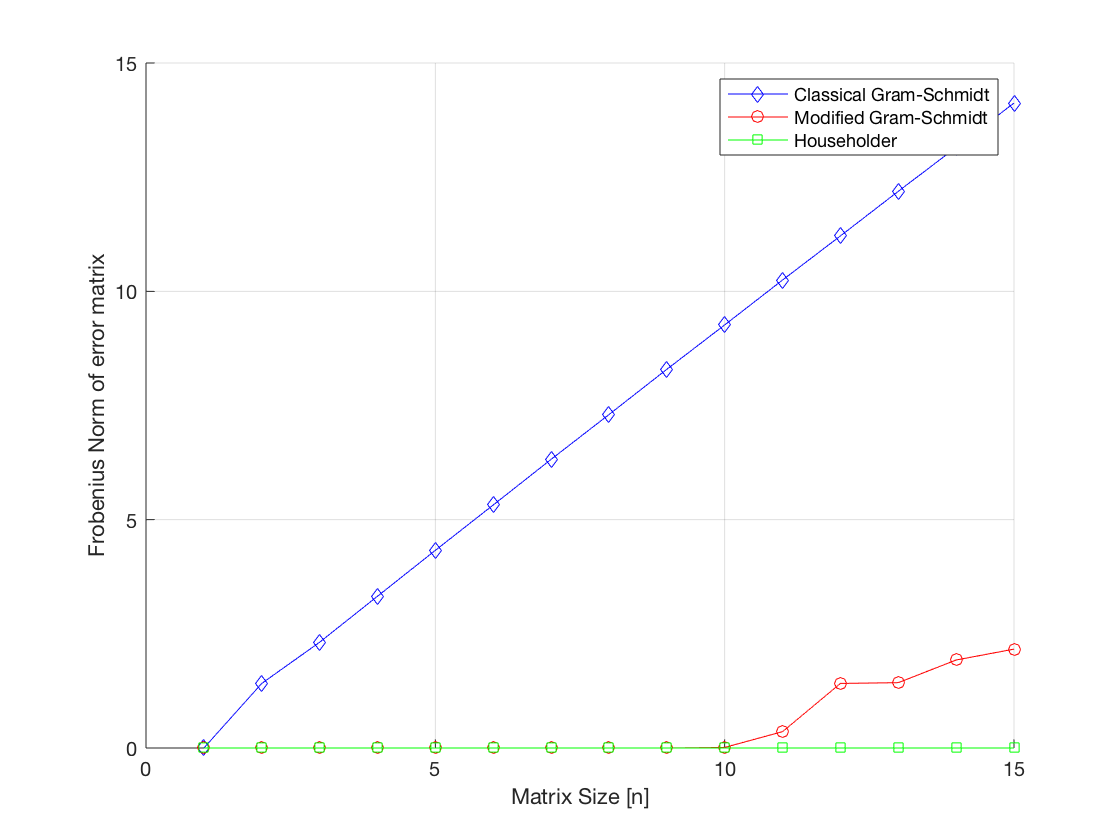



figure(4)
hold on 
grid on 
plot(err_gs,'b-d')
plot(err_mgs,'r-o')
plot(err_hh,'g-s')
ylabel('Frobenius Norm of error matrix');
xlabel('Matrix Size [n]')
legend('Classical Gram-Schmidt','Modified Gram-Schmidt','Householder');

e) Finally, now we have implemented various different versions of QR decompositon. Use above versions of the the QR transform and use this to fit the polynomial in question 3. We want to fit the polynomial of degree 14 through the data with 15 points. Clearly show all the plots (with legends) and comment on the results obtained.

% Implement Question 4 part e here.Use the  code privided in Question 3 part (d) for inspitration.

load('Polynomial_Fitting_Data.mat');

% set the degree
deg =  14;
% Define powers 

powers = 0:deg;
x = x_given(1:20:end);
y = y_given(1:20:end);

% get Polynomial Matrix 
Mp = PolynomialMatrix(x,deg);


   
   % MATLAB QR Decomposition
   [q_gs,r1] = gschmidt(Mp); %using algorithm classical Gram--Schmidt
   [q_mgs,r2] = mgschmidt(Mp); %using algorithm modified Gram-Schmidt

v =     0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000   -0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0         0         0         0         0         0         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0         0         0         0         0         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001         0         0         0         0         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0000    0.0000

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008         0         0         0         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008    0.0000    0.0000    0.0000    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008    0.0000

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048         0         0         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048    0.0000    0.0000    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0047

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291         0         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291    0.0000    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0047

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789    0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789    0.0000    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789    0.0001    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0047

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087    0.0000    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087    0.0000    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1086    0.0003    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0047

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087   -6.9152         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087   -6.9152    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087   -6.9152    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087   -6.9152    0.0000    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1087   -6.9151    0.0000    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0048   -0.0291   -0.1789   -1.1086   -6.9149    0.0006    0.0015
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0047

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0029   -0.0179   -0.1109   -0.6915   -4.3372         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0029   -0.0179   -0.1109   -0.6915   -4.3372    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0029   -0.0179   -0.1109   -0.6915   -4.3372    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0029   -0.0179   -0.1109   -0.6915   -4.3372    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0029   -0.0179   -0.1109   -0.6915   -4.3372    0.0000
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0029   -0.0179   -0.1109   -0.6915   -4.3372    0.0001
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005

v =     0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0018   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0024   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0018   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0111   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0111   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0024    0.0152   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0018    0.0114   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0002   -0.0692   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0036   -0.0691   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0024    0.0152    0.0967   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0018    0.0114    0.0730   -0.4337   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077    0.0493   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0019   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0036   -0.0218   -0.4337   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0024    0.0152    0.0967    0.6168   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0018    0.0114    0.0730    0.4667   -2.7332
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077    0.0493    0.3166   -2.7332
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256    0.1666   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0019    0.0165   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0036   -0.0218   -0.1336   -2.7332
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0024    0.0152    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0018    0.0114    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0036   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0024    0.0152    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0018    0.0114    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0036   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0004    0.0024    0.0152    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0018    0.0114    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0036   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0004    0.0024    0.0152    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0018    0.0114    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0036   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0004    0.0024    0.0152    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0003    0.0018    0.0114    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0036   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0004    0.0024    0.0152    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0003    0.0018    0.0114    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0006   -0.0036   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0004    0.0024    0.0152    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0003    0.0018    0.0114    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0012    0.0077    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0002    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0006   -0.0036   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003    0.0024    0.0152    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0018    0.0114    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0077    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0039    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0002    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002   -0.0006   -0.0036   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018    0.0152    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006    0.0114    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0077    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0039    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0013    0.0002    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014   -0.0036   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0120    0.0967    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0041    0.0730    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0020    0.0493    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0063    0.0256    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0013    0.0089    0.0019    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0096   -0.0218   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0120   -0.0794    0.6168    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0041   -0.0276    0.4667    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0020    0.0125    0.3166    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0063    0.0411    0.1666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0013    0.0089    0.0580    0.0165    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0096    0.0634   -0.1336   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0120   -0.0794   -0.5212    3.9430
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0041   -0.0276   -0.1835    2.9893
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0020    0.0125    0.0790    2.0355
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0063    0.0411    0.2666    1.0818
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0013    0.0089    0.0580    0.3791    0.1280
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0096    0.0634    0.4166   -0.8257
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0120   -0.0794   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0041   -0.0276   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0020    0.0125    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0063    0.0411    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0013    0.0089    0.0580    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0096    0.0634    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0120   -0.0794   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0041   -0.0276   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0020    0.0125    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0063    0.0411    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0013    0.0089    0.0580    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0096    0.0634    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0120   -0.0794   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0041   -0.0276   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0003    0.0020    0.0125    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0063    0.0411    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0002    0.0013    0.0089    0.0580    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0096    0.0634    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0018   -0.0120   -0.0794   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0041   -0.0276   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0003    0.0020    0.0125    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0010    0.0063    0.0411    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0002    0.0013    0.0089    0.0580    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0096    0.0634    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0003   -0.0018   -0.0120   -0.0794   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0041   -0.0276   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0003    0.0020    0.0125    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0010    0.0063    0.0411    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0002    0.0013    0.0089    0.0580    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0096    0.0634    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0018   -0.0120   -0.0794   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0006   -0.0041   -0.0276   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0003    0.0020    0.0125    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0010    0.0063    0.0411    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0002    0.0013    0.0089    0.0580    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0014    0.0096    0.0634    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0018   -0.0120   -0.0794   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0006   -0.0041   -0.0276   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0003    0.0020    0.0125    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0010    0.0063    0.0411    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0013    0.0089    0.0580    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0014    0.0096    0.0634    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009   -0.0120   -0.0794   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0041   -0.0276   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007    0.0020    0.0125    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008    0.0063    0.0411    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005    0.0089    0.0580    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0096    0.0634    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0065   -0.0794   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0015   -0.0276   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0051    0.0125    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0055    0.0411    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0036    0.0580    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0004    0.0634    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0065    0.0449   -0.5212   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0015   -0.0099   -0.1835   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0051   -0.0352    0.0790    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0055   -0.0381    0.2666    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0036   -0.0253    0.3791    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0004   -0.0035    0.4166    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0065    0.0449    0.3075   -3.4146
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0015   -0.0099   -0.0652   -1.2151
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0051   -0.0352   -0.2397    0.4993
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0055   -0.0381   -0.2615    1.7286
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0036   -0.0253   -0.1763    2.4728
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0004   -0.0035   -0.0295    2.7318
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0065    0.0449    0.3075    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0015   -0.0099   -0.0652   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0051   -0.0352   -0.2397   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0055   -0.0381   -0.2615   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0036   -0.0253   -0.1763   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0004   -0.0035   -0.0295   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0009    0.0065    0.0449    0.3075    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0015   -0.0099   -0.0652   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0051   -0.0352   -0.2397   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0055   -0.0381   -0.2615   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0036   -0.0253   -0.1763   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0004   -0.0035   -0.0295   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0009    0.0065    0.0449    0.3075    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0015   -0.0099   -0.0652   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0051   -0.0352   -0.2397   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0008   -0.0055   -0.0381   -0.2615   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0036   -0.0253   -0.1763   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0004   -0.0035   -0.0295   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0009    0.0065    0.0449    0.3075    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0002   -0.0015   -0.0099   -0.0652   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0007   -0.0051   -0.0352   -0.2397   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0008   -0.0055   -0.0381   -0.2615   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0036   -0.0253   -0.1763   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0004   -0.0035   -0.0295   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0001    0.0009    0.0065    0.0449    0.3075    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0002   -0.0015   -0.0099   -0.0652   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0007   -0.0051   -0.0352   -0.2397   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0001   -0.0008   -0.0055   -0.0381   -0.2615   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0005   -0.0036   -0.0253   -0.1763   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0035   -0.0295   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0009    0.0065    0.0449    0.3075    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0015   -0.0099   -0.0652   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0007   -0.0051   -0.0352   -0.2397   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0008   -0.0055   -0.0381   -0.2615   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0005   -0.0036   -0.0253   -0.1763   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0035   -0.0295   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003    0.0065    0.0449    0.3075    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003   -0.0015   -0.0099   -0.0652   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003   -0.0051   -0.0352   -0.2397   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0055   -0.0381   -0.2615   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0036   -0.0253   -0.1763   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0004   -0.0035   -0.0295   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0024    0.0449    0.3075    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0023   -0.0099   -0.0652   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0026   -0.0352   -0.2397   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008   -0.0381   -0.2615   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0013   -0.0253   -0.1763   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0026   -0.0035   -0.0295   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0024   -0.0182    0.3075    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0023    0.0172   -0.0652   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0026    0.0195   -0.2397   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0062   -0.2615   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0013   -0.0096   -0.1763   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0026   -0.0193   -0.0295   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0024   -0.0182   -0.1319    2.0879
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0023    0.0172    0.1231   -0.4290
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0026    0.0195    0.1417   -1.6171
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0062    0.0474   -1.7785
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0013   -0.0096   -0.0670   -1.2158
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0026   -0.0193   -0.1397   -0.2311
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0024   -0.0182   -0.1319   -0.9401
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0023    0.0172    0.1231    0.8687
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0026    0.0195    0.1417    1.0116
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0062    0.0474    0.3510
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0013   -0.0096   -0.0670   -0.4626
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0026   -0.0193   -0.1397   -0.9904
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0024   -0.0182   -0.1319   -0.9401
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0023    0.0172    0.1231    0.8687
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0026    0.0195    0.1417    1.0116
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0062    0.0474    0.3510
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0013   -0.0096   -0.0670   -0.4626
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0026   -0.0193   -0.1397   -0.9904
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0024   -0.0182   -0.1319   -0.9401
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0003    0.0023    0.0172    0.1231    0.8687
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0003    0.0026    0.0195    0.1417    1.0116
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0062    0.0474    0.3510
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0002   -0.0013   -0.0096   -0.0670   -0.4626
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0026   -0.0193   -0.1397   -0.9904
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0003   -0.0024   -0.0182   -0.1319   -0.9401
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0003    0.0023    0.0172    0.1231    0.8687
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0003    0.0026    0.0195    0.1417    1.0116
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0062    0.0474    0.3510
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0002   -0.0013   -0.0096   -0.0670   -0.4626
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0003   -0.0026   -0.0193   -0.1397   -0.9904
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0024   -0.0182   -0.1319   -0.9401
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0003    0.0023    0.0172    0.1231    0.8687
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0003    0.0026    0.0195    0.1417    1.0116
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0062    0.0474    0.3510
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0002   -0.0013   -0.0096   -0.0670   -0.4626
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0003   -0.0026   -0.0193   -0.1397   -0.9904
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0024   -0.0182   -0.1319   -0.9401
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0023    0.0172    0.1231    0.8687
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0026    0.0195    0.1417    1.0116
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0062    0.0474    0.3510
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0013   -0.0096   -0.0670   -0.4626
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001   -0.0026   -0.0193   -0.1397   -0.9904
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006   -0.0182   -0.1319   -0.9401
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0012    0.0172    0.1231    0.8687
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004    0.0195    0.1417    1.0116
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0007    0.0062    0.0474    0.3510
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010   -0.0096   -0.0670   -0.4626
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0005   -0.0193   -0.1397   -0.9904
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0053   -0.1319   -0.9401
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0012   -0.0096    0.1231    0.8687
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0034    0.1417    1.0116
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0007    0.0052    0.0474    0.3510
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0080   -0.0670   -0.4626
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0005    0.0041   -0.1397   -0.9904
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0006    0.0053    0.0413   -0.9401
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0012   -0.0096   -0.0748    0.8687
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0034   -0.0277    1.0116
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0007    0.0052    0.0398    0.3510
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0010    0.0080    0.0629   -0.4626
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0005    0.0041    0.0333   -0.9904
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0007    0.0064    0.0527    0.4134    3.1413
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0014   -0.0119   -0.0962   -0.7484   -5.6467
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0041   -0.0343   -0.2767   -2.1500
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0008    0.0065    0.0521    0.3983    2.9590
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0011    0.0098    0.0801    0.6291    4.7839
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0047    0.0406    0.3333    2.6257
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0001    0.0007    0.0064    0.0527    0.4134    3.1413
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0014   -0.0119   -0.0962   -0.7484   -5.6467
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0041   -0.0343   -0.2767   -2.1500
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0008    0.0065    0.0521    0.3983    2.9590
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0001    0.0011    0.0098    0.0801    0.6291    4.7839
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0047    0.0406    0.3333    2.6257
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0001    0.0007    0.0064    0.0527    0.4134    3.1413
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0014   -0.0119   -0.0962   -0.7484   -5.6467
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0041   -0.0343   -0.2767   -2.1500
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0001    0.0008    0.0065    0.0521    0.3983    2.9590
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0001    0.0011    0.0098    0.0801    0.6291    4.7839
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0047    0.0406    0.3333    2.6257
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0007    0.0064    0.0527    0.4134    3.1413
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0014   -0.0119   -0.0962   -0.7484   -5.6467
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0041   -0.0343   -0.2767   -2.1500
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0008    0.0065    0.0521    0.3983    2.9590
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0011    0.0098    0.0801    0.6291    4.7839
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0005    0.0047    0.0406    0.3333    2.6257
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0064    0.0527    0.4134    3.1413
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003   -0.0119   -0.0962   -0.7484   -5.6467
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0041   -0.0343   -0.2767   -2.1500
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003    0.0065    0.0521    0.3983    2.9590
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001    0.0098    0.0801    0.6291    4.7839
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0047    0.0406    0.3333    2.6257
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0012    0.0527    0.4134    3.1413
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0033   -0.0962   -0.7484   -5.6467
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0011   -0.0343   -0.2767   -2.1500
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0028    0.0521    0.3983    2.9590
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007    0.0801    0.6291    4.7839
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0020    0.0406    0.3333    2.6257
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0012   -0.0108    0.4134    3.1413
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0033    0.0308   -0.7484   -5.6467
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0011   -0.0099   -0.2767   -2.1500
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0028   -0.0261    0.3983    2.9590
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0074    0.6291    4.7839
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0020    0.0184    0.3333    2.6257
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0012   -0.0108   -0.0936    3.1413
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0033    0.0308    0.2657   -5.6467
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0011   -0.0099   -0.0817   -2.1500
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0028   -0.0261   -0.2258    2.9590
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0074   -0.0694    4.7839
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0020    0.0184    0.1560    2.6257
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0012   -0.0108   -0.0936   -0.7722
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0033    0.0308    0.2657    2.1802
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0011   -0.0099   -0.0817   -0.6449
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0028   -0.0261   -0.2258   -1.8576
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0074   -0.0694   -0.6073
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0020    0.0184    0.1560    1.2574
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0012   -0.0108   -0.0936   -0.7722
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0003    0.0033    0.0308    0.2657    2.1802
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0011   -0.0099   -0.0817   -0.6449
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0003   -0.0028   -0.0261   -0.2258   -1.8576
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0074   -0.0694   -0.6073
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0002    0.0020    0.0184    0.1560    1.2574
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0012   -0.0108   -0.0936   -0.7722
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0003    0.0033    0.0308    0.2657    2.1802
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0011   -0.0099   -0.0817   -0.6449
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0003   -0.0028   -0.0261   -0.2258   -1.8576
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0007   -0.0074   -0.0694   -0.6073
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0002    0.0020    0.0184    0.1560    1.2574
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0012   -0.0108   -0.0936   -0.7722
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0033    0.0308    0.2657    2.1802
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0011   -0.0099   -0.0817   -0.6449
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0028   -0.0261   -0.2258   -1.8576
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0007   -0.0074   -0.0694   -0.6073
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0020    0.0184    0.1560    1.2574
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001   -0.0108   -0.0936   -0.7722
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0006    0.0308    0.2657    2.1802
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0006   -0.0099   -0.0817   -0.6449
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003   -0.0261   -0.2258   -1.8576
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0074   -0.0694   -0.6073
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0005    0.0184    0.1560    1.2574
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0015   -0.0936   -0.7722
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0006   -0.0061    0.2657    2.1802
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0006    0.0062   -0.0817   -0.6449
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0032   -0.2258   -1.8576
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0046   -0.0694   -0.6073
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0005   -0.0052    0.1560    1.2574
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0149   -0.7722
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0006   -0.0061   -0.0598    2.1802
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0006    0.0062    0.0603   -0.6449
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0330   -1.8576
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0004   -0.0046   -0.0444   -0.6073
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0005   -0.0052   -0.0527    1.2574
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0001    0.0014    0.0150    0.1490    1.3666
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0004   -0.0055   -0.0607   -0.5984   -5.4641
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0005    0.0057    0.0620    0.6025    5.4365
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0002    0.0028    0.0324    0.3300    3.0971
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0003   -0.0043   -0.0459   -0.4438   -3.9761
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0046   -0.0522   -0.5271   -4.9043
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0001    0.0014    0.0150    0.1490    1.3666
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0004   -0.0055   -0.0607   -0.5984   -5.4641
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0005    0.0057    0.0620    0.6025    5.4365
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0002    0.0028    0.0324    0.3300    3.0971
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0003   -0.0043   -0.0459   -0.4438   -3.9761
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0003   -0.0046   -0.0522   -0.5271   -4.9043
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0014    0.0150    0.1490    1.3666
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0055   -0.0607   -0.5984   -5.4641
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001    0.0057    0.0620    0.6025    5.4365
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0028    0.0324    0.3300    3.0971
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0043   -0.0459   -0.4438   -3.9761
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0046   -0.0522   -0.5271   -4.9043
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001    0.0150    0.1490    1.3666
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0005   -0.0607   -0.5984   -5.4641
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0009    0.0620    0.6025    5.4365
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0324    0.3300    3.0971
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0007   -0.0459   -0.4438   -3.9761
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0522   -0.5271   -4.9043
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0014    0.1490    1.3666
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0005    0.0072   -0.5984   -5.4641
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0009   -0.0128    0.6025    5.4365
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0041    0.3300    3.0971
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0007    0.0101   -0.4438   -3.9761
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0027   -0.5271   -4.9043
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0014   -0.0160    1.3666
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0005    0.0072    0.0853   -5.4641
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0009   -0.0128   -0.1501    5.4365
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0041    0.0453    3.0971
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0007    0.0101    0.1202   -3.9761
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0027   -0.0283   -4.9043
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0001   -0.0014   -0.0160   -0.1682
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0005    0.0072    0.0853    0.8944
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0009   -0.0128   -0.1501   -1.5628
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0003    0.0041    0.0453    0.4492
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0007    0.0101    0.1202    1.2692
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0002   -0.0027   -0.0283   -0.2662
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0001   -0.0014   -0.0160   -0.1682
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0005    0.0072    0.0853    0.8944
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0009   -0.0128   -0.1501   -1.5628
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0003    0.0041    0.0453    0.4492
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0007    0.0101    0.1202    1.2692
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0002   -0.0027   -0.0283   -0.2662
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0014   -0.0160   -0.1682
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0072    0.0853    0.8944
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0001   -0.0128   -0.1501   -1.5628
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001    0.0041    0.0453    0.4492
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0101    0.1202    1.2692
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0001   -0.0027   -0.0283   -0.2662
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0001   -0.0160   -0.1682
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0005    0.0853    0.8944
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0001    0.0013   -0.1501   -1.5628
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0013    0.0453    0.4492
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0002    0.1202    1.2692
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0012   -0.0283   -0.2662
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0001    0.0011   -0.1682
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0005   -0.0074    0.8944
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0001    0.0013    0.0189   -1.5628
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0013   -0.0192    0.4492
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0002   -0.0034    1.2692
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0012    0.0186   -0.2662
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0007    0.0108    0.1365
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0002   -0.0049   -0.0735   -0.9254
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0006    0.0126    0.1893    2.3719
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0007   -0.0130   -0.1921   -2.3803
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001   -0.0020   -0.0338   -0.4738
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0006    0.0123    0.1856    2.3323
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0007    0.0108    0.1365
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0049   -0.0735   -0.9254
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0126    0.1893    2.3719
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0130   -0.1921   -2.3803
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0020   -0.0338   -0.4738
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0123    0.1856    2.3323
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0108    0.1365
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0002   -0.0735   -0.9254
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0006    0.1893    2.3719
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0010   -0.1921   -2.3803
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0007   -0.0338   -0.4738
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0003    0.1856    2.3323
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0004    0.1365
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0002    0.0035   -0.9254
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0006   -0.0121    2.3719
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0010    0.0207   -2.3803
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0007   -0.0142   -0.4738
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0003   -0.0080    2.3323
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0002   -0.0042   -0.0674
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0001    0.0001   -0.0001    0.0000    0.0016    0.0349    0.5654
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0002    0.0002   -0.0001   -0.0055   -0.1207   -1.9478
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001    0.0000    0.0001   -0.0002    0.0002    0.0096    0.2072    3.3271
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001    0.0001   -0.0000   -0.0002   -0.0067   -0.1417   -2.2354
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0000    0.0002   -0.0001   -0.0035   -0.0801   -1.3525
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0042   -0.0674
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0001    0.0001   -0.0001    0.0000   -0.0000    0.0349    0.5654
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0002    0.0002   -0.0001    0.0001   -0.1207   -1.9478
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001    0.0000    0.0001   -0.0002    0.0002   -0.0002    0.2072    3.3271
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001    0.0001   -0.0000   -0.0002    0.0003   -0.1417   -2.2354
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0000    0.0002   -0.0001   -0.0002   -0.0801   -1.3525
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0001   -0.0674
    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0001   -0.0001    0.0001   -0.0001    0.0000   -0.0000   -0.0008    0.5654
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0002    0.0002   -0.0001    0.0001    0.0034   -1.9478
    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001    0.0000    0.0001   -0.0002    0.0002   -0.0002   -0.0083    3.3271
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0001    0.0001   -0.0000   -0.0002    0.0003    0.0114   -2.2354
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0001   -0.0000    0.0002   -0.0001   -0.0002   -0.0068   -1.3525
    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000

v =     0.0000   -0.0000    0.0001   -0.0001    0.0002   -0.0002    0.0002   -0.0002    0.0002   -0.0002    0.0001   -0.0000    0.0000    0.0008    0.0178
    0.0000   -0.0000    0.0000   -0.0000   -0.0001    0.0002   -0.0005    0.0007   -0.0009    0.0009   -0.0007    0.0004   -0.0002   -0.0077   -0.1806
    0.0000   -0.0000    0.0000    0.0000   -0.0001    0.0002   -0.0001   -0.0003    0.0010   -0.0016    0.0018   -0.0014    0.0008    0.0338    0.7937
    0.0000   -0.0000   -0.0000    0.0001   -0.0001    0.0000    0.0003   -0.0006    0.0004    0.0006   -0.0019    0.0025   -0.0020   -0.0825   -1.9327
    0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0002    0.0003   -0.0001   -0.0007    0.0012   -0.0002   -0.0018    0.0027    0.1144    2.6645
    0.0000   -0.0000   -0.0000    0.0001    0.0000   -0.0002    0.0001    0.0005   -0.0007   -0.0004    0.0017   -0.0008   -0.0017   -0.0682   -1.5592
    0.0000   -0.0000   -0.0000    0.0000    0.0001   -0.0001   -0.0002    0.0005    0.0003

v =     0.0000   -0.0000    0.0001   -0.0001    0.0002   -0.0002    0.0002   -0.0002    0.0002   -0.0002    0.0001   -0.0000    0.0000   -0.0000    0.0178
    0.0000   -0.0000    0.0000   -0.0000   -0.0001    0.0002   -0.0005    0.0007   -0.0009    0.0009   -0.0007    0.0004   -0.0002    0.0001   -0.1806
    0.0000   -0.0000    0.0000    0.0000   -0.0001    0.0002   -0.0001   -0.0003    0.0010   -0.0016    0.0018   -0.0014    0.0008   -0.0003    0.7937
    0.0000   -0.0000   -0.0000    0.0001   -0.0001    0.0000    0.0003   -0.0006    0.0004    0.0006   -0.0019    0.0025   -0.0020    0.0009   -1.9327
    0.0000   -0.0000   -0.0000    0.0001   -0.0000   -0.0002    0.0003   -0.0001   -0.0007    0.0012   -0.0002   -0.0018    0.0027   -0.0019    2.6645
    0.0000   -0.0000   -0.0000    0.0001    0.0000   -0.0002    0.0001    0.0005   -0.0007   -0.0004    0.0017   -0.0008   -0.0017    0.0025   -1.5592
    0.0000   -0.0000   -0.0000    0.0000    0.0001   -0.0001   -0.0002    0.0005    0.0003

v =     0.0001   -0.0003    0.0007   -0.0011    0.0016   -0.0021    0.0025   -0.0025    0.0022   -0.0016    0.0010   -0.0005    0.0002   -0.0000   -0.0020
    0.0001   -0.0003    0.0004   -0.0002   -0.0007    0.0025   -0.0049    0.0075   -0.0090    0.0088   -0.0068    0.0041   -0.0018    0.0005    0.0239
    0.0001   -0.0002    0.0001    0.0004   -0.0014    0.0021   -0.0009   -0.0033    0.0099   -0.0160    0.0178   -0.0143    0.0080   -0.0028   -0.1295
    0.0001   -0.0002   -0.0001    0.0007   -0.0012    0.0001    0.0030   -0.0059    0.0037    0.0061   -0.0189    0.0248   -0.0196    0.0091    0.4140
    0.0001   -0.0001   -0.0002    0.0008   -0.0004   -0.0016    0.0034   -0.0006   -0.0074    0.0117   -0.0017   -0.0177    0.0273   -0.0187   -0.8526
    0.0001   -0.0001   -0.0003    0.0006    0.0004   -0.0021    0.0009    0.0048   -0.0066   -0.0044    0.0172   -0.0084   -0.0166    0.0249    1.1333
    0.0001   -0.0000   -0.0004    0.0003    0.0010   -0.0014   -0.0022    0.0048    0.0030

v =     1.0000   -3.2776    6.6502  -11.2097   16.4958  -21.4550   24.6579  -24.8673   21.7346  -16.1631    9.9579   -4.8846    1.7899   -0.4360    0.0552
    1.0000   -2.8094    3.8001   -1.6014   -7.0696   24.5200  -49.3159   74.6019  -90.0434   87.7424  -68.2826   41.1700  -18.1547    5.2295   -0.7393
    1.0000   -2.3411    1.3885    4.3114  -14.3206   20.9835   -9.4838  -32.5188   99.1194 -160.0321  178.4759 -143.0484   80.0341  -28.3272    4.8148
    1.0000   -1.8729   -0.5846    7.1446  -11.6015    0.9431   30.3482  -59.2989   37.4982   61.0999 -188.6526  248.4158 -195.8662   90.6467  -19.2567
    1.0000   -1.4047   -2.1193    7.5142   -4.1034  -16.0966   33.9693   -5.7386  -74.2799  117.0490  -17.3989 -176.5427  272.8319 -186.9590   52.9556
    1.0000   -0.9365   -3.2155    6.0360    4.1363  -21.4336    8.6217   47.8217  -65.6815  -44.4040  171.5820  -84.4335 -165.9493  249.2787 -105.9125
    1.0000   -0.4682   -3.8732    3.3259   10.2337  -14.4677  -21.5542   47.8217   29.8552

   [q_hh,r3] = householder(Mp);
   size(inv(q_gs*r1));

   size(y);
   A1 = (q_gs*r1)\y;

   A2 = (q_gs*r2)\y;

   A3 = (q_gs*r2)\y;

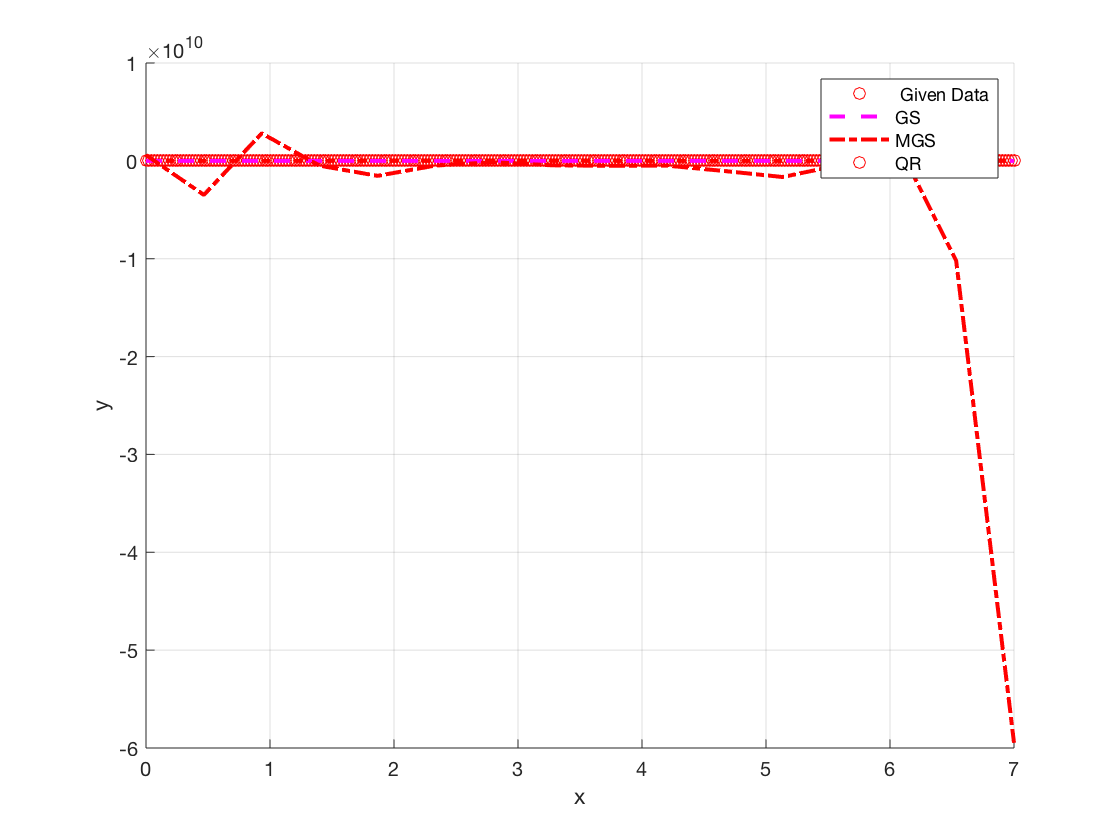


   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
   x_new = 0:7/15:7;
   x_new = x_new';
   
   fa = zeros(length(x_new),1);
   fb = zeros(length(x_new),1);
   fc = zeros(length(x_new),1);
   
  
   for I = 1:length(powers)
       fa = fa + A1(I)*x_new.^powers(I);   
       fb = fb + A2(I)*x_new.^powers(I);
       fc = fc + A3(I)*x_new.^powers(I);
   end
   %plots
   figure(1)
   hold on
   plot(x,y,'ro')
   plot(x_new,fa,'m--','Linewidth',2)
   plot(x_new,fb,'r-.','Linewidth',2)
   plot(x_new,fc,'r-.','Linewidth',2)
   xlabel('x')
   ylabel('y')
   legend(' Given Data','GS','MGS', 'QR')
   grid on

## Appendix 1

function A = Hilbert_matrix(size)

A = zeros(size,size);

for i=1:size
    for j=1:size
        A(i,j) = 1/(i+j-1);
    end 
end
end
% question 2 a 
function L = CholeskyDecomposition(M);
if(size(M,1) ~= size(M,2))
    disp('Matrix M must be square!');
end  
L = zeros(size(M));
m = size(M,1);
for i=1:m
  for j=1:m
    if i==j && j>=2
      for k=1:j-1
        M(j,j)=M(j,j)-L(j,k)*L(j,k);
        end
        L(i,j)=sqrt(M(j,j));
    elseif i==j
        L(i,j)=sqrt(M(j,j)); 
    elseif i>j && j>=2
        for k=1:j-1
            M(i,j)=M(i,j)-L(i,k)*L(j,k);
        end
        L(i,j)=M(i,j)/L(j,j);
    elseif i>j
      L(i,j)=1/L(j,j)*M(i,j);
    elseif i<j
      L(i,j)=0;
    end
  end
end

end

% question 2 b
function x = LeastSquareSolver_Cholesky(A,b)
M = A'*A;
L = CholeskyDecomposition(M);
y = forward_sub(L,b);   
x = backward_sub(L,b);
end

function y = forward_sub(L,b)
l = length(b);
y = zeros(l,1);
y(1,1) = b(1)./L(1,1);
for j = 2:l
    y(j,1) = (b(j)-sum(L(j,1:j-1)*y(1:j-1,1)))./L(j,j);
end
end

function x = backward_sub(L,b) 
l = length(b);
x = zeros(1,l);
x(1,l)=b(end)./L(l,l);
for i = l-1:-1:1
    temp = 1/L(i,i).*(b(i)-sum(L(i,i+1:end).*x(i+1:end)));
    x(1,i) = temp;
end
x=x'
end

%question 3a 
function M = PolynomialMatrix(x,n)
powers = 0:n;
for i = 1:length(powers)
    M(:,i) = x.^powers(i);
end
end

%question 4a 
function [Q,R] = gschmidt(A)
    [n,p] = size(A);
    Q = zeros(n,p);
    R = zeros(p,p);
    for i = 1:p
        Q(:,i) = A(:,i);
        if i ~= 1
            R(1:i-1,i) = Q(:,i-1)'*Q(:,i);
            Q(:,i) = Q(:,i) - Q(:,1:i-1)*R(1:i-1,i);
        end
        R(i,i) = norm(Q(:,i));
        Q(:,i) = Q(:,i)/R(i,i);
     end
end
 
 %question 4b
 function [Q,R] = mgschmidt(A)
   [n,p] = size(A);
    Q = zeros(n,p);
    R = zeros(p);
    v = zeros(p);
    for i = 1:n
        v(i,:) = A(i,:);
    end
        for i = 1:n
            R(i,i) = normest(v(:,i));
            Q(:,i) = v(:,i)/R(i,i);
       for j = (i+1):p
        R(i,j) = Q(:,i)'*v(:,j);
        v(:,j) = v(:,j)-R(i,j)*Q(:,i)
       end
        end
 end
% question 4c 
    function [Q,R] = householder(A)
    [n,p] = size(A);
    Q = eye(n,n);
    for j = 1:p
        z = A(j:end,j);
        v = [-sign(z(1))*normest(z)-z(1);-z(2:end)];
        Qt = eye(size(z,1),size(z,1))-(2/(v'*v))*(v*v');
        Qtt = eye(n,n);
        Qtt(j:end,j:end) = Qt;
        Q = Q*Qtt;
        A = Qtt*A;        
    end
    R = A; 
    end